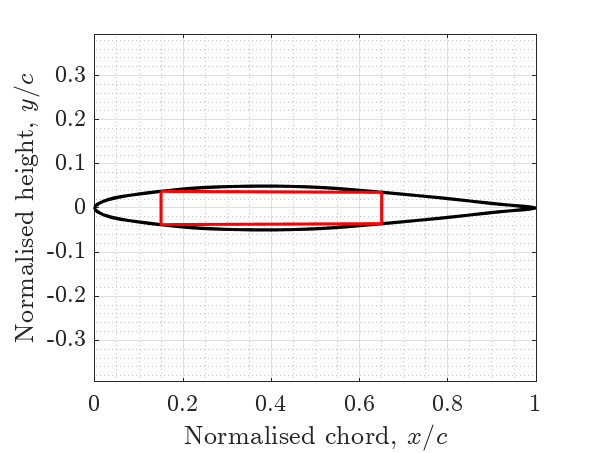

%HT Spars

clc
clear all
load('liftSurfGeom.mat')
load('MOHKAPROHANHTBMSFTORQUE.mat')
% This script is used to determine the web thickness of the wing spars

% N.B. Spars are placed at 20 % and 60 %

% Spar material: Al-7055, T76511
% E=73.5 GPa

E=7.35*10^10;
K=8.1;
% The first step is to discretise into stations:

disc=AAADISC;
spanwise_coordinates=disc;
no_stations=length(disc);
SF=AAASF;
BM=AAABM;
Torque=AAATORQUE;
% Now, find the shear flow due to shear force: q2

syms x;
span=4.4072;
root_chord=3.0280;
tip_chord=3.0280*0.4;
c = ((tip_chord-root_chord)/span)*x + root_chord;

for i=1:length(disc)
    c_r(i)=subs(c,x,disc(i));
end

coords=wingbox(HT);

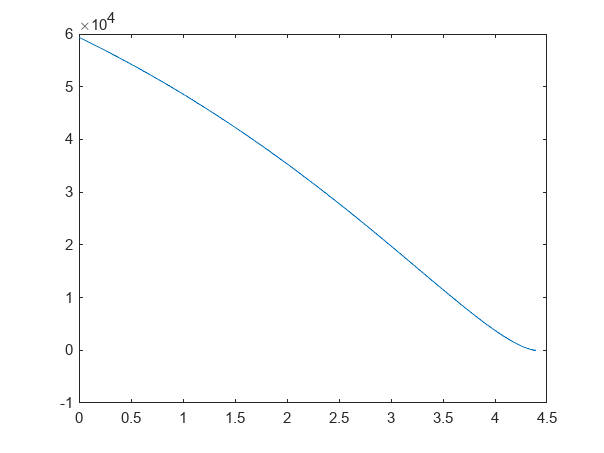

h_r =zeros(1,no_stations); % Depth of wing box along chord (m)

for j=1:no_stations
    h_r(j) = c_r(j)*((coords(1,2)-coords(2,2))+(coords(4,2)-coords(3,2)))/2;
end

q2 = (SF./(2.*h_r));

% Now, find the shear flow due to shear force: q02

q02 = -(Torque./(2.*h_r.*0.5.*double(c_r)));

% Now, find t_f and t_r:

t_f = ((1/(K*E))*(abs(q2+q02).*h_r)).^(1/3);
t_r = ((1/(K*E))*(abs(q2-q02).*h_r)).^(1/3);

plot(spanwise_coordinates,q2)

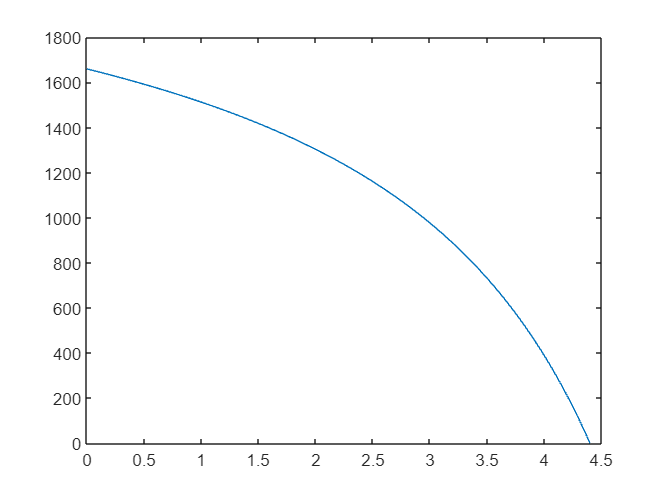


plot(spanwise_coordinates,q02)


tf_actual = t_f;
tr_actual = t_r;

tf_actual(t_f < 1e-3) = 1e-3;
tr_actual(t_r < 1e-3) = 1e-3;

figure()
p1 = plot(spanwise_coordinates,t_f, "--k", "LineWidth", 2, "DisplayName", "Front Spar Required")

p1 =   Line (Front Spar Required) with properties:

              Color: [0 0 0]
          LineStyle: '--'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0027 0.0027 0.0027 … ]

  Show al

hold on
p2 = plot(spanwise_coordinates,t_r, "--r", "LineWidth", 2, "DisplayName", "Rear Spar Required")

p2 =   Line (Rear Spar Required) with properties:

              Color: [1 0 0]
          LineStyle: '--'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 … ]

  Show all

p3 = plot(spanwise_coordinates,tf_actual, "-k", "LineWidth", 2, "DisplayName", "Front Spar Actual")

p3 =   Line (Front Spar Actual) with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0027 0.0027 0.0027 … ]

  Show all p

p4 = plot(spanwise_coordinates,tr_actual, "-r", "LineWidth", 2, "DisplayName", "Rear Spar Actual")

p4 =   Line (Rear Spar Actual) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0028 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 0.0027 … ]

  Show all pr

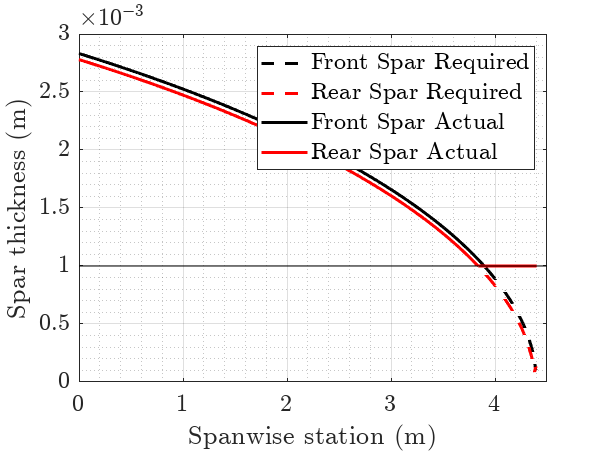


xlabel("Spanwise station (m)", "Interpreter","latex", "FontSize", 16)
ylabel("Spar thickness (m)", "Interpreter","latex", "FontSize", 16)
plot([-1000 10000], [1e-3 1e-3], "-k", LineWidth=0.5)
grid on
grid minor
set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")
% axis equal
legend([p1 p2 p3 p4], "Interpreter","latex", "FontSize", 16)
xlim([0 4.5])



figure()
hold on
p1 = plot(spanwise_coordinates,q02, "-k", "LineWidth", 2, "DisplayName", "$q_{0_2}$")

p1 =   Line ($q_{0_2}$) with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [1.6601e+03 1.6588e+03 1.6576e+03 1.6563e+03 1.6550e+03 1.6537e+03 1.6524e+03 1.6512e+03 1.6499e+03 1.6486e+03 1.6473e+03 1.6460e+03 1.6447e+03 1.6434e+03 1.6420e+03 1.6407e+03 1.6394e+03 1.6381e+03 1.6368e+03 1.6354e+03 … ]

  Show <a href="matlab:if exist('p1', 'var'), matlab.graphics.internal.getForDisplay('p1', p1, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p1'), end">all properties</a

hold on
p2 = plot(spanwise_coordinates,q2, "-r", "LineWidth", 2, "DisplayName", "$q_2$")

p2 =   Line ($q_2$) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [5.9363e+04 5.9266e+04 5.9168e+04 5.9082e+04 5.8985e+04 5.8887e+04 5.8789e+04 5.8690e+04 5.8592e+04 5.8493e+04 5.8394e+04 5.8294e+04 5.8195e+04 5.8106e+04 5.8006e+04 5.7906e+04 5.7806e+04 5.7705e+04 5.7604e+04 5.7503e+04 … ]

  Show all properties


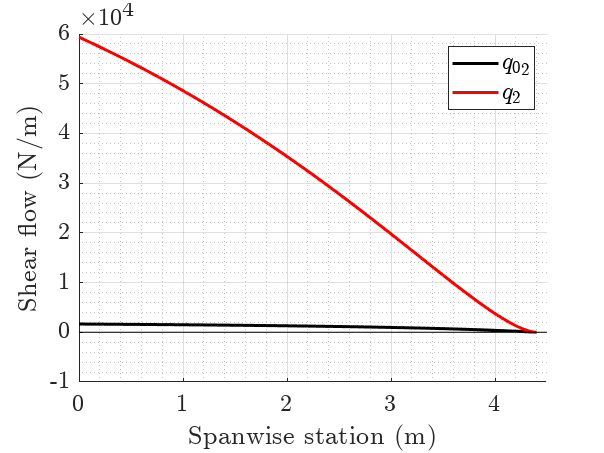



xlabel("Spanwise station (m)", "Interpreter","latex", "FontSize", 16)
ylabel("Shear flow (N/m)", "Interpreter","latex", "FontSize", 16)
plot([-1000 10000], [0 0], "-k", LineWidth=0.5)
grid on
grid minor
set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")
% axis equal

xlim([0 4.5])
legend([p1 p2], "Interpreter","latex", "FontSize", 16)
hold off

% Chord dist

dist=spanwise_coordinates

dist =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


span = span

span = 4.4072


c = double(c_r)

c =     3.0280    3.0239    3.0198    3.0156    3.0115    3.0074    3.0033    2.9991    2.9950    2.9909    2.9868    2.9827    2.9785    2.9744    2.9703    2.9662    2.9620    2.9579    2.9538    2.9497    2.9456    2.9414    2.9373    2.9332    2.9291    2.9249    2.9208    2.9167    2.9126    2.9085    2.9043    2.9002    2.8961    2.8920    2.8878    2.8837    2.8796    2.8755    2.8714    2.8672    2.8631    2.8590    2.8549    2.8507    2.8466    2.8425    2.8384    2.8342    2.8301    2.8260



BM=BM;

% Sigma, yield
sigma = 650*10^6;

coords=wingbox(HT);

D = h_r;
t1=[]


t1 =

     []



b=[]


b =

     []



A=[]


A =

     []



% I_xx min
I_min = BM.*D./(2.*sigma);

for i=1:length(t_f)
    [t1(i),b(i),A(i)] = GetShomeGoodShparsh(t_f(i), D(i), I_min(i))

end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.257282e-03    9.404e-06    2.112e-02
    1       6    1.499277e-03    3.364e-06    1.160e-03    1.216e-02
    2       9    1.122804e-03    1.536e-07    2.323e-03    7.600e-03
    3      12    1.133491e-03    1.294e-08    2.080e-03    1.508e-03
    4      18    1.131451e-03    2.476e-09    1.717e-03    1.897e-03
    5      26    1.129145e-03    6.099e-10    1.507e-03    1.276e-03
    6      32    1.126922e-03    8.086e-10    1.301e-03    1.483e-03
    7      38    1.124618e-03    1.038e-09    1.103e-03    1.718e-03
    8      44    1.122264e-03    1.274e-09    9.174e-04    1.983e-03
    9      48    1.119900e-03    1.493e-09    7.492e-04    2.278e-03
   10      52    1.117563e-03    1.669e-09    6.004e-04    2.603e-03
   11      56    1.115290e-03    1.781e-09    1.622e-05    2.955e-03
   12      66    1.113764e-03    4.499e-10    3

t1 = 0.0026

b = 0.0922

A = 0.0011

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.255976e-03    9.407e-06    2.116e-02
    1       6    1.497878e-03    3.386e-06    1.160e-03    1.216e-02
    2       9    1.117864e-03    1.557e-07    2.295e-03    7.672e-03
    3      12    1.128880e-03    1.249e-08    2.059e-03    1.501e-03
    4      18    1.126850e-03    2.411e-09    1.701e-03    1.883e-03
    5      26    1.124583e-03    5.930e-10    1.495e-03    1.266e-03
    6      32    1.122397e-03    7.862e-10    1.292e-03    1.471e-03
    7      38    1.120128e-03    1.009e-09    1.096e-03    1.703e-03
    8      44    1.117811e-03    1.240e-09    9.132e-04    1.965e-03
    9      48    1.115481e-03    1.455e-09    7.467e-04    2.258e-03
   10      52    1.113176e-03    1.628e-09    5.993e-04    2.580e-03
   11      56    1.110933e-03    1.739e-09    1.618e-05    2.928e-03
   12      66    1.109422e-03    4.447e-10    3

t1 =     0.0026    0.0026


b =     0.0922    0.0922


A =     0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.254671e-03    9.410e-06    2.120e-02
    1       6    1.496481e-03    3.409e-06    1.160e-03    1.216e-02
    2       9    1.112930e-03    1.579e-07    2.267e-03    7.744e-03
    3      12    1.124278e-03    1.203e-08    2.038e-03    1.494e-03
    4      18    1.122258e-03    2.348e-09    1.686e-03    1.870e-03
    5      26    1.120029e-03    5.766e-10    1.483e-03    1.256e-03
    6      32    1.117878e-03    7.646e-10    1.282e-03    1.459e-03
    7      38    1.115645e-03    9.818e-10    1.089e-03    1.689e-03
    8      44    1.113362e-03    1.207e-09    9.088e-04    1.949e-03
    9      48    1.111066e-03    1.418e-09    7.442e-04    2.238e-03
   10      52    1.108794e-03    1.588e-09    5.981e-04    2.556e-03
   11      56    1.106580e-03    1.699e-09    1.614e-05    2.901e-03
   12      66    1.105085e-03    4.394e-10    3

t1 =     0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928


A =     0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.253396e-03    9.413e-06    2.124e-02
    1       6    1.495120e-03    3.431e-06    1.160e-03    1.216e-02
    2       9    1.108029e-03    1.601e-07    2.238e-03    7.816e-03
    3      12    1.119711e-03    1.158e-08    2.017e-03    1.487e-03
    4      18    1.117700e-03    2.287e-09    1.670e-03    1.856e-03
    5      26    1.115509e-03    5.606e-10    1.470e-03    1.247e-03
    6      32    1.113393e-03    7.436e-10    1.273e-03    1.447e-03
    7      38    1.111195e-03    9.552e-10    1.083e-03    1.675e-03
    8      44    1.108947e-03    1.175e-09    9.043e-04    1.932e-03
    9      48    1.106685e-03    1.381e-09    7.415e-04    2.218e-03
   10      52    1.104444e-03    1.549e-09    5.969e-04    2.534e-03
   11      56    1.102259e-03    1.659e-09    1.610e-05    2.875e-03
   12      66    1.100779e-03    4.342e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928    0.0927


A =     0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.252092e-03    9.415e-06    2.128e-02
    1       6    1.493724e-03    3.452e-06    1.160e-03    1.216e-02
    2       9    1.103111e-03    1.622e-07    2.210e-03    7.887e-03
    3      12    1.115125e-03    1.114e-08    1.996e-03    1.481e-03
    4      18    1.113123e-03    2.227e-09    1.655e-03    1.843e-03
    5      26    1.110970e-03    5.453e-10    1.458e-03    1.237e-03
    6      32    1.108887e-03    7.233e-10    1.264e-03    1.436e-03
    7      38    1.106724e-03    9.295e-10    1.076e-03    1.661e-03
    8      44    1.104510e-03    1.144e-09    8.997e-04    1.916e-03
    9      50    1.102280e-03    1.347e-09    7.387e-04    2.200e-03
   10      54    1.100070e-03    1.513e-09    5.954e-04    2.512e-03
   11      58    1.097914e-03    1.622e-09    1.605e-05    2.851e-03
   12      68    1.096449e-03    4.291e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928    0.0927    0.0927


A =     0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.250789e-03    9.417e-06    2.132e-02
    1       6    1.492328e-03    3.474e-06    1.160e-03    1.216e-02
    2       9    1.098199e-03    1.644e-07    2.183e-03    7.958e-03
    3      12    1.110549e-03    1.070e-08    1.976e-03    1.474e-03
    4      18    1.108554e-03    2.170e-09    1.640e-03    1.830e-03
    5      26    1.106438e-03    5.305e-10    1.446e-03    1.228e-03
    6      32    1.104389e-03    7.038e-10    1.254e-03    1.424e-03
    7      38    1.102259e-03    9.047e-10    1.069e-03    1.648e-03
    8      44    1.100079e-03    1.115e-09    8.950e-04    1.900e-03
    9      50    1.097881e-03    1.313e-09    7.358e-04    2.181e-03
   10      54    1.095702e-03    1.476e-09    5.940e-04    2.491e-03
   11      58    1.093574e-03    1.585e-09    1.601e-05    2.826e-03
   12      68    1.092125e-03    4.239e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.249488e-03    9.419e-06    2.135e-02
    1       6    1.490933e-03    3.495e-06    1.161e-03    1.216e-02
    2       9    1.093295e-03    1.666e-07    2.155e-03    8.030e-03
    3      12    1.105980e-03    1.026e-08    1.955e-03    1.467e-03
    4      18    1.103993e-03    2.114e-09    1.624e-03    1.818e-03
    5      26    1.101912e-03    5.161e-10    1.433e-03    1.218e-03
    6      32    1.099896e-03    6.848e-10    1.245e-03    1.413e-03
    7      38    1.097800e-03    8.807e-10    1.062e-03    1.635e-03
    8      44    1.095653e-03    1.086e-09    8.903e-04    1.884e-03
    9      50    1.093488e-03    1.280e-09    7.328e-04    2.163e-03
   10      54    1.091339e-03    1.441e-09    5.924e-04    2.469e-03
   11      58    1.089239e-03    1.549e-09    1.597e-05    2.801e-03
   12      68    1.087804e-03    4.188e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.248187e-03    9.421e-06    2.139e-02
    1       6    1.489538e-03    3.516e-06    1.161e-03    1.216e-02
    2       9    1.088398e-03    1.688e-07    2.128e-03    8.101e-03
    3      12    1.101419e-03    9.830e-09    1.935e-03    1.460e-03
    4      18    1.099439e-03    2.061e-09    1.609e-03    1.805e-03
    5      26    1.097394e-03    5.022e-10    1.421e-03    1.209e-03
    6      32    1.095410e-03    6.666e-10    1.235e-03    1.402e-03
    7      38    1.093347e-03    8.575e-10    1.055e-03    1.622e-03
    8      44    1.091232e-03    1.058e-09    8.854e-04    1.869e-03
    9      50    1.089099e-03    1.248e-09    7.297e-04    2.145e-03
   10      54    1.086980e-03    1.406e-09    5.907e-04    2.448e-03
   11      58    1.084908e-03    1.514e-09    1.592e-05    2.777e-03
   12      68    1.083488e-03    4.137e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.246887e-03    9.423e-06    2.143e-02
    1       6    1.488144e-03    3.537e-06    1.161e-03    1.216e-02
    2       9    1.083507e-03    1.710e-07    2.101e-03    8.172e-03
    3      12    1.096867e-03    9.401e-09    1.915e-03    1.454e-03
    4      18    1.094893e-03    2.008e-09    1.594e-03    1.793e-03
    5      26    1.092883e-03    4.888e-10    1.409e-03    1.200e-03
    6      32    1.090931e-03    6.489e-10    1.226e-03    1.392e-03
    7      38    1.088900e-03    8.351e-10    1.048e-03    1.609e-03
    8      44    1.086817e-03    1.031e-09    8.804e-04    1.854e-03
    9      50    1.084715e-03    1.218e-09    7.265e-04    2.127e-03
   10      54    1.082626e-03    1.373e-09    5.889e-04    2.428e-03
   11      58    1.080581e-03    1.480e-09    1.588e-05    2.754e-03
   12      68    1.079177e-03    4.086e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.245588e-03    9.424e-06    2.147e-02
    1       6    1.486751e-03    3.558e-06    1.161e-03    1.216e-02
    2       9    1.078753e-03    1.720e-07    2.075e-03    8.241e-03
    3      12    1.092314e-03    9.064e-09    1.894e-03    1.448e-03
    4      18    1.090354e-03    1.959e-09    1.579e-03    1.782e-03
    5      26    1.088376e-03    4.765e-10    1.396e-03    1.192e-03
    6      32    1.086455e-03    6.326e-10    1.216e-03    1.382e-03
    7      38    1.084455e-03    8.145e-10    1.041e-03    1.598e-03
    8      44    1.082404e-03    1.006e-09    8.750e-04    1.841e-03
    9      50    1.080331e-03    1.189e-09    7.229e-04    2.111e-03
   10      54    1.078271e-03    1.343e-09    5.866e-04    2.410e-03
   11      58    1.076253e-03    1.448e-09    1.583e-05    2.733e-03
   12      68    1.074864e-03    4.035e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.244290e-03    9.425e-06    2.151e-02
    1       6    1.485358e-03    3.578e-06    1.161e-03    1.216e-02
    2       9    1.077320e-03    1.401e-07    2.078e-03    8.241e-03
    3      12    1.087530e-03    1.099e-08    1.871e-03    1.454e-03
    4      18    1.085785e-03    1.962e-09    1.559e-03    1.789e-03
    5      26    1.083816e-03    4.825e-10    1.378e-03    1.200e-03
    6      32    1.081904e-03    6.419e-10    1.198e-03    1.393e-03
    7      38    1.079913e-03    8.275e-10    1.024e-03    1.612e-03
    8      44    1.077872e-03    1.023e-09    8.598e-04    1.860e-03
    9      50    1.075810e-03    1.209e-09    7.089e-04    2.135e-03
   10      54    1.073760e-03    1.363e-09    5.740e-04    2.439e-03
   11      58    1.071755e-03    1.468e-09    1.575e-05    2.768e-03
   12      68    1.070382e-03    3.988e-10    2

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.242992e-03    9.426e-06    2.155e-02
    1       6    1.483966e-03    3.599e-06    1.161e-03    1.216e-02
    2       9    1.075888e-03    1.085e-07    2.081e-03    8.241e-03
    3      12    1.082754e-03    1.291e-08    1.848e-03    1.463e-03
    4      18    1.081216e-03    1.986e-09    1.539e-03    1.803e-03
    5      26    1.079248e-03    4.949e-10    1.358e-03    1.214e-03
    6      32    1.077338e-03    6.601e-10    1.179e-03    1.412e-03
    7      38    1.075349e-03    8.524e-10    1.005e-03    1.636e-03
    8      44    1.073310e-03    1.054e-09    8.417e-04    1.890e-03
    9      50    1.071252e-03    1.245e-09    6.919e-04    2.173e-03
   10      54    1.069208e-03    1.403e-09    5.583e-04    2.485e-03
   11      58    1.067210e-03    1.507e-09    1.564e-05    2.823e-03
   12      68    1.065853e-03    3.940e-10    2

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.241696e-03    9.427e-06    2.159e-02
    1       6    1.482574e-03    3.619e-06    1.161e-03    1.216e-02
    2       9    1.074456e-03    7.706e-08    2.085e-03    8.242e-03
    3      12    1.077985e-03    1.483e-08    1.825e-03    1.474e-03
    4      18    1.076649e-03    2.032e-09    1.517e-03    1.824e-03
    5      26    1.074673e-03    5.143e-10    1.336e-03    1.234e-03
    6      32    1.072758e-03    6.881e-10    1.157e-03    1.437e-03
    7      38    1.070764e-03    8.904e-10    9.838e-04    1.670e-03
    8      44    1.068719e-03    1.102e-09    8.208e-04    1.932e-03
    9      48    1.066658e-03    1.300e-09    6.720e-04    2.225e-03
   10      52    1.064614e-03    1.461e-09    5.397e-04    2.548e-03
   11      56    1.062619e-03    1.563e-09    1.552e-05    2.899e-03
   12      66    1.061278e-03    3.892e-10    2

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.240429e-03    9.428e-06    2.163e-02
    1       6    1.481220e-03    3.639e-06    1.161e-03    1.216e-02
    2       9    1.073063e-03    4.587e-08    2.088e-03    8.242e-03
    3      12    1.073260e-03    1.676e-08    1.802e-03    1.489e-03
    4      16    1.071012e-03    1.754e-08    1.248e-03    3.684e-03
    5      22    1.065985e-03    1.607e-08    8.334e-04    4.180e-03
    6      28    1.062025e-03    3.236e-09    6.351e-04    2.967e-03
    7      34    1.059381e-03    3.702e-09    1.569e-05    3.565e-03
    8      44    1.057467e-03    9.499e-10    3.801e-04    2.611e-03
    9      50    1.055883e-03    9.492e-10    2.973e-04    2.885e-03
   10      54    1.054384e-03    9.222e-10    2.278e-04    3.153e-03
   11      58    1.052986e-03    8.767e-10    1.705e-04    3.409e-03
   12      62    1.051699e-03    8.218e-10    1

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.239134e-03    9.428e-06    2.167e-02
    1       6    1.479829e-03    3.658e-06    1.161e-03    1.216e-02
    2       9    1.071633e-03    1.494e-08    2.092e-03    8.242e-03
    3      13    1.070538e-03    1.299e-09    1.796e-03    1.491e-03
    4      19    1.067606e-03    2.245e-09    1.477e-03    1.867e-03
    5      25    1.065614e-03    5.439e-10    1.297e-03    1.264e-03
    6      31    1.063701e-03    7.312e-10    1.118e-03    1.479e-03
    7      37    1.061708e-03    9.494e-10    9.461e-04    1.724e-03
    8      43    1.059668e-03    1.176e-09    7.848e-04    2.001e-03
    9      47    1.057612e-03    1.386e-09    6.381e-04    2.311e-03
   10      51    1.055578e-03    1.552e-09    1.577e-05    2.653e-03
   11      61    1.054196e-03    3.978e-10    2.940e-04    1.876e-03
   12      67    1.052958e-03    4.028e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.237841e-03    9.429e-06    2.171e-02
    1       6    1.478440e-03    3.677e-06    1.161e-03    1.216e-02
    2       9    1.070203e-03    1.575e-08    2.095e-03    8.243e-03
    3      13    1.066009e-03    1.450e-09    1.775e-03    1.507e-03
    4      19    1.063056e-03    2.357e-09    1.455e-03    1.902e-03
    5      25    1.061039e-03    5.779e-10    1.273e-03    1.295e-03
    6      31    1.059108e-03    7.802e-10    1.094e-03    1.519e-03
    7      37    1.057098e-03    1.016e-09    9.209e-04    1.776e-03
    8      43    1.055041e-03    1.259e-09    7.596e-04    2.068e-03
    9      47    1.052972e-03    1.481e-09    6.137e-04    2.394e-03
   10      51    1.050927e-03    1.652e-09    1.566e-05    2.754e-03
   11      61    1.049535e-03    4.208e-10    2.967e-04    1.950e-03
   12      67    1.048297e-03    4.241e-10    3

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.236548e-03    9.429e-06    2.175e-02
    1       6    1.477051e-03    3.697e-06    1.161e-03    1.216e-02
    2       9    1.068773e-03    4.621e-08    2.099e-03    8.243e-03
    3      12    1.059028e-03    2.255e-08    1.735e-03    1.547e-03
    4      16    1.057572e-03    2.064e-08    1.177e-03    3.922e-03
    5      22    1.052416e-03    1.694e-08    7.754e-04    4.334e-03
    6      28    1.048443e-03    3.348e-09    5.858e-04    3.082e-03
    7      34    1.045873e-03    3.784e-09    1.540e-05    3.709e-03
    8      44    1.044006e-03    9.560e-10    3.431e-04    2.713e-03
    9      50    1.042480e-03    9.463e-10    2.657e-04    2.995e-03
   10      54    1.041042e-03    9.110e-10    2.013e-04    3.268e-03
   11      58    1.039707e-03    8.594e-10    1.487e-04    3.523e-03
   12      62    1.038485e-03    8.010e-10    1

t1 =     0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024


b =     0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914


A =     0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.235256e-03    9.429e-06    2.179e-02
    1       6    1.475662e-03    3.716e-06    1.161e-03    1.216e-02
    2       9    1.067345e-03    7.644e-08    2.102e-03    8.243e-03
    3      12    1.054300e-03    2.448e-08    1.713e-03    1.572e-03
    4      16    1.053128e-03    2.200e-08    1.152e-03    4.018e-03
    5      22    1.047901e-03    1.727e-08    7.554e-04    4.392e-03
    6      28    1.043921e-03    3.386e-09    5.689e-04    3.124e-03
    7      34    1.041376e-03    3.809e-09    1.530e-05    3.761e-03
    8      44    1.039535e-03    9.357e-10    3.311e-04    2.730e-03
    9      50    1.038039e-03    9.232e-10    2.560e-04    3.010e-03
   10      54    1.036631e-03    8.863e-10    1.937e-04    3.280e-03
   11      58    1.035325e-03    8.344e-10    1.428e-04    3.531e-03
   12      62    1.034131e-03    7.769e-10    1

t1 = 1×18
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024


b = 1×18
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914


A = 1×18
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.233965e-03    9.428e-06    2.183e-02
    1       6    1.474275e-03    3.734e-06    1.161e-03    1.216e-02
    2       9    1.065917e-03    1.064e-07    2.105e-03    8.244e-03
    3      12    1.049580e-03    2.641e-08    1.691e-03    1.598e-03
    4      16    1.048701e-03    2.342e-08    1.128e-03    4.113e-03
    5      22    1.043396e-03    1.753e-08    7.363e-04    4.443e-03
    6      28    1.039418e-03    3.405e-09    5.530e-04    3.161e-03
    7      34    1.036902e-03    3.812e-09    1.520e-05    3.805e-03
    8      44    1.035117e-03    8.498e-10    3.219e-04    2.676e-03
    9      50    1.033682e-03    8.364e-10    2.503e-04    2.942e-03
   10      54    1.032330e-03    8.023e-10    1.906e-04    3.196e-03
   11      58    1.031075e-03    7.557e-10    1.417e-04    3.433e-03
   12      62    1.029924e-03    7.046e-10    1

t1 = 1×19
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024


b = 1×19
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913


A = 1×19
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.232675e-03    9.428e-06    2.187e-02
    1       6    1.472888e-03    3.753e-06    1.162e-03    1.216e-02
    2       9    1.064489e-03    1.362e-07    2.109e-03    8.244e-03
    3      12    1.044867e-03    2.835e-08    1.669e-03    1.627e-03
    4      16    1.044287e-03    2.476e-08    1.106e-03    4.202e-03
    5      22    1.038906e-03    1.761e-08    7.190e-04    4.479e-03
    6      30    1.035049e-03    2.744e-09    5.493e-04    2.965e-03
    7      36    1.032711e-03    3.036e-09    1.519e-05    3.528e-03
    8      46    1.031045e-03    7.596e-10    3.309e-04    2.554e-03
    9      52    1.029659e-03    7.506e-10    2.601e-04    2.802e-03
   10      58    1.028347e-03    7.243e-10    2.007e-04    3.043e-03
   11      64    1.027122e-03    6.861e-10    1.514e-04    3.271e-03
   12      70    1.025992e-03    6.427e-10    1

t1 = 1×20
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024


b = 1×20
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906


A = 1×20
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.231386e-03    9.427e-06    2.191e-02
    1       6    1.471501e-03    3.771e-06    1.162e-03    1.216e-02
    2       9    1.063062e-03    1.658e-07    2.112e-03    8.244e-03
    3      12    1.040163e-03    3.028e-08    1.647e-03    1.658e-03
    4      16    1.039879e-03    2.586e-08    1.085e-03    4.276e-03
    5      22    1.034438e-03    1.743e-08    7.046e-04    4.491e-03
    6      30    1.030636e-03    2.660e-09    5.389e-04    2.955e-03
    7      38    1.028712e-03    1.268e-09    4.308e-04    2.649e-03
    8      44    1.026987e-03    1.315e-09    3.372e-04    2.992e-03
    9      48    1.025343e-03    1.306e-09    2.529e-04    3.343e-03
   10      52    1.023804e-03    1.250e-09    1.844e-04    3.691e-03
   11      56    1.022387e-03    1.166e-09    1.300e-04    4.013e-03
   12      60    1.021108e-03    1.072e-09    8

t1 = 1×21
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


b = 1×21
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912


A = 1×21
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.230098e-03    9.427e-06    2.195e-02
    1       6    1.470115e-03    3.789e-06    1.162e-03    1.216e-02
    2       9    1.061636e-03    1.951e-07    2.116e-03    8.245e-03
    3      12    1.035467e-03    3.222e-08    1.626e-03    1.690e-03
    4      16    1.035466e-03    2.648e-08    1.067e-03    4.324e-03
    5      22    1.029999e-03    1.690e-08    6.942e-04    4.467e-03
    6      30    1.026280e-03    2.587e-09    1.551e-05    2.941e-03
    7      40    1.024262e-03    1.658e-09    4.160e-04    2.911e-03
    8      46    1.022413e-03    1.722e-09    3.159e-04    3.323e-03
    9      50    1.020661e-03    1.698e-09    2.290e-04    3.746e-03
   10      54    1.019036e-03    1.606e-09    1.601e-04    4.160e-03
   11      58    1.017561e-03    1.477e-09    1.070e-04    4.531e-03
   12      62    1.016253e-03    1.342e-09    6

t1 = 1×22
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023


b = 1×22
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911


A = 1×22
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.228811e-03    9.426e-06    2.199e-02
    1       6    1.468730e-03    3.807e-06    1.162e-03    1.216e-02
    2       9    1.060210e-03    2.242e-07    2.119e-03    8.245e-03
    3      12    1.030778e-03    3.415e-08    1.605e-03    1.724e-03
    4      16    1.031035e-03    2.640e-08    1.052e-03    4.335e-03
    5      22    1.025599e-03    1.598e-08    6.889e-04    4.399e-03
    6      30    1.021995e-03    2.528e-09    1.546e-05    2.923e-03
    7      40    1.020003e-03    1.631e-09    4.138e-04    2.896e-03
    8      46    1.018176e-03    1.695e-09    3.147e-04    3.307e-03
    9      50    1.016444e-03    1.673e-09    2.282e-04    3.729e-03
   10      54    1.014835e-03    1.583e-09    1.597e-04    4.143e-03
   11      58    1.013374e-03    1.455e-09    1.069e-04    4.514e-03
   12      62    1.012079e-03    1.322e-09    6

t1 = 1×23
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023


b = 1×23
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910


A = 1×23
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.227524e-03    9.424e-06    2.203e-02
    1       6    1.467346e-03    3.825e-06    1.162e-03    1.216e-02
    2       9    1.058785e-03    2.530e-07    2.123e-03    8.245e-03
    3      12    1.026098e-03    3.609e-08    1.583e-03    1.760e-03
    4      16    1.026501e-03    2.322e-08    1.055e-03    4.175e-03
    5      22    1.021367e-03    1.404e-08    7.025e-04    4.199e-03
    6      30    1.017957e-03    2.491e-09    1.544e-05    2.875e-03
    7      40    1.015934e-03    1.780e-09    4.210e-04    2.941e-03
    8      46    1.014058e-03    1.866e-09    3.186e-04    3.379e-03
    9      50    1.012279e-03    1.849e-09    2.288e-04    3.831e-03
   10      54    1.010628e-03    1.748e-09    1.582e-04    4.277e-03
   11      58    1.009132e-03    1.602e-09    1.042e-04    4.678e-03
   12      62    1.007811e-03    1.448e-09    6

t1 = 1×24
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023


b = 1×24
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911


A = 1×24
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.226267e-03    9.423e-06    2.208e-02
    1       6    1.465998e-03    3.842e-06    1.162e-03    1.216e-02
    2       9    1.057398e-03    2.816e-07    2.126e-03    8.246e-03
    3      12    1.021470e-03    3.802e-08    1.562e-03    1.797e-03
    4      16    1.022027e-03    1.969e-08    1.061e-03    3.974e-03
    5      22    1.017243e-03    1.217e-08    7.203e-04    3.983e-03
    6      30    1.014041e-03    2.333e-09    5.584e-04    2.772e-03
    7      38    1.012217e-03    1.153e-09    4.504e-04    2.496e-03
    8      44    1.010560e-03    1.215e-09    3.569e-04    2.825e-03
    9      48    1.008969e-03    1.225e-09    2.723e-04    3.167e-03
   10      52    1.007468e-03    1.187e-09    2.012e-04    3.513e-03
   11      56    1.006075e-03    1.114e-09    1.440e-04    3.844e-03
   12      60    1.004806e-03    1.026e-09    9

t1 = 1×25
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023


b = 1×25
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908


A = 1×25
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.224983e-03    9.421e-06    2.212e-02
    1       6    1.464614e-03    3.859e-06    1.162e-03    1.216e-02
    2       9    1.055974e-03    3.100e-07    2.130e-03    8.246e-03
    3      12    1.016807e-03    3.996e-08    1.542e-03    1.836e-03
    4      16    1.017555e-03    1.665e-08    1.067e-03    3.780e-03
    5      22    1.013090e-03    1.059e-08    7.372e-04    3.784e-03
    6      30    1.010101e-03    2.049e-09    5.785e-04    2.618e-03
    7      36    1.007998e-03    2.340e-09    1.512e-05    3.102e-03
    8      46    1.006507e-03    6.057e-10    3.111e-04    2.248e-03
    9      52    1.005227e-03    6.102e-10    2.986e-04    2.468e-03
   10      58    1.004002e-03    5.995e-10    2.365e-04    2.689e-03
   11      64    1.002842e-03    5.759e-10    1.840e-04    2.907e-03
   12      70    1.001755e-03    5.440e-10    1

t1 = 1×26
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×26
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902


A = 1×26
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.223699e-03    9.420e-06    2.216e-02
    1       6    1.463232e-03    3.876e-06    1.162e-03    1.216e-02
    2       9    1.054551e-03    3.382e-07    2.134e-03    8.246e-03
    3      12    1.012151e-03    4.190e-08    1.521e-03    1.876e-03
    4      16    1.013123e-03    1.406e-08    1.073e-03    3.594e-03
    5      22    1.008947e-03    9.262e-09    7.530e-04    3.602e-03
    6      30    1.006145e-03    1.806e-09    5.976e-04    2.477e-03
    7      36    1.004115e-03    2.080e-09    1.515e-05    2.926e-03
    8      46    1.002682e-03    5.452e-10    2.993e-04    2.118e-03
    9      52    1.001436e-03    5.539e-10    3.204e-04    2.324e-03
   10      58    1.000237e-03    5.490e-10    2.568e-04    2.532e-03
   11      64    9.990948e-04    5.317e-10    2.026e-04    2.740e-03
   12      70    9.980186e-04    5.055e-10    1

t1 = 1×27
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×27
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899


A = 1×27
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.222417e-03    9.418e-06    2.220e-02
    1       6    1.461850e-03    3.893e-06    1.162e-03    1.216e-02
    2       9    1.053128e-03    3.661e-07    2.137e-03    8.247e-03
    3      12    1.007504e-03    4.384e-08    1.501e-03    1.917e-03
    4      16    1.008725e-03    1.187e-08    1.077e-03    3.418e-03
    5      22    1.004808e-03    8.137e-09    7.675e-04    3.435e-03
    6      30    1.002174e-03    1.598e-09    6.154e-04    2.350e-03
    7      36    1.000214e-03    1.855e-09    1.516e-05    2.767e-03
    8      46    9.988351e-04    4.916e-10    2.880e-04    2.000e-03
    9      52    9.976219e-04    5.034e-10    3.399e-04    2.193e-03
   10      58    9.964497e-04    5.031e-10    2.768e-04    2.390e-03
   11      64    9.953278e-04    4.912e-10    2.211e-04    2.587e-03
   12      70    9.942644e-04    4.703e-10    1

t1 = 1×28
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×28
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900


A = 1×28
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.221135e-03    9.416e-06    2.224e-02
    1       6    1.460468e-03    3.910e-06    1.162e-03    1.216e-02
    2       9    1.051706e-03    3.938e-07    2.141e-03    8.247e-03
    3      12    1.002864e-03    4.577e-08    1.480e-03    1.959e-03
    4      16    1.004356e-03    1.003e-08    1.081e-03    3.252e-03
    5      22    1.000671e-03    7.183e-09    7.807e-04    3.282e-03
    6      30    9.981876e-04    1.419e-09    6.319e-04    2.234e-03
    7      36    9.962934e-04    1.659e-09    1.515e-05    2.623e-03
    8      46    9.949665e-04    4.442e-10    2.774e-04    1.894e-03
    9      52    9.937861e-04    4.581e-10    3.580e-04    2.075e-03
   10      58    9.926411e-04    4.614e-10    2.963e-04    2.260e-03
   11      64    9.915404e-04    4.541e-10    2.392e-04    2.448e-03
   12      70    9.904918e-04    4.379e-10    1

t1 = 1×29
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×29
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897


A = 1×29
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.219854e-03    9.414e-06    2.229e-02
    1       6    1.459088e-03    3.926e-06    1.162e-03    1.216e-02
    2       9    1.050285e-03    4.214e-07    2.144e-03    8.247e-03
    3      12    9.982329e-04    4.771e-08    1.460e-03    2.002e-03
    4      16    1.000011e-03    8.496e-09    1.084e-03    3.097e-03
    5      22    9.965337e-04    6.370e-09    7.926e-04    3.142e-03
    6      30    9.941850e-04    1.265e-09    6.471e-04    2.129e-03
    7      36    9.923545e-04    1.488e-09    1.513e-05    2.493e-03
    8      46    9.910767e-04    4.022e-10    2.673e-04    1.797e-03
    9      52    9.899287e-04    4.175e-10    3.753e-04    1.967e-03
   10      58    9.888111e-04    4.236e-10    3.152e-04    2.142e-03
   11      64    9.877324e-04    4.200e-10    2.570e-04    2.321e-03
   12      70    9.867003e-04    4.079e-10    2

t1 = 1×30
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×30
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×30
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.218575e-03    9.411e-06    2.233e-02
    1       6    1.457708e-03    3.942e-06    1.162e-03    1.216e-02
    2       9    1.048864e-03    4.486e-07    2.148e-03    8.248e-03
    3      12    9.936096e-04    4.965e-08    1.440e-03    2.047e-03
    4      16    9.956847e-04    7.211e-09    1.085e-03    2.952e-03
    5      22    9.923938e-04    5.675e-09    8.030e-04    3.014e-03
    6      30    9.901673e-04    1.132e-09    6.609e-04    2.033e-03
    7      36    9.883980e-04    1.339e-09    1.511e-05    2.375e-03
    8      46    9.871665e-04    3.649e-10    2.577e-04    1.709e-03
    9      52    9.860504e-04    3.811e-10    3.916e-04    1.869e-03
   10      58    9.849603e-04    3.893e-10    3.313e-04    2.035e-03
   11      64    9.839043e-04    3.887e-10    2.741e-04    2.204e-03
   12      70    9.828898e-04    3.802e-10    2

t1 = 1×31
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×31
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×31
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.217296e-03    9.409e-06    2.237e-02
    1       6    1.456328e-03    3.958e-06    1.163e-03    1.216e-02
    2       9    1.047444e-03    4.757e-07    2.152e-03    8.248e-03
    3      12    9.889943e-04    5.159e-08    1.420e-03    2.092e-03
    4      15    9.855290e-04    5.074e-08    1.055e-03    2.836e-03
    5      19    9.893713e-04    4.283e-08    6.154e-04    6.025e-03
    6      25    9.829775e-04    1.271e-08    1.471e-05    5.164e-03
    7      33    9.798406e-04    5.375e-09    2.537e-04    4.918e-03
    8      39    9.776046e-04    5.210e-09    1.513e-04    5.900e-03
    9      43    9.756045e-04    4.620e-09    8.106e-05    6.803e-03
   10      47    9.739218e-04    3.942e-09    3.952e-06    7.425e-03
   11      55    9.727168e-04    1.269e-09    2.915e-05    5.450e-03
   12      61    9.719237e-04    1.031e-09    1

t1 = 1×32
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×32
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×32
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.216018e-03    9.406e-06    2.241e-02
    1       6    1.454949e-03    3.974e-06    1.163e-03    1.216e-02
    2       9    1.046024e-03    5.026e-07    2.155e-03    8.248e-03
    3      12    9.843872e-04    5.353e-08    1.400e-03    2.138e-03
    4      15    9.818606e-04    4.538e-08    1.057e-03    2.708e-03
    5      19    9.849194e-04    3.805e-08    6.279e-04    5.766e-03
    6      25    9.789830e-04    1.211e-08    1.473e-05    5.016e-03
    7      33    9.758846e-04    5.970e-09    2.603e-04    5.006e-03
    8      39    9.735795e-04    5.845e-09    1.528e-04    6.064e-03
    9      43    9.715117e-04    5.175e-09    7.997e-05    7.050e-03
   10      47    9.697778e-04    4.382e-09    3.889e-06    7.732e-03
   11      55    9.685542e-04    1.200e-09    2.808e-05    5.385e-03
   12      61    9.677855e-04    9.744e-10    1

t1 = 1×33
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×33
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×33
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.214741e-03    9.403e-06    2.246e-02
    1       6    1.453571e-03    3.990e-06    1.163e-03    1.216e-02
    2       9    1.044605e-03    5.292e-07    2.159e-03    8.248e-03
    3      12    9.797881e-04    5.546e-08    1.381e-03    2.185e-03
    4      15    9.781255e-04    4.065e-08    1.059e-03    2.589e-03
    5      19    9.805190e-04    3.400e-08    6.389e-04    5.532e-03
    6      25    9.749739e-04    1.150e-08    1.474e-05    4.873e-03
    7      33    9.719229e-04    6.546e-09    2.665e-04    5.079e-03
    8      39    9.695579e-04    6.477e-09    1.542e-04    6.209e-03
    9      43    9.674287e-04    5.728e-09    7.898e-05    7.277e-03
   10      47    9.656476e-04    4.816e-09    3.828e-06    8.021e-03
   11      55    9.644041e-04    1.139e-09    2.711e-05    5.326e-03
   12      61    9.636578e-04    9.246e-10    1

t1 = 1×34
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×34
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×34
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.213493e-03    9.400e-06    2.250e-02
    1       6    1.452229e-03    4.005e-06    1.163e-03    1.216e-02
    2       9    1.043224e-03    5.554e-07    2.162e-03    8.249e-03
    3      12    9.752508e-04    5.739e-08    1.362e-03    2.232e-03
    4      15    9.743819e-04    3.650e-08    1.059e-03    2.480e-03
    5      19    9.762119e-04    3.056e-08    6.486e-04    5.320e-03
    6      25    9.710031e-04    1.090e-08    1.474e-05    4.738e-03
    7      33    9.680055e-04    7.088e-09    2.723e-04    5.139e-03
    8      39    9.655903e-04    7.089e-09    1.556e-04    6.336e-03
    9      43    9.634064e-04    6.267e-09    7.812e-05    7.484e-03
   10      47    9.615824e-04    5.234e-09    3.771e-06    8.287e-03
   11      55    9.603181e-04    1.086e-09    2.626e-05    5.274e-03
   12      61    9.595918e-04    8.813e-10    1

t1 = 1×35
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×35
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×35
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.212218e-03    9.397e-06    2.254e-02
    1       6    1.450852e-03    4.020e-06    1.163e-03    1.216e-02
    2       9    1.041807e-03    5.816e-07    2.166e-03    8.249e-03
    3      12    9.706688e-04    5.933e-08    1.342e-03    2.280e-03
    4      15    9.705388e-04    3.283e-08    1.058e-03    2.378e-03
    5      19    9.718858e-04    2.760e-08    6.570e-04    5.128e-03
    6      25    9.669715e-04    1.032e-08    1.473e-05    4.609e-03
    7      33    9.640318e-04    7.592e-09    2.777e-04    5.185e-03
    8      39    9.615754e-04    7.679e-09    1.570e-04    6.446e-03
    9      43    9.593432e-04    6.788e-09    7.738e-05    7.669e-03
   10      47    9.574801e-04    5.633e-09    3.718e-06    8.532e-03
   11      55    9.561946e-04    1.039e-09    2.552e-05    5.228e-03
   12      61    9.554863e-04    8.439e-10    1

t1 = 1×36
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×36
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×36
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.210944e-03    9.393e-06    2.258e-02
    1       6    1.449476e-03    4.035e-06    1.163e-03    1.216e-02
    2       9    1.040389e-03    6.076e-07    2.170e-03    8.249e-03
    3      12    9.660949e-04    6.126e-08    1.323e-03    2.329e-03
    4      15    9.666522e-04    2.957e-08    1.056e-03    2.283e-03
    5      19    9.675864e-04    2.504e-08    6.642e-04    4.952e-03
    6      25    9.629310e-04    9.760e-09    1.472e-05    4.486e-03
    7      33    9.600516e-04    8.048e-09    2.828e-04    5.220e-03
    8      37    9.575625e-04    8.193e-09    1.584e-04    6.528e-03
    9      41    9.552917e-04    7.249e-09    7.697e-05    7.819e-03
   10      45    9.533954e-04    5.980e-09    3.673e-06    8.739e-03
   11      53    9.520896e-04    1.004e-09    2.498e-05    5.197e-03
   12      59    9.513952e-04    8.164e-10    1

t1 = 1×37
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×37
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×37
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.209671e-03    9.390e-06    2.263e-02
    1       6    1.448101e-03    4.050e-06    1.163e-03    1.216e-02
    2       9    1.038973e-03    6.333e-07    2.173e-03    8.250e-03
    3      12    9.615292e-04    6.320e-08    1.305e-03    2.378e-03
    4      15    9.627281e-04    2.669e-08    1.053e-03    2.195e-03
    5      19    9.633087e-04    2.282e-08    6.702e-04    4.791e-03
    6      25    9.588830e-04    9.231e-09    1.470e-05    4.370e-03
    7      33    9.560651e-04    8.451e-09    2.876e-04    5.244e-03
    8      37    9.535517e-04    8.701e-09    1.597e-04    6.604e-03
    9      41    9.512456e-04    7.707e-09    7.653e-05    7.961e-03
   10      45    9.493181e-04    6.322e-09    3.628e-06    8.939e-03
   11      53    9.479921e-04    9.697e-10    2.445e-05    5.167e-03
   12      59    9.473114e-04    7.897e-10    1

t1 = 1×38
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×38
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×38
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.208399e-03    9.386e-06    2.267e-02
    1       6    1.446726e-03    4.065e-06    1.163e-03    1.216e-02
    2       9    1.037557e-03    6.589e-07    2.177e-03    8.250e-03
    3      12    9.569717e-04    6.513e-08    1.286e-03    2.428e-03
    4      15    9.587720e-04    2.413e-08    1.050e-03    2.114e-03
    5      19    9.590492e-04    2.088e-08    6.752e-04    4.644e-03
    6      25    9.548287e-04    8.731e-09    1.468e-05    4.261e-03
    7      33    9.520725e-04    8.800e-09    2.914e-04    5.258e-03
    8      37    9.495425e-04    9.161e-09    1.610e-04    6.665e-03
    9      41    9.472073e-04    8.127e-09    7.622e-05    8.083e-03
   10      45    9.452523e-04    6.632e-09    3.587e-06    9.116e-03
   11      53    9.439071e-04    9.406e-10    2.402e-05    5.144e-03
   12      59    9.432382e-04    7.677e-10    1

t1 = 1×39
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×39
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×39
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.207128e-03    9.382e-06    2.272e-02
    1       6    1.445351e-03    4.079e-06    1.163e-03    1.216e-02
    2       9    1.036142e-03    6.842e-07    2.181e-03    8.250e-03
    3      12    9.524223e-04    6.706e-08    1.267e-03    2.478e-03
    4      15    9.547887e-04    2.184e-08    1.045e-03    2.039e-03
    5      19    9.548051e-04    1.918e-08    6.792e-04    4.508e-03
    6      25    9.507694e-04    8.260e-09    1.465e-05    4.158e-03
    7      35    9.485831e-04    1.108e-09    3.507e-04    2.585e-03
    8      41    9.471600e-04    1.151e-09    2.869e-04    2.951e-03
    9      45    9.457970e-04    1.144e-09    2.132e-04    3.323e-03
   10      49    9.445142e-04    1.086e-09    1.533e-04    3.695e-03
   11      53    9.433298e-04    9.952e-10    1.061e-04    4.046e-03
   12      57    9.422583e-04    8.955e-10    6

t1 = 1×40
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×40
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×40
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.205858e-03    9.378e-06    2.276e-02
    1       6    1.443978e-03    4.093e-06    1.163e-03    1.216e-02
    2       9    1.034727e-03    7.093e-07    2.185e-03    8.251e-03
    3      12    9.478811e-04    6.900e-08    1.249e-03    2.528e-03
    4      15    9.507823e-04    1.980e-08    1.040e-03    1.969e-03
    5      19    9.505743e-04    1.768e-08    6.823e-04    4.383e-03
    6      25    9.467061e-04    7.817e-09    1.462e-05    4.060e-03
    7      35    9.445645e-04    1.120e-09    3.488e-04    2.572e-03
    8      41    9.431409e-04    1.171e-09    2.903e-04    2.942e-03
    9      45    9.417752e-04    1.169e-09    2.161e-04    3.321e-03
   10      49    9.404882e-04    1.112e-09    1.551e-04    3.701e-03
   11      53    9.392987e-04    1.020e-09    1.072e-04    4.062e-03
   12      57    9.382220e-04    9.158e-10    7

t1 = 1×41
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×41
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×41
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.204589e-03    9.374e-06    2.280e-02
    1       6    1.442605e-03    4.107e-06    1.163e-03    1.216e-02
    2       9    1.033313e-03    7.342e-07    2.188e-03    8.251e-03
    3      12    9.433482e-04    7.093e-08    1.231e-03    2.580e-03
    4      15    9.467566e-04    1.798e-08    1.034e-03    1.903e-03
    5      19    9.463552e-04    1.635e-08    6.845e-04    4.267e-03
    6      25    9.426397e-04    7.402e-09    1.459e-05    3.968e-03
    7      35    9.405477e-04    1.111e-09    3.448e-04    2.544e-03
    8      41    9.391323e-04    1.168e-09    2.941e-04    2.914e-03
    9      45    9.377721e-04    1.172e-09    2.198e-04    3.294e-03
   10      49    9.364878e-04    1.118e-09    1.580e-04    3.679e-03
   11      53    9.352989e-04    1.026e-09    1.093e-04    4.046e-03
   12      57    9.342209e-04    9.209e-10    7

t1 = 1×42
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×42
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×42
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.203320e-03    9.369e-06    2.285e-02
    1       6    1.441232e-03    4.121e-06    1.163e-03    1.216e-02
    2       9    1.031900e-03    7.589e-07    2.192e-03    8.251e-03
    3      12    9.388234e-04    7.286e-08    1.212e-03    2.631e-03
    4      15    9.427148e-04    1.634e-08    1.027e-03    1.843e-03
    5      19    9.421466e-04    1.516e-08    6.859e-04    4.160e-03
    6      25    9.385712e-04    7.013e-09    1.455e-05    3.881e-03
    7      35    9.365295e-04    1.093e-09    3.399e-04    2.511e-03
    8      41    9.351264e-04    1.155e-09    2.977e-04    2.879e-03
    9      45    9.337753e-04    1.164e-09    2.237e-04    3.259e-03
   10      49    9.324973e-04    1.115e-09    1.611e-04    3.645e-03
   11      53    9.313118e-04    1.025e-09    1.117e-04    4.016e-03
   12      57    9.302348e-04    9.194e-10    7

t1 = 1×43
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×43
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×43
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.202053e-03    9.365e-06    2.289e-02
    1       6    1.439861e-03    4.135e-06    1.164e-03    1.216e-02
    2       9    1.030487e-03    7.833e-07    2.196e-03    8.252e-03
    3      12    9.343068e-04    7.479e-08    1.194e-03    2.683e-03
    4      15    9.386597e-04    1.486e-08    1.020e-03    1.786e-03
    5      19    9.379475e-04    1.411e-08    6.866e-04    4.060e-03
    6      25    9.345013e-04    6.649e-09    1.452e-05    3.798e-03
    7      35    9.325104e-04    1.067e-09    3.342e-04    2.474e-03
    8      41    9.311229e-04    1.134e-09    3.013e-04    2.838e-03
    9      45    9.297844e-04    1.148e-09    2.276e-04    3.216e-03
   10      49    9.285157e-04    1.104e-09    1.644e-04    3.601e-03
   11      53    9.273362e-04    1.017e-09    1.144e-04    3.974e-03
   12      57    9.262622e-04    9.120e-10    7

t1 = 1×44
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×44
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×44
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.200787e-03    9.360e-06    2.294e-02
    1       6    1.438490e-03    4.148e-06    1.164e-03    1.216e-02
    2       9    1.029075e-03    8.076e-07    2.200e-03    8.252e-03
    3      12    9.297985e-04    7.671e-08    1.177e-03    2.735e-03
    4      15    9.345936e-04    1.353e-08    1.013e-03    1.733e-03
    5      19    9.337571e-04    1.316e-08    6.866e-04    3.967e-03
    6      25    9.304306e-04    6.308e-09    1.448e-05    3.720e-03
    7      35    9.284908e-04    1.035e-09    3.278e-04    2.434e-03
    8      41    9.271219e-04    1.105e-09    3.047e-04    2.793e-03
    9      45    9.257988e-04    1.124e-09    2.316e-04    3.167e-03
   10      49    9.245420e-04    1.085e-09    1.679e-04    3.550e-03
   11      53    9.233710e-04    1.002e-09    1.174e-04    3.923e-03
   12      57    9.223020e-04    8.995e-10    7

t1 = 1×45
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×45
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×45
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.199549e-03    9.355e-06    2.298e-02
    1       6    1.437154e-03    4.161e-06    1.164e-03    1.216e-02
    2       9    1.027701e-03    8.314e-07    2.203e-03    8.252e-03
    3      12    9.253617e-04    7.862e-08    1.159e-03    2.787e-03
    4      15    9.305787e-04    1.233e-08    1.005e-03    1.684e-03
    5      19    9.296356e-04    1.231e-08    6.860e-04    3.881e-03
    6      25    9.264195e-04    5.991e-09    1.444e-05    3.646e-03
    7      35    9.245303e-04    9.993e-10    3.210e-04    2.392e-03
    8      41    9.231823e-04    1.071e-09    3.080e-04    2.745e-03
    9      45    9.218769e-04    1.095e-09    2.356e-04    3.114e-03
   10      49    9.206343e-04    1.061e-09    1.715e-04    3.493e-03
   11      53    9.194737e-04    9.827e-10    1.205e-04    3.864e-03
   12      57    9.184114e-04    8.827e-10    8

t1 = 1×46
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×46
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×46
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.198285e-03    9.350e-06    2.303e-02
    1       6    1.435785e-03    4.174e-06    1.164e-03    1.216e-02
    2       9    1.026290e-03    8.552e-07    2.207e-03    8.253e-03
    3      12    9.208707e-04    8.055e-08    1.142e-03    2.840e-03
    4      15    9.264980e-04    1.123e-08    9.967e-04    1.638e-03
    5      19    9.254621e-04    1.154e-08    6.848e-04    3.800e-03
    6      25    9.223501e-04    5.692e-09    1.440e-05    3.576e-03
    7      35    9.205118e-04    9.594e-10    3.137e-04    2.347e-03
    8      41    9.191870e-04    1.033e-09    3.112e-04    2.693e-03
    9      45    9.179015e-04    1.060e-09    2.397e-04    3.055e-03
   10      49    9.166754e-04    1.032e-09    1.752e-04    3.429e-03
   11      53    9.155273e-04    9.585e-10    1.238e-04    3.797e-03
   12      57    9.144735e-04    8.622e-10    8

t1 = 1×47
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×47
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×47
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.197022e-03    9.344e-06    2.307e-02
    1       6    1.434415e-03    4.187e-06    1.164e-03    1.216e-02
    2       9    1.024880e-03    8.788e-07    2.211e-03    8.253e-03
    3      12    9.163880e-04    8.247e-08    1.124e-03    2.892e-03
    4      15    9.224122e-04    1.023e-08    9.881e-04    1.595e-03
    5      19    9.212962e-04    1.084e-08    6.831e-04    3.724e-03
    6      25    9.182817e-04    5.412e-09    1.436e-05    3.509e-03
    7      35    9.164940e-04    9.170e-10    3.061e-04    2.301e-03
    8      41    9.151941e-04    9.908e-10    3.142e-04    2.639e-03
    9      45    9.139305e-04    1.021e-09    2.438e-04    2.994e-03
   10      49    9.127226e-04    9.979e-10    1.791e-04    3.361e-03
   11      53    9.115888e-04    9.306e-10    1.273e-04    3.725e-03
   12      57    9.105449e-04    8.386e-10    8

t1 = 1×48
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×48
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×48
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.195759e-03    9.339e-06    2.312e-02
    1       6    1.433047e-03    4.199e-06    1.164e-03    1.216e-02
    2       9    1.023470e-03    9.022e-07    2.215e-03    8.253e-03
    3      12    9.119135e-04    8.439e-08    1.107e-03    2.946e-03
    4      15    9.183226e-04    9.315e-09    9.792e-04    1.555e-03
    5      21    9.177117e-04    1.236e-09    8.144e-04    1.827e-03
    6      29    9.166136e-04    2.590e-10    7.228e-04    1.170e-03
    7      35    9.155880e-04    3.174e-10    6.337e-04    1.328e-03
    8      43    9.145274e-04    3.906e-10    5.476e-04    1.517e-03
    9      49    9.134513e-04    4.507e-10    4.667e-04    1.712e-03
   10      53    9.123736e-04    5.009e-10    3.925e-04    1.922e-03
   11      57    9.113070e-04    5.358e-10    3.256e-04    2.148e-03
   12      61    9.102641e-04    5.517e-10    2

t1 = 1×49
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×49
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×49
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.194498e-03    9.333e-06    2.316e-02
    1       6    1.431679e-03    4.212e-06    1.164e-03    1.216e-02
    2       9    1.022061e-03    9.254e-07    2.219e-03    8.254e-03
    3      12    9.074474e-04    8.631e-08    1.090e-03    2.999e-03
    4      15    9.142307e-04    8.480e-09    9.700e-04    1.517e-03
    5      21    9.135731e-04    1.168e-09    8.089e-04    1.793e-03
    6      29    9.125077e-04    2.436e-10    7.196e-04    1.146e-03
    7      35    9.115095e-04    2.986e-10    1.415e-05    1.299e-03
    8      47    9.108327e-04    8.667e-11    1.418e-04    9.159e-04
    9      53    9.101719e-04    9.517e-11    2.943e-04    9.880e-04
   10      59    9.095072e-04    1.031e-10    4.584e-04    1.064e-03
   11      65    9.088417e-04    1.101e-10    4.293e-04    1.143e-03
   12      71    9.081786e-04    1.159e-10    3

t1 = 1×50
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×50
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×50
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.193238e-03    9.328e-06    2.321e-02
    1       6    1.430312e-03    4.224e-06    1.164e-03    1.216e-02
    2       9    1.020653e-03    9.484e-07    2.222e-03    8.254e-03
    3      12    9.029896e-04    8.822e-08    1.073e-03    3.052e-03
    4      15    9.101375e-04    7.713e-09    9.606e-04    1.481e-03
    5      21    9.094387e-04    1.105e-09    8.032e-04    1.762e-03
    6      29    9.084043e-04    2.297e-10    7.159e-04    1.124e-03
    7      35    9.074325e-04    2.816e-10    1.410e-05    1.273e-03
    8      47    9.067739e-04    8.180e-11    1.379e-04    8.966e-04
    9      53    9.061299e-04    8.989e-11    2.861e-04    9.666e-04
   10      59    9.054816e-04    9.754e-11    4.455e-04    1.040e-03
   11      65    9.048320e-04    1.043e-10    4.311e-04    1.117e-03
   12      71    9.041843e-04    1.099e-10    3

t1 = 1×51
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×51
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×51
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.191979e-03    9.322e-06    2.325e-02
    1       6    1.428945e-03    4.236e-06    1.164e-03    1.216e-02
    2       9    1.019245e-03    9.712e-07    2.226e-03    8.254e-03
    3      12    8.985401e-04    9.014e-08    1.056e-03    3.106e-03
    4      15    9.060440e-04    7.007e-09    9.510e-04    1.448e-03
    5      21    9.053088e-04    1.048e-09    7.971e-04    1.732e-03
    6      29    9.043039e-04    2.170e-10    7.118e-04    1.103e-03
    7      35    9.033573e-04    2.661e-10    1.405e-05    1.248e-03
    8      47    9.027162e-04    7.734e-11    1.341e-04    8.785e-04
    9      53    9.020883e-04    8.506e-11    2.782e-04    9.466e-04
   10      59    9.014559e-04    9.239e-11    4.331e-04    1.018e-03
   11      65    9.008217e-04    9.894e-11    4.324e-04    1.093e-03
   12      71    9.001888e-04    1.044e-10    3

t1 = 1×52
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×52
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×52
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.190720e-03    9.316e-06    2.330e-02
    1       6    1.427580e-03    4.248e-06    1.164e-03    1.216e-02
    2       9    1.017838e-03    9.938e-07    2.230e-03    8.255e-03
    3      12    8.940989e-04    9.205e-08    1.040e-03    3.160e-03
    4      15    9.019512e-04    6.356e-09    9.412e-04    1.416e-03
    5      21    9.011837e-04    9.960e-10    7.907e-04    1.704e-03
    6      29    9.002070e-04    2.054e-10    7.074e-04    1.083e-03
    7      35    8.992846e-04    2.518e-10    1.400e-05    1.225e-03
    8      47    8.986602e-04    7.325e-11    1.305e-04    8.615e-04
    9      53    8.980479e-04    8.063e-11    2.706e-04    9.279e-04
   10      59    8.974307e-04    8.766e-11    4.212e-04    9.976e-04
   11      65    8.968114e-04    9.399e-11    4.333e-04    1.071e-03
   12      71    8.961929e-04    9.936e-11    3

t1 = 1×53
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×53
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×53
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.189463e-03    9.310e-06    2.334e-02
    1       6    1.426214e-03    4.260e-06    1.164e-03    1.216e-02
    2       9    1.016432e-03    1.016e-06    2.234e-03    8.255e-03
    3      12    8.896661e-04    9.396e-08    1.023e-03    3.214e-03
    4      15    8.978598e-04    5.754e-09    9.312e-04    1.387e-03
    5      21    8.970638e-04    9.477e-10    7.841e-04    1.678e-03
    6      27    8.954532e-04    1.567e-09    1.394e-05    2.133e-03
    7      37    8.941982e-04    5.526e-10    2.556e-04    1.674e-03
    8      43    8.930375e-04    6.611e-10    4.466e-04    1.932e-03
    9      47    8.918701e-04    7.548e-10    3.653e-04    2.216e-03
   10      51    8.907142e-04    8.178e-10    2.932e-04    2.525e-03
   11      55    8.895877e-04    8.401e-10    2.300e-04    2.853e-03
   12      59    8.885076e-04    8.194e-10    1

t1 = 1×54
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×54
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×54
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.188207e-03    9.303e-06    2.339e-02
    1       6    1.424850e-03    4.271e-06    1.164e-03    1.216e-02
    2       9    1.015026e-03    1.038e-06    2.238e-03    8.255e-03
    3      12    8.852416e-04    9.587e-08    1.007e-03    3.268e-03
    4      15    8.937705e-04    5.197e-09    9.211e-04    1.359e-03
    5      21    8.929492e-04    9.032e-10    7.772e-04    1.653e-03
    6      27    8.913770e-04    1.488e-09    1.390e-05    2.099e-03
    7      37    8.901550e-04    5.251e-10    2.488e-04    1.644e-03
    8      43    8.890213e-04    6.289e-10    4.464e-04    1.897e-03
    9      47    8.878798e-04    7.196e-10    3.662e-04    2.174e-03
   10      51    8.867480e-04    7.818e-10    2.949e-04    2.475e-03
   11      55    8.856432e-04    8.058e-10    2.330e-04    2.796e-03
   12      59    8.845821e-04    7.889e-10    1

t1 = 1×55
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×55
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×55
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.186979e-03    9.296e-06    2.344e-02
    1       6    1.423521e-03    4.282e-06    1.165e-03    1.216e-02
    2       9    1.013657e-03    1.060e-06    2.242e-03    8.256e-03
    3      12    8.808973e-04    9.776e-08    9.912e-04    3.322e-03
    4      15    8.897521e-04    4.684e-09    9.111e-04    1.333e-03
    5      21    8.889087e-04    8.625e-10    7.702e-04    1.630e-03
    6      27    8.873729e-04    1.416e-09    1.386e-05    2.066e-03
    7      37    8.861822e-04    4.999e-10    2.423e-04    1.617e-03
    8      43    8.850743e-04    5.996e-10    4.459e-04    1.863e-03
    9      47    8.839576e-04    6.873e-10    3.668e-04    2.135e-03
   10      51    8.828490e-04    7.487e-10    2.963e-04    2.429e-03
   11      55    8.817652e-04    7.741e-10    2.351e-04    2.743e-03
   12      59    8.807225e-04    7.604e-10    1

t1 = 1×56
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×56
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×56
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.185725e-03    9.290e-06    2.348e-02
    1       6    1.422157e-03    4.293e-06    1.165e-03    1.216e-02
    2       9    1.012253e-03    1.082e-06    2.246e-03    8.256e-03
    3      12    8.764904e-04    9.966e-08    9.753e-04    3.376e-03
    4      15    8.856696e-04    4.202e-09    9.007e-04    1.308e-03
    5      21    8.848063e-04    8.244e-10    7.629e-04    1.608e-03
    6      27    8.833063e-04    1.349e-09    1.381e-05    2.035e-03
    7      37    8.821460e-04    4.765e-10    2.359e-04    1.591e-03
    8      43    8.810632e-04    5.721e-10    4.449e-04    1.832e-03
    9      47    8.799708e-04    6.570e-10    3.670e-04    2.097e-03
   10      51    8.788851e-04    7.174e-10    2.974e-04    2.385e-03
   11      55    8.778222e-04    7.439e-10    2.367e-04    2.693e-03
   12      59    8.767978e-04    7.331e-10    1

t1 = 1×57
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×57
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×57
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.184471e-03    9.283e-06    2.353e-02
    1       6    1.420795e-03    4.304e-06    1.165e-03    1.216e-02
    2       9    1.010849e-03    1.103e-06    2.250e-03    8.256e-03
    3      12    8.720918e-04    1.016e-07    9.594e-04    3.430e-03
    4      15    8.815909e-04    3.753e-09    8.904e-04    1.284e-03
    5      21    8.807101e-04    7.890e-10    7.554e-04    1.587e-03
    6      27    8.792446e-04    1.287e-09    1.377e-05    2.006e-03
    7      37    8.781133e-04    4.548e-10    2.297e-04    1.566e-03
    8      43    8.770549e-04    5.466e-10    4.437e-04    1.802e-03
    9      47    8.759861e-04    6.288e-10    3.669e-04    2.062e-03
   10      51    8.749226e-04    6.881e-10    2.981e-04    2.344e-03
   11      55    8.738801e-04    7.156e-10    2.380e-04    2.646e-03
   12      59    8.728739e-04    7.073e-10    1

t1 = 1×58
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×58
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×58
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.183219e-03    9.276e-06    2.358e-02
    1       6    1.419433e-03    4.315e-06    1.165e-03    1.216e-02
    2       9    1.009446e-03    1.125e-06    2.254e-03    8.257e-03
    3      12    8.677017e-04    1.035e-07    9.438e-04    3.485e-03
    4      15    8.775164e-04    3.332e-09    8.799e-04    1.262e-03
    5      21    8.766200e-04    7.562e-10    7.478e-04    1.567e-03
    6      27    8.751879e-04    1.230e-09    1.373e-05    1.978e-03
    7      37    8.740845e-04    4.347e-10    2.237e-04    1.543e-03
    8      43    8.730498e-04    5.230e-10    4.421e-04    1.775e-03
    9      47    8.720038e-04    6.025e-10    3.665e-04    2.029e-03
   10      51    8.709620e-04    6.608e-10    2.986e-04    2.306e-03
   11      55    8.699394e-04    6.889e-10    2.390e-04    2.601e-03
   12      59    8.689510e-04    6.829e-10    1

t1 = 1×59
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×59
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×59
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.181968e-03    9.269e-06    2.362e-02
    1       6    1.418072e-03    4.325e-06    1.165e-03    1.216e-02
    2       9    1.008043e-03    1.146e-06    2.257e-03    8.257e-03
    3      12    8.633200e-04    1.054e-07    9.282e-04    3.539e-03
    4      15    8.734466e-04    2.939e-09    8.694e-04    1.240e-03
    5      21    8.725364e-04    7.257e-10    7.400e-04    1.548e-03
    6      27    8.711366e-04    1.176e-09    1.369e-05    1.952e-03
    7      37    8.700600e-04    4.160e-10    2.180e-04    1.521e-03
    8      43    8.690481e-04    5.010e-10    4.403e-04    1.748e-03
    9      47    8.680243e-04    5.780e-10    3.658e-04    1.998e-03
   10      51    8.670035e-04    6.352e-10    2.987e-04    2.270e-03
   11      55    8.660005e-04    6.638e-10    2.398e-04    2.560e-03
   12      59    8.650296e-04    6.598e-10    1

t1 = 1×60
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×60
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×60
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.180718e-03    9.262e-06    2.367e-02
    1       6    1.416711e-03    4.336e-06    1.165e-03    1.216e-02
    2       9    1.006641e-03    1.167e-06    2.261e-03    8.257e-03
    3      12    8.589467e-04    1.072e-07    9.129e-04    3.594e-03
    4      15    8.693818e-04    2.570e-09    8.588e-04    1.220e-03
    5      21    8.684594e-04    6.972e-10    7.321e-04    1.530e-03
    6      27    8.670908e-04    1.127e-09    1.365e-05    1.927e-03
    7      37    8.660400e-04    3.987e-10    2.123e-04    1.500e-03
    8      43    8.650501e-04    4.806e-10    4.382e-04    1.724e-03
    9      47    8.640479e-04    5.552e-10    3.648e-04    1.969e-03
   10      51    8.630477e-04    6.112e-10    2.986e-04    2.235e-03
   11      55    8.620637e-04    6.402e-10    2.403e-04    2.520e-03
   12      59    8.611101e-04    6.379e-10    1

t1 = 1×61
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×61
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×61
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.179469e-03    9.254e-06    2.372e-02
    1       6    1.415351e-03    4.346e-06    1.165e-03    1.216e-02
    2       9    1.005240e-03    1.187e-06    2.265e-03    8.258e-03
    3      12    8.545819e-04    1.091e-07    8.976e-04    3.648e-03
    4      15    8.653223e-04    2.223e-09    8.482e-04    1.201e-03
    5      21    8.643891e-04    6.706e-10    7.241e-04    1.513e-03
    6      27    8.630508e-04    1.081e-09    1.362e-05    1.904e-03
    7      37    8.620247e-04    3.826e-10    2.069e-04    1.481e-03
    8      43    8.610563e-04    4.616e-10    4.358e-04    1.700e-03
    9      47    8.600750e-04    5.339e-10    3.636e-04    1.941e-03
   10      51    8.590947e-04    5.888e-10    2.983e-04    2.203e-03
   11      55    8.581294e-04    6.180e-10    2.406e-04    2.484e-03
   12      59    8.571927e-04    6.172e-10    1

t1 = 1×62
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×62
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×62
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.178221e-03    9.247e-06    2.377e-02
    1       6    1.413991e-03    4.356e-06    1.165e-03    1.215e-02
    2       9    1.003839e-03    1.208e-06    2.269e-03    8.258e-03
    3      12    8.502255e-04    1.110e-07    8.825e-04    3.703e-03
    4      15    8.612684e-04    1.897e-09    8.376e-04    1.183e-03
    5      21    8.603257e-04    6.458e-10    7.160e-04    1.497e-03
    6      27    8.590167e-04    1.039e-09    1.358e-05    1.881e-03
    7      37    8.580144e-04    3.676e-10    2.015e-04    1.462e-03
    8      43    8.570667e-04    4.438e-10    4.308e-04    1.678e-03
    9      47    8.561058e-04    5.140e-10    3.621e-04    1.915e-03
   10      51    8.551450e-04    5.677e-10    2.977e-04    2.173e-03
   11      55    8.541979e-04    5.970e-10    2.407e-04    2.449e-03
   12      59    8.532778e-04    5.975e-10    1

t1 = 1×63
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×63
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×63
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.176974e-03    9.239e-06    2.381e-02
    1       6    1.412633e-03    4.366e-06    1.165e-03    1.215e-02
    2       9    1.002439e-03    1.228e-06    2.273e-03    8.258e-03
    3      12    8.458776e-04    1.129e-07    8.676e-04    3.758e-03
    4      15    8.572204e-04    1.589e-09    8.270e-04    1.166e-03
    5      21    8.562693e-04    6.225e-10    7.078e-04    1.481e-03
    6      27    8.549887e-04    9.988e-10    1.354e-05    1.860e-03
    7      37    8.540094e-04    3.536e-10    1.964e-04    1.445e-03
    8      43    8.530818e-04    4.272e-10    4.196e-04    1.657e-03
    9      47    8.521406e-04    4.953e-10    3.604e-04    1.891e-03
   10      51    8.511987e-04    5.479e-10    2.968e-04    2.145e-03
   11      55    8.502695e-04    5.772e-10    2.405e-04    2.416e-03
   12      59    8.493657e-04    5.788e-10    1

t1 = 1×64
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×64
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×64
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.175728e-03    9.231e-06    2.386e-02
    1       6    1.411275e-03    4.375e-06    1.165e-03    1.215e-02
    2       9    1.001040e-03    1.249e-06    2.277e-03    8.259e-03
    3      12    8.415381e-04    1.148e-07    8.528e-04    3.813e-03
    4      15    8.531786e-04    1.299e-09    8.163e-04    1.150e-03
    5      21    8.522200e-04    6.007e-10    6.996e-04    1.467e-03
    6      27    8.509670e-04    9.616e-10    1.351e-05    1.840e-03
    7      37    8.500098e-04    3.406e-10    1.913e-04    1.429e-03
    8      43    8.491017e-04    4.117e-10    4.087e-04    1.638e-03
    9      47    8.481797e-04    4.778e-10    3.585e-04    1.868e-03
   10      51    8.472563e-04    5.293e-10    2.958e-04    2.118e-03
   11      55    8.463444e-04    5.586e-10    2.401e-04    2.385e-03
   12      59    8.454567e-04    5.611e-10    1

t1 = 1×65
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×65
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×65
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.174483e-03    9.223e-06    2.391e-02
    1       6    1.409917e-03    4.385e-06    1.165e-03    1.215e-02
    2       9    9.996411e-04    1.268e-06    2.281e-03    8.259e-03
    3      12    8.372072e-04    1.167e-07    8.382e-04    3.867e-03
    4      15    8.491431e-04    1.024e-09    8.057e-04    1.135e-03
    5      21    8.481779e-04    5.803e-10    6.913e-04    1.453e-03
    6      27    8.471558e-04    4.494e-10    5.958e-04    1.431e-03
    7      33    8.461034e-04    6.119e-10    5.016e-04    1.707e-03
    8      37    8.450096e-04    7.855e-10    4.120e-04    2.023e-03
    9      41    8.438946e-04    9.439e-10    3.299e-04    2.380e-03
   10      45    8.427804e-04    1.056e-09    2.575e-04    2.777e-03
   11      49    8.416891e-04    1.096e-09    1.946e-04    3.206e-03
   12      53    8.406428e-04    1.056e-09    1

t1 = 1×66
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×66
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×66
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.173266e-03    9.214e-06    2.396e-02
    1       6    1.408595e-03    4.394e-06    1.165e-03    1.215e-02
    2       9    9.982795e-04    1.288e-06    2.286e-03    8.259e-03
    3      12    8.329658e-04    1.185e-07    8.239e-04    3.921e-03
    4      15    8.451910e-04    7.676e-10    7.952e-04    1.120e-03
    5      21    8.442202e-04    5.613e-10    1.309e-05    1.440e-03
    6      31    8.433665e-04    2.410e-10    1.775e-04    1.165e-03
    7      37    8.425119e-04    3.124e-10    3.821e-04    1.349e-03
    8      41    8.416244e-04    3.898e-10    4.519e-04    1.555e-03
    9      45    8.407157e-04    4.651e-10    3.808e-04    1.784e-03
   10      49    8.397988e-04    5.290e-10    3.154e-04    2.036e-03
   11      53    8.388868e-04    5.722e-10    2.567e-04    2.307e-03
   12      57    8.379931e-04    5.876e-10    2

t1 = 1×67
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×67
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×67
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.172023e-03    9.206e-06    2.401e-02
    1       6    1.407239e-03    4.403e-06    1.166e-03    1.215e-02
    2       9    9.968820e-04    1.307e-06    2.290e-03    8.260e-03
    3      12    8.286527e-04    1.204e-07    8.096e-04    3.976e-03
    4      15    8.411695e-04    5.206e-10    7.846e-04    1.106e-03
    5      21    8.401937e-04    5.432e-10    1.306e-05    1.427e-03
    6      31    8.393712e-04    2.203e-10    1.700e-04    1.133e-03
    7      37    8.385495e-04    2.843e-10    3.654e-04    1.308e-03
    8      43    8.376959e-04    3.540e-10    4.516e-04    1.504e-03
    9      47    8.368213e-04    4.222e-10    3.825e-04    1.722e-03
   10      51    8.359375e-04    4.811e-10    3.187e-04    1.960e-03
   11      55    8.350569e-04    5.223e-10    2.612e-04    2.217e-03
   12      59    8.341918e-04    5.394e-10    2

t1 = 1×68
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×68
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×68
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.170781e-03    9.198e-06    2.406e-02
    1       6    1.405883e-03    4.412e-06    1.166e-03    1.215e-02
    2       9    9.954852e-04    1.327e-06    2.294e-03    8.260e-03
    3      12    8.243480e-04    1.223e-07    7.953e-04    4.031e-03
    4      15    8.371550e-04    2.861e-10    7.740e-04    1.093e-03
    5      21    8.361747e-04    5.262e-10    1.303e-05    1.415e-03
    6      31    8.353823e-04    2.015e-10    1.629e-04    1.103e-03
    7      37    8.345920e-04    2.591e-10    3.494e-04    1.269e-03
    8      43    8.337710e-04    3.218e-10    4.509e-04    1.456e-03
    9      47    8.329292e-04    3.836e-10    3.839e-04    1.662e-03
   10      51    8.320775e-04    4.377e-10    3.217e-04    1.887e-03
   11      55    8.312274e-04    4.768e-10    2.653e-04    2.131e-03
   12      59    8.303904e-04    4.950e-10    2

t1 = 1×69
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×69
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×69
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.169540e-03    9.189e-06    2.411e-02
    1       6    1.404528e-03    4.420e-06    1.166e-03    1.215e-02
    2       9    9.940891e-04    1.346e-06    2.298e-03    8.260e-03
    3      12    8.200519e-04    1.241e-07    7.813e-04    4.086e-03
    4      15    8.331475e-04    6.316e-11    7.635e-04    1.080e-03
    5      21    8.321634e-04    5.101e-10    1.301e-05    1.404e-03
    6      31    8.313997e-04    1.846e-10    1.560e-04    1.073e-03
    7      37    8.306396e-04    2.364e-10    3.341e-04    1.232e-03
    8      43    8.298498e-04    2.929e-10    4.499e-04    1.409e-03
    9      47    8.290395e-04    3.489e-10    3.849e-04    1.605e-03
   10      51    8.282188e-04    3.985e-10    3.243e-04    1.819e-03
   11      55    8.273983e-04    4.354e-10    2.691e-04    2.050e-03
   12      59    8.265887e-04    4.543e-10    2

t1 = 1×70
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×70
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×70
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.168300e-03    9.180e-06    2.416e-02
    1       6    1.403174e-03    4.429e-06    1.166e-03    1.215e-02
    2       9    9.926935e-04    1.365e-06    2.302e-03    8.261e-03
    3      12    8.157644e-04    1.260e-07    7.674e-04    4.140e-03
    4      15    8.291471e-04    1.491e-10    7.529e-04    1.068e-03
    5      21    8.281598e-04    4.949e-10    1.298e-05    1.393e-03
    6      31    8.274236e-04    1.692e-10    1.494e-04    1.045e-03
    7      37    8.266925e-04    2.158e-10    3.195e-04    1.197e-03
    8      43    8.259327e-04    2.668e-10    4.486e-04    1.365e-03
    9      49    8.251526e-04    3.177e-10    3.856e-04    1.552e-03
   10      53    8.243616e-04    3.632e-10    3.266e-04    1.755e-03
   11      57    8.235696e-04    3.980e-10    2.726e-04    1.974e-03
   12      61    8.227866e-04    4.171e-10    2

t1 = 1×71
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×71
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×71
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.167062e-03    9.171e-06    2.420e-02
    1       6    1.401821e-03    4.437e-06    1.166e-03    1.215e-02
    2       9    9.912987e-04    1.384e-06    2.306e-03    8.261e-03
    3      12    8.114854e-04    1.278e-07    7.536e-04    4.195e-03
    4      15    8.251541e-04    3.514e-10    7.424e-04    1.057e-03
    5      21    8.241639e-04    4.805e-10    1.295e-05    1.382e-03
    6      31    8.234543e-04    1.553e-10    1.430e-04    1.018e-03
    7      37    8.227508e-04    1.973e-10    3.055e-04    1.163e-03
    8      43    8.220198e-04    2.433e-10    4.471e-04    1.324e-03
    9      49    8.212688e-04    2.895e-10    3.859e-04    1.501e-03
   10      53    8.205066e-04    3.312e-10    3.285e-04    1.694e-03
   11      57    8.197424e-04    3.638e-10    2.758e-04    1.902e-03
   12      61    8.189854e-04    3.829e-10    2

t1 = 1×72
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×72
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×72
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.165824e-03    9.162e-06    2.425e-02
    1       6    1.400468e-03    4.446e-06    1.166e-03    1.215e-02
    2       9    9.899045e-04    1.402e-06    2.310e-03    8.261e-03
    3      12    8.072150e-04    1.297e-07    7.400e-04    4.250e-03
    4      15    8.211685e-04    5.445e-10    7.320e-04    1.046e-03
    5      21    8.201760e-04    4.669e-10    1.293e-05    1.373e-03
    6      31    8.194917e-04    1.427e-10    1.369e-04    9.921e-04
    7      37    8.188149e-04    1.806e-10    2.920e-04    1.130e-03
    8      43    8.181114e-04    2.221e-10    4.453e-04    1.284e-03
    9      49    8.173884e-04    2.640e-10    3.860e-04    1.452e-03
   10      55    8.166539e-04    3.024e-10    3.302e-04    1.636e-03
   11      59    8.159164e-04    3.329e-10    2.786e-04    1.834e-03
   12      63    8.151846e-04    3.517e-10    2

t1 = 1×73
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×73
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×73
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.164588e-03    9.153e-06    2.430e-02
    1       6    1.399115e-03    4.454e-06    1.166e-03    1.215e-02
    2       9    9.885109e-04    1.421e-06    2.314e-03    8.262e-03
    3      12    8.029531e-04    1.315e-07    1.206e-05    4.305e-03
    4      15    8.177658e-04    1.223e-09    2.463e-04    4.364e-04
    5      21    8.168701e-04    2.202e-10    8.763e-05    1.034e-03
    6      27    8.160142e-04    3.383e-10    1.030e-04    1.260e-03
    7      31    8.150852e-04    4.983e-10    3.343e-04    1.529e-03
    8      37    8.145196e-04    8.578e-11    4.711e-04    9.199e-04
    9      43    8.139883e-04    9.847e-11    4.257e-04    1.011e-03
   10      49    8.134473e-04    1.111e-10    3.818e-04    1.109e-03
   11      55    8.129002e-04    1.227e-10    3.398e-04    1.212e-03
   12      61    8.123506e-04    1.325e-10    3

t1 = 1×74
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×74
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×74
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.163352e-03    9.144e-06    2.435e-02
    1       6    1.397764e-03    4.462e-06    1.166e-03    1.215e-02
    2       9    9.871180e-04    1.439e-06    2.318e-03    8.262e-03
    3      12    7.986999e-04    1.334e-07    1.204e-05    4.359e-03
    4      15    8.137678e-04    1.221e-09    2.543e-04    4.317e-04
    5      19    8.123944e-04    1.464e-09    3.321e-05    1.947e-03
    6      27    8.110434e-04    1.671e-09    3.658e-04    2.251e-03
    7      33    8.101077e-04    3.363e-10    4.226e-04    1.481e-03
    8      39    8.093046e-04    4.055e-10    3.576e-04    1.707e-03
    9      43    8.084893e-04    4.687e-10    2.971e-04    1.955e-03
   10      47    8.076736e-04    5.139e-10    2.425e-04    2.224e-03
   11      51    8.068697e-04    5.332e-10    1.945e-04    2.511e-03
   12      55    8.060896e-04    5.225e-10    1

t1 = 1×75
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×75
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×75
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.162118e-03    9.134e-06    2.440e-02
    1       6    1.396413e-03    4.469e-06    1.166e-03    1.215e-02
    2       9    9.857257e-04    1.457e-06    2.323e-03    8.263e-03
    3      12    7.944553e-04    1.352e-07    1.203e-05    4.414e-03
    4      15    8.097781e-04    1.216e-09    2.622e-04    4.276e-04
    5      19    8.084782e-04    1.182e-09    1.984e-05    1.819e-03
    6      27    8.072130e-04    1.392e-09    3.052e-04    2.111e-03
    7      33    8.063507e-04    2.790e-10    4.319e-04    1.377e-03
    8      39    8.055953e-04    3.373e-10    3.695e-04    1.580e-03
    9      43    8.048259e-04    3.925e-10    3.109e-04    1.803e-03
   10      47    8.040528e-04    4.353e-10    2.572e-04    2.045e-03
   11      51    8.032869e-04    4.588e-10    2.094e-04    2.304e-03
   12      55    8.025388e-04    4.587e-10    1

t1 = 1×76
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×76
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×76
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.160884e-03    9.125e-06    2.445e-02
    1       6    1.395062e-03    4.477e-06    1.166e-03    1.215e-02
    2       9    9.843340e-04    1.475e-06    2.327e-03    8.263e-03
    3      12    7.902193e-04    1.371e-07    1.202e-05    4.468e-03
    4      15    8.057966e-04    1.208e-09    2.700e-04    4.241e-04
    5      19    8.045766e-04    9.282e-10    3.208e-05    1.683e-03
    6      27    8.034007e-04    1.128e-09    2.440e-04    1.961e-03
    7      33    8.026141e-04    2.245e-10    4.245e-04    1.267e-03
    8      39    8.019102e-04    2.719e-10    3.832e-04    1.446e-03
    9      43    8.011909e-04    3.183e-10    3.267e-04    1.642e-03
   10      47    8.004650e-04    3.568e-10    2.744e-04    1.855e-03
   11      51    7.997418e-04    3.821e-10    2.271e-04    2.084e-03
   12      55    7.990306e-04    3.902e-10    1

t1 = 1×77
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×77
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×77
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.159678e-03    9.114e-06    2.450e-02
    1       6    1.393747e-03    4.484e-06    1.166e-03    1.215e-02
    2       9    9.829793e-04    1.492e-06    2.331e-03    8.263e-03
    3      12    7.860822e-04    1.389e-07    1.201e-05    4.522e-03
    4      15    8.019093e-04    1.198e-09    2.776e-04    4.212e-04
    5      19    8.007725e-04    7.126e-10    6.383e-05    1.546e-03
    6      27    7.996867e-04    8.932e-10    1.844e-04    1.807e-03
    7      33    7.989747e-04    1.759e-10    3.447e-04    1.155e-03
    8      39    7.983243e-04    2.132e-10    3.980e-04    1.310e-03
    9      43    7.976576e-04    2.507e-10    3.441e-04    1.480e-03
   10      47    7.969819e-04    2.838e-10    2.936e-04    1.665e-03
   11      51    7.963050e-04    3.085e-10    2.471e-04    1.863e-03
   12      55    7.956348e-04    3.215e-10    2

t1 = 1×78
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×78
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×78
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.158447e-03    9.105e-06    2.456e-02
    1       6    1.392398e-03    4.491e-06    1.167e-03    1.215e-02
    2       9    9.815890e-04    1.509e-06    2.335e-03    8.264e-03
    3      12    7.818642e-04    1.407e-07    1.200e-05    4.576e-03
    4      15    7.979453e-04    1.185e-09    2.851e-04    4.188e-04
    5      19    7.968966e-04    5.301e-10    9.537e-05    1.405e-03
    6      27    7.959035e-04    6.853e-10    1.251e-04    1.648e-03
    7      33    7.952662e-04    1.332e-10    2.656e-04    1.040e-03
    8      39    7.946723e-04    1.612e-10    4.141e-04    1.172e-03
    9      45    7.940617e-04    1.902e-10    3.633e-04    1.317e-03
   10      51    7.934402e-04    2.171e-10    3.149e-04    1.473e-03
   11      55    7.928142e-04    2.392e-10    2.697e-04    1.641e-03
   12      59    7.921904e-04    2.541e-10    2

t1 = 1×79
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×79
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×79
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.157217e-03    9.095e-06    2.461e-02
    1       6    1.391050e-03    4.498e-06    1.167e-03    1.215e-02
    2       9    9.801993e-04    1.527e-06    2.339e-03    8.264e-03
    3      12    7.776549e-04    1.425e-07    1.198e-05    4.631e-03
    4      15    7.939897e-04    1.169e-09    2.926e-04    4.170e-04
    5      19    7.930304e-04    3.844e-10    1.257e-04    1.266e-03
    6      27    7.921295e-04    5.122e-10    6.839e-05    1.491e-03
    7      33    7.915639e-04    9.790e-11    1.902e-04    9.277e-04
    8      39    7.910271e-04    1.181e-10    3.254e-04    1.038e-03
    9      45    7.904739e-04    1.394e-10    3.833e-04    1.158e-03
   10      51    7.899088e-04    1.601e-10    3.376e-04    1.288e-03
   11      57    7.893369e-04    1.785e-10    2.942e-04    1.428e-03
   12      63    7.887631e-04    1.929e-10    2

t1 = 1×80
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×80
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×80
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.155988e-03    9.084e-06    2.466e-02
    1       6    1.389702e-03    4.505e-06    1.167e-03    1.215e-02
    2       9    9.788103e-04    1.544e-06    2.344e-03    8.264e-03
    3      12    7.734543e-04    1.443e-07    1.197e-05    4.685e-03
    4      15    7.900425e-04    1.152e-09    3.000e-04    4.156e-04
    5      19    7.891650e-04    2.809e-10    1.529e-04    1.144e-03
    6      27    7.883478e-04    3.839e-10    2.938e-05    1.350e-03
    7      33    7.878448e-04    7.209e-11    1.238e-04    8.294e-04
    8      39    7.873603e-04    8.658e-11    2.405e-04    9.219e-04
    9      45    7.868602e-04    1.021e-10    3.698e-04    1.022e-03
   10      51    7.863480e-04    1.176e-10    3.583e-04    1.130e-03
   11      57    7.858274e-04    1.321e-10    3.172e-04    1.246e-03
   12      63    7.853026e-04    1.445e-10    2

t1 = 1×81
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×81
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×81
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.154760e-03    9.074e-06    2.471e-02
    1       6    1.388355e-03    4.511e-06    1.167e-03    1.215e-02
    2       9    9.774219e-04    1.561e-06    2.348e-03    8.265e-03
    3      12    7.692624e-04    1.462e-07    1.196e-05    4.740e-03
    4      15    7.861039e-04    1.132e-09    3.073e-04    4.148e-04
    5      19    7.852780e-04    2.316e-10    1.727e-04    1.076e-03
    6      27    7.845141e-04    3.192e-10    2.561e-05    1.269e-03
    7      33    7.840491e-04    5.927e-11    7.923e-05    7.737e-04
    8      39    7.835978e-04    7.094e-11    1.845e-04    8.565e-04
    9      45    7.831316e-04    8.353e-11    3.007e-04    9.459e-04
   10      51    7.826534e-04    9.628e-11    3.681e-04    1.042e-03
   11      57    7.821665e-04    1.085e-10    3.287e-04    1.145e-03
   12      63    7.816742e-04    1.194e-10    2

t1 = 1×82
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×82
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×82
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.153533e-03    9.064e-06    2.476e-02
    1       6    1.387008e-03    4.518e-06    1.167e-03    1.215e-02
    2       9    9.760341e-04    1.577e-06    2.352e-03    8.265e-03
    3      12    7.650791e-04    1.480e-07    1.195e-05    4.794e-03
    4      15    7.821739e-04    1.111e-09    3.145e-04    4.143e-04
    5      19    7.813965e-04    1.915e-10    1.913e-04    1.013e-03
    6      27    7.806819e-04    2.662e-10    4.873e-05    1.195e-03
    7      31    7.799063e-04    3.925e-10    1.238e-04    1.448e-03
    8      37    7.794347e-04    6.781e-11    2.282e-04    8.697e-04
    9      43    7.789893e-04    7.805e-11    3.419e-04    9.553e-04
   10      49    7.785347e-04    8.832e-11    3.424e-04    1.047e-03
   11      55    7.780738e-04    9.783e-11    3.061e-04    1.144e-03
   12      61    7.776095e-04    1.059e-10    2

t1 = 1×83
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×83
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×83
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.152307e-03    9.053e-06    2.481e-02
    1       6    1.385662e-03    4.524e-06    1.167e-03    1.215e-02
    2       9    9.746470e-04    1.594e-06    2.356e-03    8.265e-03
    3      12    7.609045e-04    1.498e-07    1.194e-05    4.848e-03
    4      15    7.782525e-04    1.088e-09    3.216e-04    4.143e-04
    5      19    7.775205e-04    1.589e-10    2.089e-04    9.551e-04
    6      27    7.768519e-04    2.227e-10    7.868e-05    1.126e-03
    7      31    7.761262e-04    3.247e-10    7.774e-05    1.355e-03
    8      35    7.753515e-04    4.485e-10    2.646e-04    1.621e-03
    9      39    7.745405e-04    5.821e-10    3.221e-04    1.928e-03
   10      43    7.737083e-04    7.042e-10    2.587e-04    2.274e-03
   11      47    7.728709e-04    7.883e-10    2.024e-04    2.659e-03
   12      51    7.720453e-04    8.112e-10    1

t1 = 1×84
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×84
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×84
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.151083e-03    9.042e-06    2.486e-02
    1       6    1.384317e-03    4.530e-06    1.167e-03    1.215e-02
    2       9    9.732606e-04    1.610e-06    2.361e-03    8.266e-03
    3      12    7.567387e-04    1.516e-07    1.193e-05    4.902e-03
    4      15    7.743397e-04    1.064e-09    3.287e-04    4.147e-04
    5      19    7.736504e-04    1.322e-10    2.256e-04    9.012e-04
    6      27    7.730244e-04    1.868e-10    1.066e-04    1.063e-03
    7      31    7.723452e-04    2.694e-10    4.022e-05    1.270e-03
    8      35    7.716200e-04    3.698e-10    2.036e-04    1.510e-03
    9      39    7.708596e-04    4.797e-10    3.314e-04    1.784e-03
   10      43    7.700768e-04    5.838e-10    2.702e-04    2.094e-03
   11      47    7.692860e-04    6.622e-10    2.150e-04    2.438e-03
   12      51    7.685019e-04    6.957e-10    1

t1 = 1×85
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×85
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×85
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.149859e-03    9.032e-06    2.492e-02
    1       6    1.382973e-03    4.536e-06    1.167e-03    1.215e-02
    2       9    9.718748e-04    1.626e-06    2.365e-03    8.266e-03
    3      12    7.525816e-04    1.534e-07    1.192e-05    4.957e-03
    4      15    7.704356e-04    1.038e-09    3.357e-04    4.155e-04
    5      19    7.697863e-04    1.103e-10    2.414e-04    8.512e-04
    6      27    7.691999e-04    1.572e-10    1.328e-04    1.005e-03
    7      31    7.685642e-04    2.243e-10    3.600e-05    1.192e-03
    8      35    7.678852e-04    3.059e-10    1.477e-04    1.408e-03
    9      39    7.671724e-04    3.962e-10    3.257e-04    1.655e-03
   10      43    7.664366e-04    4.843e-10    2.809e-04    1.932e-03
   11      47    7.656904e-04    5.553e-10    2.271e-04    2.240e-03
   12      51    7.649469e-04    5.939e-10    1

t1 = 1×86
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×86
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×86
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.148637e-03    9.021e-06    2.497e-02
    1       6    1.381629e-03    4.542e-06    1.167e-03    1.215e-02
    2       9    9.704897e-04    1.642e-06    2.369e-03    8.266e-03
    3      12    7.484332e-04    1.552e-07    1.191e-05    5.011e-03
    4      15    7.665403e-04    1.010e-09    3.426e-04    4.166e-04
    5      19    7.659284e-04    9.236e-11    2.564e-04    8.048e-04
    6      27    7.653788e-04    1.327e-10    1.573e-04    9.505e-04
    7      33    7.647835e-04    1.874e-10    4.055e-05    1.121e-03
    8      37    7.641478e-04    2.538e-10    9.628e-05    1.316e-03
    9      41    7.634796e-04    3.280e-10    2.559e-04    1.538e-03
   10      45    7.627884e-04    4.022e-10    2.906e-04    1.787e-03
   11      49    7.620849e-04    4.653e-10    2.383e-04    2.063e-03
   12      53    7.613807e-04    5.052e-10    1

t1 = 1×87
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×87
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×87
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.147441e-03    9.009e-06    2.502e-02
    1       6    1.380319e-03    4.547e-06    1.167e-03    1.215e-02
    2       9    9.691413e-04    1.658e-06    2.374e-03    8.267e-03
    3      12    7.455353e-04    1.471e-07    1.190e-05    5.041e-03
    4      15    7.627391e-04    9.620e-10    3.253e-04    4.014e-04
    5      19    7.621308e-04    9.754e-11    2.390e-04    8.227e-04
    6      27    7.615801e-04    1.394e-10    1.397e-04    9.707e-04
    7      33    7.609831e-04    1.978e-10    3.468e-05    1.148e-03
    8      37    7.603454e-04    2.689e-10    1.152e-04    1.352e-03
    9      41    7.596751e-04    3.479e-10    2.764e-04    1.584e-03
   10      45    7.589822e-04    4.261e-10    2.799e-04    1.844e-03
   11      49    7.582779e-04    4.908e-10    2.281e-04    2.133e-03
   12      53    7.575740e-04    5.288e-10    1

t1 = 1×88
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×88
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×88
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.146221e-03    8.998e-06    2.507e-02
    1       6    1.378977e-03    4.553e-06    1.167e-03    1.215e-02
    2       9    9.677574e-04    1.673e-06    2.378e-03    8.267e-03
    3      12    7.441279e-04    1.256e-07    1.191e-05    5.041e-03
    4      15    7.588411e-04    8.639e-10    2.748e-04    3.660e-04
    5      19    7.581799e-04    1.525e-10    1.746e-04    9.596e-04
    6      27    7.575632e-04    2.117e-10    5.887e-05    1.129e-03
    7      31    7.568932e-04    3.102e-10    8.034e-05    1.361e-03
    8      35    7.561770e-04    4.298e-10    2.470e-04    1.632e-03
    9      39    7.554265e-04    5.581e-10    2.940e-04    1.944e-03
   10      43    7.546559e-04    6.732e-10    2.353e-04    2.298e-03
   11      47    7.538802e-04    7.482e-10    1.832e-04    2.689e-03
   12      51    7.531154e-04    7.602e-10    1

t1 = 1×89
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×89
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×89
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.145002e-03    8.986e-06    2.513e-02
    1       6    1.377635e-03    4.558e-06    1.168e-03    1.215e-02
    2       9    9.663742e-04    1.689e-06    2.382e-03    8.267e-03
    3      12    7.427213e-04    1.044e-07    1.191e-05    5.041e-03
    4      15    7.549490e-04    7.364e-10    2.242e-04    3.352e-04
    5      19    7.541492e-04    3.719e-10    8.966e-05    1.298e-03
    6      27    7.533775e-04    4.701e-10    6.488e-05    1.505e-03
    7      33    7.528879e-04    9.075e-11    1.625e-04    9.419e-04
    8      39    7.524262e-04    1.098e-10    2.709e-04    1.057e-03
    9      45    7.519499e-04    1.297e-10    3.198e-04    1.183e-03
   10      51    7.514632e-04    1.486e-10    2.804e-04    1.319e-03
   11      57    7.509704e-04    1.648e-10    2.431e-04    1.465e-03
   12      61    7.504764e-04    1.763e-10    2

t1 = 1×90
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×90
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×90
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.143784e-03    8.975e-06    2.518e-02
    1       6    1.376293e-03    4.563e-06    1.168e-03    1.215e-02
    2       9    9.649917e-04    1.704e-06    2.387e-03    8.268e-03
    3      12    7.413153e-04    8.326e-08    1.191e-05    5.042e-03
    4      15    7.510630e-04    5.798e-10    1.736e-04    3.104e-04
    5      19    7.501598e-04    7.243e-10    2.283e-05    1.628e-03
    6      27    7.492649e-04    8.035e-10    1.837e-04    1.838e-03
    7      33    7.486720e-04    1.594e-10    3.069e-04    1.183e-03
    8      39    7.481380e-04    1.932e-10    3.133e-04    1.347e-03
    9      43    7.475904e-04    2.260e-10    2.691e-04    1.526e-03
   10      47    7.470356e-04    2.532e-10    2.277e-04    1.721e-03
   11      51    7.464803e-04    2.708e-10    1.899e-04    1.928e-03
   12      55    7.459316e-04    2.755e-10    1

t1 = 1×91
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×91
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×91
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.142567e-03    8.963e-06    2.523e-02
    1       6    1.374952e-03    4.568e-06    1.168e-03    1.215e-02
    2       9    9.636098e-04    1.719e-06    2.391e-03    8.268e-03
    3      12    7.399100e-04    6.235e-08    1.191e-05    5.042e-03
    4      15    7.471831e-04    3.947e-10    1.228e-04    2.931e-04
    5      21    7.466761e-04    9.159e-11    3.690e-05    8.220e-04
    6      27    7.461616e-04    1.342e-10    6.409e-05    9.761e-04
    7      31    7.456036e-04    1.902e-10    1.834e-04    1.155e-03
    8      35    7.450077e-04    2.580e-10    3.237e-04    1.360e-03
    9      39    7.443816e-04    3.328e-10    3.100e-04    1.594e-03
   10      43    7.437345e-04    4.055e-10    2.577e-04    1.857e-03
   11      47    7.430771e-04    4.639e-10    2.095e-04    2.147e-03
   12      51    7.424204e-04    4.951e-10    1

t1 = 1×92
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×92
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×92
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.141351e-03    8.951e-06    2.529e-02
    1       6    1.373612e-03    4.573e-06    1.168e-03    1.215e-02
    2       9    9.622286e-04    1.734e-06    2.396e-03    8.268e-03
    3      12    7.385053e-04    4.163e-08    1.191e-05    5.042e-03
    4      15    7.433092e-04    1.812e-10    7.199e-05    2.846e-04
    5      21    7.428767e-04    6.624e-11    1.386e-05    7.420e-04
    6      27    7.424217e-04    9.404e-11    9.548e-05    8.675e-04
    7      33    7.419306e-04    1.297e-10    2.003e-04    1.011e-03
    8      37    7.414071e-04    1.727e-10    3.220e-04    1.175e-03
    9      41    7.408566e-04    2.207e-10    3.282e-04    1.359e-03
   10      45    7.402859e-04    2.696e-10    2.801e-04    1.564e-03
   11      49    7.397024e-04    3.132e-10    2.349e-04    1.789e-03
   12      53    7.391146e-04    3.443e-10    1

t1 = 1×93
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×93
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×93
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.140136e-03    8.939e-06    2.534e-02
    1       6    1.372273e-03    4.578e-06    1.168e-03    1.215e-02
    2       9    9.608480e-04    1.749e-06    2.400e-03    8.269e-03
    3      12    7.371013e-04    2.110e-08    1.191e-05    5.042e-03
    4      15    7.394415e-04    6.005e-11    2.107e-05    2.855e-04
    5      21    7.390704e-04    5.288e-11    5.086e-05    6.924e-04
    6      27    7.386544e-04    7.374e-11    1.343e-04    8.017e-04
    7      33    7.382068e-04    9.993e-11    2.307e-04    9.259e-04
    8      39    7.377305e-04    1.313e-10    3.414e-04    1.066e-03
    9      43    7.372297e-04    1.665e-10    3.369e-04    1.223e-03
   10      47    7.367095e-04    2.032e-10    2.921e-04    1.396e-03
   11      51    7.361762e-04    2.374e-10    2.493e-04    1.587e-03
   12      55    7.356363e-04    2.646e-10    2

t1 = 1×94
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×94
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×94
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.138923e-03    8.927e-06    2.540e-02
    1       6    1.370934e-03    4.582e-06    1.168e-03    1.215e-02
    2       9    9.594680e-04    1.763e-06    2.405e-03    8.269e-03
    3      12    7.356980e-04    7.476e-10    1.191e-05    5.043e-03
    4      15    7.355799e-04    3.288e-10    2.993e-05    2.958e-04
    5      21    7.352269e-04    6.200e-11    1.058e-04    7.344e-04
    6      27    7.347933e-04    8.835e-11    1.953e-04    8.573e-04
    7      33    7.343254e-04    1.214e-10    2.994e-04    9.979e-04
    8      37    7.338269e-04    1.611e-10    3.652e-04    1.157e-03
    9      41    7.333028e-04    2.053e-10    3.177e-04    1.336e-03
   10      45    7.327593e-04    2.502e-10    2.718e-04    1.536e-03
   11      49    7.322035e-04    2.903e-10    2.285e-04    1.755e-03
   12      53    7.316432e-04    3.189e-10    1

t1 = 1×95
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×95
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×95
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.137710e-03    8.915e-06    2.545e-02
    1       6    1.369595e-03    4.587e-06    1.168e-03    1.215e-02
    2       9    9.580888e-04    1.777e-06    2.409e-03    8.269e-03
    3      12    7.342953e-04    1.942e-08    1.191e-05    5.043e-03
    4      15    7.317245e-04    6.245e-10    8.102e-05    3.144e-04
    5      21    7.313202e-04    1.249e-10    1.770e-04    9.322e-04
    6      27    7.307784e-04    1.935e-10    2.952e-04    1.130e-03
    7      31    7.301877e-04    2.829e-10    3.704e-04    1.363e-03
    8      35    7.295564e-04    3.904e-10    3.122e-04    1.635e-03
    9      39    7.288948e-04    5.036e-10    2.562e-04    1.948e-03
   10      43    7.282154e-04    6.015e-10    2.045e-04    2.301e-03
   11      47    7.275315e-04    6.586e-10    1.586e-04    2.690e-03
   12      51    7.268574e-04    6.547e-10    1

t1 = 1×96
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×96
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×96
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.136499e-03    8.903e-06    2.550e-02
    1       6    1.368258e-03    4.591e-06    1.168e-03    1.215e-02
    2       9    9.567101e-04    1.792e-06    2.413e-03    8.270e-03
    3      12    7.328934e-04    3.939e-08    1.192e-05    5.043e-03
    4      15    7.278753e-04    9.469e-10    1.322e-04    3.398e-04
    5      21    7.273596e-04    3.409e-10    2.667e-04    1.308e-03
    6      29    7.269310e-04    7.591e-11    3.563e-04    8.475e-04
    7      35    7.265111e-04    9.850e-11    3.748e-04    9.691e-04
    8      41    7.260693e-04    1.244e-10    3.335e-04    1.104e-03
    9      45    7.256095e-04    1.518e-10    2.929e-04    1.254e-03
   10      49    7.251364e-04    1.783e-10    2.537e-04    1.418e-03
   11      53    7.246553e-04    2.009e-10    2.166e-04    1.595e-03
   12      57    7.241718e-04    2.165e-10    1

t1 = 1×97
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×97
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×97
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.135288e-03    8.891e-06    2.556e-02
    1       6    1.366921e-03    4.595e-06    1.168e-03    1.215e-02
    2       9    9.553322e-04    1.806e-06    2.418e-03    8.270e-03
    3      12    7.314920e-04    5.919e-08    1.192e-05    5.043e-03
    4      15    7.240323e-04    1.296e-09    1.834e-04    3.707e-04
    5      19    7.233913e-04    9.583e-10    3.734e-04    1.853e-03
    6      27    7.225724e-04    7.394e-10    3.449e-04    1.872e-03
    7      35    7.220512e-04    1.418e-10    3.041e-04    1.196e-03
    8      41    7.215883e-04    1.687e-10    2.646e-04    1.357e-03
    9      45    7.211151e-04    1.936e-10    2.270e-04    1.531e-03
   10      49    7.206372e-04    2.125e-10    1.919e-04    1.718e-03
   11      53    7.201603e-04    2.222e-10    1.600e-04    1.916e-03
   12      57    7.196902e-04    2.206e-10    1

t1 = 1×98
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×98
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×98
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.134105e-03    8.877e-06    2.561e-02
    1       6    1.365618e-03    4.598e-06    1.168e-03    1.215e-02
    2       9    9.539907e-04    1.819e-06    2.422e-03    8.270e-03
    3      12    7.301280e-04    7.826e-08    1.192e-05    5.044e-03
    4      15    7.202985e-04    1.659e-09    2.334e-04    4.048e-04
    5      19    7.199391e-04    2.456e-10    3.544e-04    1.188e-03
    6      27    7.193742e-04    2.472e-10    3.873e-04    1.261e-03
    7      33    7.190333e-04    4.514e-11    3.568e-04    7.660e-04
    8      39    7.187050e-04    5.352e-11    3.262e-04    8.465e-04
    9      45    7.183663e-04    6.233e-11    2.959e-04    9.330e-04
   10      51    7.180193e-04    7.097e-11    2.663e-04    1.026e-03
   11      57    7.176662e-04    7.888e-11    2.376e-04    1.124e-03
   12      63    7.173095e-04    8.544e-11    2

t1 = 1×99
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×99
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×99
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.132897e-03    8.865e-06    2.567e-02
    1       6    1.364282e-03    4.602e-06    1.169e-03    1.215e-02
    2       9    9.526140e-04    1.833e-06    2.427e-03    8.271e-03
    3      12    7.287280e-04    9.769e-08    1.192e-05    5.044e-03
    4      15    7.164688e-04    2.059e-09    2.848e-04    4.428e-04
    5      19    7.163137e-04    8.392e-11    3.685e-04    8.385e-04
    6      27    7.158933e-04    1.005e-10    4.089e-04    9.217e-04
    7      33    7.154410e-04    1.391e-10    3.639e-04    1.080e-03
    8      37    7.149594e-04    1.849e-10    3.183e-04    1.260e-03
    9      41    7.144540e-04    2.346e-10    2.733e-04    1.463e-03
   10      45    7.139314e-04    2.826e-10    2.303e-04    1.689e-03
   11      49    7.133994e-04    3.211e-10    1.902e-04    1.936e-03
   12      53    7.128661e-04    3.423e-10    1

t1 = 1×100
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×100
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×100
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.131690e-03    8.852e-06    2.572e-02
    1       6    1.362947e-03    4.605e-06    1.169e-03    1.215e-02
    2       9    9.512380e-04    1.846e-06    2.432e-03    8.271e-03
    3      12    7.273287e-04    1.169e-07    1.192e-05    5.044e-03
    4      15    7.126455e-04    2.483e-09    3.363e-04    4.832e-04
    5      18    7.124672e-04    1.374e-09    4.018e-04    6.415e-04
    6      24    7.120280e-04    4.023e-10    3.862e-04    1.461e-03
    7      32    7.116102e-04    8.436e-11    3.491e-04    9.348e-04
    8      38    7.112132e-04    1.054e-10    3.118e-04    1.062e-03
    9      44    7.108002e-04    1.279e-10    2.750e-04    1.202e-03
   10      48    7.103750e-04    1.497e-10    2.394e-04    1.354e-03
   11      52    7.099422e-04    1.683e-10    2.057e-04    1.518e-03
   12      56    7.095067e-04    1.812e-10    1

t1 = 1×101
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×101
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×101
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.130484e-03    8.839e-06    2.578e-02
    1       6    1.361613e-03    4.609e-06    1.169e-03    1.215e-02
    2       9    9.498626e-04    1.859e-06    2.436e-03    8.271e-03
    3      12    7.259301e-04    1.360e-07    1.192e-05    5.044e-03
    4      15    7.088285e-04    2.932e-09    3.878e-04    5.254e-04
    5      18    7.088281e-04    8.718e-10    4.383e-04    5.204e-04
    6      24    7.084243e-04    2.236e-10    3.943e-04    1.198e-03
    7      32    7.080963e-04    4.398e-11    3.638e-04    7.408e-04
    8      38    7.077760e-04    5.384e-11    3.329e-04    8.264e-04
    9      44    7.074426e-04    6.463e-11    3.020e-04    9.195e-04
   10      50    7.070982e-04    7.571e-11    2.714e-04    1.020e-03
   11      56    7.067453e-04    8.636e-11    2.417e-04    1.128e-03
   12      62    7.063867e-04    9.570e-11    2

t1 = 1×102
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×102
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×102
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.129280e-03    8.826e-06    2.584e-02
    1       6    1.360279e-03    4.612e-06    1.169e-03    1.215e-02
    2       9    9.484878e-04    1.873e-06    2.441e-03    8.272e-03
    3      12    7.245321e-04    1.549e-07    1.192e-05    5.044e-03
    4      15    7.050178e-04    3.405e-09    4.395e-04    5.689e-04
    5      18    7.051502e-04    5.991e-10    4.440e-04    4.407e-04
    6      24    7.047846e-04    1.392e-10    3.972e-04    1.023e-03
    7      30    7.042913e-04    2.092e-10    3.473e-04    1.236e-03
    8      34    7.037591e-04    2.953e-10    2.965e-04    1.485e-03
    9      40    7.034346e-04    4.854e-11    2.702e-04    8.823e-04
   10      46    7.031336e-04    5.436e-11    2.445e-04    9.638e-04
   11      52    7.028279e-04    5.971e-11    2.197e-04    1.050e-03
   12      58    7.025194e-04    6.407e-11    1

t1 = 1×103
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×103
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×103
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.128076e-03    8.813e-06    2.589e-02
    1       6    1.358945e-03    4.615e-06    1.169e-03    1.215e-02
    2       9    9.471138e-04    1.885e-06    2.445e-03    8.272e-03
    3      12    7.231349e-04    1.736e-07    1.192e-05    5.045e-03
    4      15    7.012136e-04    3.902e-09    4.550e-04    6.134e-04
    5      18    7.014563e-04    4.359e-10    4.377e-04    3.852e-04
    6      24    7.011245e-04    9.432e-11    3.967e-04    9.001e-04
    7      30    7.006961e-04    1.365e-10    3.531e-04    1.067e-03
    8      34    7.002352e-04    1.879e-10    3.084e-04    1.259e-03
    9      38    6.997473e-04    2.459e-10    2.639e-04    1.478e-03
   10      42    6.992394e-04    3.039e-10    2.210e-04    1.725e-03
   11      46    6.987194e-04    3.518e-10    1.809e-04    1.997e-03
   12      50    6.981961e-04    3.785e-10    1

t1 = 1×104
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×104
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×104
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.126874e-03    8.800e-06    2.595e-02
    1       6    1.357613e-03    4.618e-06    1.169e-03    1.215e-02
    2       9    9.457403e-04    1.898e-06    2.450e-03    8.272e-03
    3      12    7.217382e-04    1.921e-07    1.192e-05    5.045e-03
    4      15    6.974157e-04    4.423e-09    4.454e-04    6.587e-04
    5      18    6.977575e-04    3.303e-10    4.307e-04    3.448e-04
    6      24    6.974541e-04    6.814e-11    3.941e-04    8.097e-04
    7      30    6.970749e-04    9.573e-11    3.554e-04    9.460e-04
    8      34    6.966682e-04    1.290e-10    3.155e-04    1.101e-03
    9      38    6.962379e-04    1.669e-10    2.754e-04    1.276e-03
   10      42    6.957890e-04    2.061e-10    2.362e-04    1.472e-03
   11      46    6.953273e-04    2.416e-10    1.989e-04    1.687e-03
   12      50    6.948595e-04    2.671e-10    1

t1 = 1×105
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×105
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×105
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.125673e-03    8.786e-06    2.601e-02
    1       6    1.356281e-03    4.621e-06    1.169e-03    1.215e-02
    2       9    9.443675e-04    1.911e-06    2.454e-03    8.273e-03
    3      12    7.203423e-04    2.105e-07    1.193e-05    5.045e-03
    4      15    6.936243e-04    4.966e-09    4.359e-04    7.046e-04
    5      18    6.940592e-04    2.573e-10    4.232e-04    3.141e-04
    6      24    6.937797e-04    5.169e-11    3.902e-04    7.408e-04
    7      30    6.934389e-04    7.091e-11    3.552e-04    8.557e-04
    8      36    6.930745e-04    9.390e-11    3.192e-04    9.853e-04
    9      40    6.926893e-04    1.201e-10    2.828e-04    1.130e-03
   10      44    6.922871e-04    1.478e-10    2.468e-04    1.291e-03
   11      48    6.918723e-04    1.742e-10    2.121e-04    1.468e-03
   12      52    6.914499e-04    1.956e-10    1

t1 = 1×106
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×106
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×106
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.124473e-03    8.773e-06    2.606e-02
    1       6    1.354949e-03    4.624e-06    1.169e-03    1.215e-02
    2       9    9.429954e-04    1.923e-06    2.459e-03    8.273e-03
    3      12    7.189470e-04    2.286e-07    1.193e-05    5.045e-03
    4      15    6.898394e-04    5.533e-09    4.265e-04    7.509e-04
    5      18    6.903648e-04    2.041e-10    4.156e-04    2.901e-04
    6      24    6.901054e-04    4.071e-11    3.853e-04    6.866e-04
    7      30    6.897955e-04    5.477e-11    3.534e-04    7.858e-04
    8      36    6.894650e-04    7.145e-11    3.205e-04    8.969e-04
    9      42    6.891161e-04    9.050e-11    2.872e-04    1.021e-03
   10      46    6.887516e-04    1.108e-10    2.540e-04    1.157e-03
   11      50    6.883751e-04    1.308e-10    2.216e-04    1.306e-03
   12      54    6.879904e-04    1.482e-10    1

t1 = 1×107
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×107
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×107
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.123274e-03    8.759e-06    2.612e-02
    1       6    1.353618e-03    4.626e-06    1.169e-03    1.215e-02
    2       9    9.416239e-04    1.936e-06    2.464e-03    8.273e-03
    3      12    7.175525e-04    2.466e-07    1.193e-05    5.046e-03
    4      15    6.860610e-04    6.122e-09    4.173e-04    7.976e-04
    5      18    6.866759e-04    1.634e-10    4.077e-04    2.708e-04
    6      24    6.864338e-04    3.302e-11    3.798e-04    6.427e-04
    7      30    6.861493e-04    4.369e-11    3.505e-04    7.301e-04
    8      36    6.858467e-04    5.628e-11    3.202e-04    8.273e-04
    9      42    6.855276e-04    7.063e-11    2.894e-04    9.348e-04
   10      48    6.851943e-04    8.609e-11    2.586e-04    1.053e-03
   11      54    6.848495e-04    1.016e-10    2.284e-04    1.181e-03
   12      58    6.844965e-04    1.157e-10    1

t1 = 1×108
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×108
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×108
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.122102e-03    8.745e-06    2.618e-02
    1       6    1.352322e-03    4.628e-06    1.169e-03    1.215e-02
    2       9    9.402887e-04    1.947e-06    2.468e-03    8.274e-03
    3      12    7.161950e-04    2.639e-07    1.193e-05    5.046e-03
    4      15    6.824003e-04    6.713e-09    4.084e-04    8.431e-04
    5      18    6.831023e-04    1.322e-10    4.001e-04    2.552e-04
    6      24    6.828745e-04    2.755e-11    3.742e-04    6.075e-04
    7      30    6.826108e-04    3.597e-11    3.469e-04    6.858e-04
    8      36    6.823309e-04    4.584e-11    3.188e-04    7.725e-04
    9      42    6.820361e-04    5.707e-11    2.901e-04    8.679e-04
   10      48    6.817282e-04    6.922e-11    2.613e-04    9.723e-04
   11      54    6.814096e-04    8.156e-11    2.330e-04    1.086e-03
   12      60    6.810828e-04    9.312e-11    2

t1 = 1×109
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×109
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×109
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.120905e-03    8.731e-06    2.623e-02
    1       6    1.350992e-03    4.630e-06    1.170e-03    1.215e-02
    2       9    9.389185e-04    1.959e-06    2.473e-03    8.274e-03
    3      12    7.148017e-04    2.815e-07    1.193e-05    5.046e-03
    4      15    6.786357e-04    7.345e-09    3.994e-04    8.902e-04
    5      18    6.794287e-04    1.057e-10    3.922e-04    2.416e-04
    6      24    6.792139e-04    2.328e-11    3.680e-04    5.768e-04
    7      30    6.789686e-04    3.002e-11    3.426e-04    6.475e-04
    8      36    6.787087e-04    3.789e-11    3.164e-04    7.255e-04
    9      42    6.784354e-04    4.682e-11    2.896e-04    8.110e-04
   10      48    6.781501e-04    5.651e-11    2.627e-04    9.042e-04
   11      54    6.778547e-04    6.645e-11    2.360e-04    1.005e-03
   12      60    6.775513e-04    7.596e-11    2

t1 = 1×110
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×110
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×110
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.119710e-03    8.717e-06    2.629e-02
    1       6    1.349663e-03    4.632e-06    1.170e-03    1.215e-02
    2       9    9.375490e-04    1.971e-06    2.478e-03    8.274e-03
    3      12    7.134092e-04    2.990e-07    1.193e-05    5.046e-03
    4      15    6.748778e-04    7.997e-09    3.905e-04    9.375e-04
    5      18    6.757631e-04    8.348e-11    3.844e-04    2.298e-04
    6      24    6.755598e-04    1.996e-11    3.616e-04    5.504e-04
    7      30    6.753306e-04    2.548e-11    3.378e-04    6.150e-04
    8      36    6.750881e-04    3.188e-11    3.133e-04    6.859e-04
    9      42    6.748333e-04    3.912e-11    2.882e-04    7.633e-04
   10      48    6.745676e-04    4.700e-11    2.629e-04    8.475e-04
   11      54    6.742924e-04    5.513e-11    2.378e-04    9.384e-04
   12      60    6.740096e-04    6.304e-11    2

t1 = 1×111
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×111
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×111
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.118516e-03    8.703e-06    2.635e-02
    1       6    1.348334e-03    4.634e-06    1.170e-03    1.215e-02
    2       9    9.361801e-04    1.983e-06    2.483e-03    8.275e-03
    3      12    7.120173e-04    3.163e-07    1.193e-05    5.047e-03
    4      15    6.711264e-04    8.671e-09    3.818e-04    9.849e-04
    5      18    6.721059e-04    6.444e-11    3.765e-04    2.195e-04
    6      24    6.719129e-04    1.733e-11    3.551e-04    5.275e-04
    7      30    6.716978e-04    2.192e-11    3.327e-04    5.869e-04
    8      36    6.714706e-04    2.721e-11    3.097e-04    6.519e-04
    9      42    6.712322e-04    3.319e-11    2.861e-04    7.227e-04
   10      48    6.709836e-04    3.969e-11    2.623e-04    7.994e-04
   11      54    6.707262e-04    4.645e-11    2.385e-04    8.820e-04
   12      60    6.704615e-04    5.308e-11    2

t1 = 1×112
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×112
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×112
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.117323e-03    8.689e-06    2.641e-02
    1       6    1.347006e-03    4.636e-06    1.170e-03    1.215e-02
    2       9    9.348118e-04    1.994e-06    2.487e-03    8.275e-03
    3      12    7.106261e-04    3.334e-07    1.193e-05    5.047e-03
    4      15    6.673817e-04    9.366e-09    3.731e-04    1.032e-03
    5      18    6.684574e-04    4.784e-11    3.687e-04    2.103e-04
    6      24    6.682737e-04    1.521e-11    3.485e-04    5.073e-04
    7      30    6.680711e-04    1.907e-11    3.274e-04    5.624e-04
    8      36    6.678574e-04    2.352e-11    3.057e-04    6.224e-04
    9      42    6.676335e-04    2.852e-11    2.834e-04    6.876e-04
   10      48    6.674001e-04    3.396e-11    2.609e-04    7.581e-04
   11      54    6.671585e-04    3.964e-11    2.385e-04    8.338e-04
   12      60    6.669099e-04    4.527e-11    2

t1 = 1×113
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×113
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×113
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.116131e-03    8.674e-06    2.647e-02
    1       6    1.345679e-03    4.637e-06    1.170e-03    1.215e-02
    2       9    9.334442e-04    2.005e-06    2.492e-03    8.275e-03
    3      12    7.092356e-04    3.503e-07    1.194e-05    5.047e-03
    4      15    6.636436e-04    1.008e-08    3.645e-04    1.080e-03
    5      18    6.648178e-04    3.317e-11    3.610e-04    2.021e-04
    6      24    6.646424e-04    1.347e-11    3.419e-04    4.895e-04
    7      30    6.644510e-04    1.676e-11    3.219e-04    5.408e-04
    8      36    6.642495e-04    2.054e-11    3.013e-04    5.966e-04
    9      42    6.640385e-04    2.478e-11    2.803e-04    6.571e-04
   10      48    6.638188e-04    2.939e-11    2.590e-04    7.223e-04
   11      54    6.635913e-04    3.422e-11    2.377e-04    7.922e-04
   12      60    6.633572e-04    3.903e-11    2

t1 = 1×114
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×114
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×114
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.114940e-03    8.660e-06    2.653e-02
    1       6    1.344352e-03    4.639e-06    1.170e-03    1.215e-02
    2       9    9.320772e-04    2.016e-06    2.497e-03    8.276e-03
    3      12    7.078457e-04    3.671e-07    1.194e-05    5.047e-03
    4      15    6.599123e-04    1.081e-08    3.561e-04    1.127e-03
    5      18    6.611871e-04    2.006e-11    3.534e-04    1.945e-04
    6      24    6.610193e-04    1.203e-11    3.352e-04    4.736e-04
    7      30    6.608381e-04    1.486e-11    3.163e-04    5.217e-04
    8      36    6.606475e-04    1.811e-11    2.968e-04    5.739e-04
    9      42    6.604482e-04    2.175e-11    2.768e-04    6.303e-04
   10      48    6.602406e-04    2.570e-11    2.566e-04    6.909e-04
   11      54    6.600258e-04    2.984e-11    2.363e-04    7.559e-04
   12      60    6.598048e-04    3.400e-11    2

t1 = 1×115
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×115
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×115
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.113751e-03    8.645e-06    2.658e-02
    1       6    1.343026e-03    4.640e-06    1.170e-03    1.215e-02
    2       9    9.307109e-04    2.027e-06    2.502e-03    8.276e-03
    3      12    7.064565e-04    3.837e-07    1.194e-05    5.048e-03
    4      15    6.561876e-04    1.157e-08    3.478e-04    1.175e-03
    5      18    6.575655e-04    8.246e-12    3.458e-04    1.876e-04
    6      24    6.574047e-04    1.082e-11    3.285e-04    4.594e-04
    7      30    6.572327e-04    1.329e-11    3.105e-04    5.047e-04
    8      36    6.570520e-04    1.611e-11    2.920e-04    5.537e-04
    9      42    6.568631e-04    1.926e-11    2.730e-04    6.066e-04
   10      48    6.566666e-04    2.267e-11    2.538e-04    6.634e-04
   11      54    6.564633e-04    2.626e-11    2.345e-04    7.240e-04
   12      60    6.562540e-04    2.988e-11    2

t1 = 1×116
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×116
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×116
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.112563e-03    8.630e-06    2.664e-02
    1       6    1.341700e-03    4.641e-06    1.170e-03    1.215e-02
    2       9    9.293452e-04    2.038e-06    2.506e-03    8.276e-03
    3      12    7.050681e-04    4.001e-07    1.194e-05    5.048e-03
    4      15    6.524697e-04    1.234e-08    3.396e-04    1.222e-03
    5      18    6.539531e-04    2.461e-12    3.383e-04    1.813e-04
    6      24    6.537986e-04    9.799e-12    3.218e-04    4.466e-04
    7      30    6.536349e-04    1.197e-11    3.047e-04    4.895e-04
    8      36    6.534633e-04    1.444e-11    2.870e-04    5.358e-04
    9      42    6.532839e-04    1.719e-11    2.690e-04    5.857e-04
   10      48    6.530974e-04    2.018e-11    2.507e-04    6.391e-04
   11      54    6.529045e-04    2.332e-11    2.323e-04    6.961e-04
   12      60    6.527060e-04    2.649e-11    2

t1 = 1×117
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×117
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×117
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.111376e-03    8.616e-06    2.670e-02
    1       6    1.340375e-03    4.642e-06    1.170e-03    1.215e-02
    2       9    9.279801e-04    2.049e-06    2.511e-03    8.277e-03
    3      12    7.036802e-04    4.164e-07    1.194e-05    5.048e-03
    4      15    6.487586e-04    1.313e-08    3.315e-04    1.270e-03
    5      18    6.503500e-04    1.221e-11    3.309e-04    1.753e-04
    6      24    6.502012e-04    8.936e-12    3.152e-04    4.353e-04
    7      30    6.500452e-04    1.086e-11    2.988e-04    4.760e-04
    8      36    6.498817e-04    1.304e-11    2.820e-04    5.200e-04
    9      42    6.497110e-04    1.547e-11    2.647e-04    5.672e-04
   10      48    6.495336e-04    1.811e-11    2.473e-04    6.177e-04
   11      54    6.493501e-04    2.087e-11    2.297e-04    6.715e-04
   12      60    6.491613e-04    2.368e-11    2

t1 = 1×118
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×118
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×118
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.110190e-03    8.601e-06    2.676e-02
    1       6    1.339051e-03    4.643e-06    1.170e-03    1.215e-02
    2       9    9.266157e-04    2.059e-06    2.516e-03    8.277e-03
    3      12    7.022931e-04    4.325e-07    1.194e-05    5.048e-03
    4      15    6.450542e-04    1.394e-08    3.235e-04    1.317e-03
    5      18    6.467561e-04    2.110e-11    3.235e-04    1.698e-04
    6      24    6.466126e-04    8.201e-12    3.085e-04    4.251e-04
    7      34    6.464815e-04    6.642e-12    2.948e-04    4.060e-04
    8      40    6.463453e-04    7.782e-12    2.807e-04    4.381e-04
    9      46    6.462037e-04    9.035e-12    2.663e-04    4.722e-04
   10      52    6.460572e-04    1.038e-11    2.517e-04    5.084e-04
   11      58    6.459061e-04    1.181e-11    2.369e-04    5.466e-04
   12      64    6.457507e-04    1.327e-11    2

t1 = 1×119
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×119
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×119
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.109030e-03    8.585e-06    2.682e-02
    1       6    1.337761e-03    4.643e-06    1.171e-03    1.215e-02
    2       9    9.252874e-04    2.069e-06    2.521e-03    8.277e-03
    3      12    7.009429e-04    4.478e-07    1.194e-05    5.048e-03
    4      15    6.414771e-04    1.474e-08    3.160e-04    1.363e-03
    5      18    6.432878e-04    2.894e-11    3.159e-04    1.648e-04
    6      22    6.430240e-04    6.089e-11    2.884e-04    8.334e-04
    7      30    6.427468e-04    7.408e-11    2.598e-04    9.332e-04
    8      36    6.424502e-04    9.949e-11    2.303e-04    1.087e-03
    9      40    6.421359e-04    1.277e-10    2.005e-04    1.261e-03
   10      44    6.418078e-04    1.557e-10    1.713e-04    1.453e-03
   11      48    6.414701e-04    1.788e-10    1.435e-04    1.663e-03
   12      52    6.411278e-04    1.916e-10    1

t1 = 1×120
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×120
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×120
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.107847e-03    8.570e-06    2.688e-02
    1       6    1.336437e-03    4.644e-06    1.171e-03    1.216e-02
    2       9    9.239243e-04    2.079e-06    2.526e-03    8.278e-03
    3      12    6.995571e-04    4.635e-07    1.194e-05    5.049e-03
    4      15    6.377873e-04    1.558e-08    3.082e-04    1.410e-03
    5      18    6.397132e-04    3.637e-11    3.082e-04    1.599e-04
    6      22    6.394586e-04    5.658e-11    2.824e-04    8.175e-04
    7      30    6.391919e-04    6.912e-11    2.548e-04    9.160e-04
    8      36    6.389066e-04    9.247e-11    2.263e-04    1.065e-03
    9      40    6.386044e-04    1.184e-10    1.976e-04    1.232e-03
   10      44    6.382888e-04    1.441e-10    1.693e-04    1.418e-03
   11      48    6.379638e-04    1.655e-10    1.424e-04    1.620e-03
   12      52    6.376342e-04    1.777e-10    1

t1 = 1×121
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×121
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×121
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.106664e-03    8.555e-06    2.694e-02
    1       6    1.335115e-03    4.644e-06    1.171e-03    1.216e-02
    2       9    9.225618e-04    2.089e-06    2.531e-03    8.278e-03
    3      12    6.981720e-04    4.791e-07    1.195e-05    5.049e-03
    4      15    6.341043e-04    1.645e-08    3.006e-04    1.457e-03
    5      18    6.361480e-04    4.315e-11    3.005e-04    1.554e-04
    6      22    6.359019e-04    5.290e-11    2.764e-04    8.036e-04
    7      30    6.356449e-04    6.484e-11    2.498e-04    9.009e-04
    8      36    6.353700e-04    8.644e-11    2.222e-04    1.046e-03
    9      40    6.350790e-04    1.104e-10    1.945e-04    1.208e-03
   10      44    6.347749e-04    1.342e-10    1.671e-04    1.387e-03
   11      48    6.344618e-04    1.540e-10    1.410e-04    1.582e-03
   12      52    6.341440e-04    1.655e-10    1

t1 = 1×122
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×122
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×122
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.105483e-03    8.539e-06    2.700e-02
    1       6    1.333793e-03    4.645e-06    1.171e-03    1.216e-02
    2       9    9.211999e-04    2.099e-06    2.536e-03    8.278e-03
    3      12    6.967876e-04    4.945e-07    1.195e-05    5.049e-03
    4      15    6.304283e-04    1.733e-08    2.931e-04    1.504e-03
    5      18    6.325922e-04    4.932e-11    2.929e-04    1.511e-04
    6      22    6.323539e-04    4.976e-11    2.704e-04    7.916e-04
    7      30    6.321059e-04    6.115e-11    2.446e-04    8.878e-04
    8      36    6.318407e-04    8.125e-11    2.180e-04    1.029e-03
    9      40    6.315599e-04    1.035e-10    1.911e-04    1.186e-03
   10      44    6.312667e-04    1.256e-10    1.647e-04    1.360e-03
   11      48    6.309645e-04    1.441e-10    1.393e-04    1.550e-03
   12      52    6.306577e-04    1.550e-10    1

t1 = 1×123
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×123
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×123
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.104303e-03    8.524e-06    2.707e-02
    1       6    1.332471e-03    4.645e-06    1.171e-03    1.216e-02
    2       9    9.198387e-04    2.109e-06    2.540e-03    8.279e-03
    3      12    6.954039e-04    5.098e-07    1.195e-05    5.049e-03
    4      15    6.267592e-04    1.822e-08    2.856e-04    1.551e-03
    5      18    6.290458e-04    5.490e-11    2.855e-04    1.471e-04
    6      22    6.288147e-04    4.706e-11    2.644e-04    7.812e-04
    7      30    6.285751e-04    5.795e-11    2.395e-04    8.764e-04
    8      36    6.283188e-04    7.677e-11    2.137e-04    1.014e-03
    9      40    6.280477e-04    9.757e-11    1.877e-04    1.168e-03
   10      44    6.277644e-04    1.182e-10    1.620e-04    1.337e-03
   11      48    6.274725e-04    1.355e-10    1.373e-04    1.522e-03
   12      52    6.271758e-04    1.457e-10    1

t1 = 1×124
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×124
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×124
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.103124e-03    8.508e-06    2.713e-02
    1       6    1.331150e-03    4.645e-06    1.171e-03    1.216e-02
    2       9    9.184781e-04    2.118e-06    2.545e-03    8.279e-03
    3      12    6.940208e-04    5.249e-07    1.195e-05    5.050e-03
    4      15    6.230970e-04    1.913e-08    2.783e-04    1.598e-03
    5      18    6.255088e-04    5.992e-11    2.782e-04    1.434e-04
    6      22    6.252845e-04    4.472e-11    2.584e-04    7.722e-04
    7      30    6.250526e-04    5.515e-11    2.343e-04    8.665e-04
    8      36    6.248048e-04    7.287e-11    2.093e-04    1.001e-03
    9      40    6.245425e-04    9.240e-11    1.841e-04    1.151e-03
   10      44    6.242686e-04    1.117e-10    1.591e-04    1.317e-03
   11      48    6.239863e-04    1.279e-10    1.352e-04    1.497e-03
   12      52    6.236992e-04    1.375e-10    1

t1 = 1×125
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×125
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×125
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.101947e-03    8.493e-06    2.719e-02
    1       6    1.329829e-03    4.645e-06    1.171e-03    1.216e-02
    2       9    9.171182e-04    2.128e-06    2.550e-03    8.279e-03
    3      12    6.926384e-04    5.398e-07    1.195e-05    5.050e-03
    4      15    6.194419e-04    2.006e-08    2.711e-04    1.645e-03
    5      18    6.219813e-04    6.441e-11    2.710e-04    1.399e-04
    6      22    6.217634e-04    4.264e-11    2.525e-04    7.643e-04
    7      30    6.215388e-04    5.265e-11    2.291e-04    8.578e-04
    8      36    6.212989e-04    6.939e-11    2.049e-04    9.899e-04
    9      40    6.210451e-04    8.781e-11    1.804e-04    1.137e-03
   10      44    6.207799e-04    1.060e-10    1.562e-04    1.299e-03
   11      48    6.205066e-04    1.212e-10    1.328e-04    1.475e-03
   12      52    6.202287e-04    1.302e-10    1

t1 = 1×126
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×126
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×126
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.100771e-03    8.477e-06    2.725e-02
    1       6    1.328510e-03    4.644e-06    1.171e-03    1.216e-02
    2       9    9.157588e-04    2.137e-06    2.555e-03    8.279e-03
    3      12    6.912567e-04    5.546e-07    1.195e-05    5.050e-03
    4      15    6.157938e-04    2.100e-08    2.640e-04    1.692e-03
    5      18    6.184632e-04    6.838e-11    2.639e-04    1.367e-04
    6      22    6.182515e-04    4.071e-11    2.467e-04    7.568e-04
    7      30    6.180340e-04    5.035e-11    2.240e-04    8.496e-04
    8      36    6.178016e-04    6.619e-11    2.005e-04    9.794e-04
    9      40    6.175559e-04    8.357e-11    1.767e-04    1.124e-03
   10      44    6.172992e-04    1.007e-10    1.531e-04    1.283e-03
   11      48    6.170345e-04    1.150e-10    1.305e-04    1.455e-03
   12      52    6.167654e-04    1.234e-10    1

t1 = 1×127
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×127
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×127
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.099596e-03    8.461e-06    2.731e-02
    1       6    1.327190e-03    4.644e-06    1.171e-03    1.216e-02
    2       9    9.144001e-04    2.146e-06    2.560e-03    8.280e-03
    3      12    6.898757e-04    5.692e-07    1.195e-05    5.050e-03
    4      15    6.121527e-04    2.196e-08    2.571e-04    1.739e-03
    5      18    6.149546e-04    7.184e-11    2.569e-04    1.337e-04
    6      22    6.147490e-04    3.881e-11    2.409e-04    7.490e-04
    7      30    6.145384e-04    4.809e-11    2.189e-04    8.412e-04
    8      36    6.143135e-04    6.306e-11    1.961e-04    9.687e-04
    9      40    6.140757e-04    7.945e-11    1.730e-04    1.110e-03
   10      44    6.138273e-04    9.556e-11    1.502e-04    1.266e-03
   11      48    6.135712e-04    1.089e-10    1.281e-04    1.435e-03
   12      52    6.133107e-04    1.167e-10    1

t1 = 1×128
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×128
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×128
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.098422e-03    8.445e-06    2.737e-02
    1       6    1.325871e-03    4.643e-06    1.171e-03    1.216e-02
    2       9    9.130421e-04    2.155e-06    2.565e-03    8.280e-03
    3      12    6.884954e-04    5.836e-07    1.195e-05    5.051e-03
    4      15    6.085188e-04    2.294e-08    2.502e-04    1.785e-03
    5      18    6.114554e-04    7.481e-11    2.500e-04    1.310e-04
    6      22    6.112562e-04    3.679e-11    2.353e-04    7.400e-04
    7      30    6.110527e-04    4.572e-11    2.140e-04    8.316e-04
    8      36    6.108354e-04    5.979e-11    1.919e-04    9.564e-04
    9      40    6.106056e-04    7.515e-11    1.695e-04    1.095e-03
   10      44    6.103657e-04    9.022e-11    1.473e-04    1.247e-03
   11      48    6.101182e-04    1.027e-10    1.259e-04    1.411e-03
   12      52    6.098664e-04    1.100e-10    1

t1 = 1×129
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×129
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×129
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.097274e-03    8.428e-06    2.744e-02
    1       6    1.324587e-03    4.642e-06    1.172e-03    1.216e-02
    2       9    9.117200e-04    2.163e-06    2.570e-03    8.280e-03
    3      12    6.871518e-04    5.972e-07    1.196e-05    5.051e-03
    4      15    6.050207e-04    2.388e-08    2.437e-04    1.829e-03
    5      18    6.080890e-04    7.720e-11    2.435e-04    1.286e-04
    6      22    6.078963e-04    3.457e-11    2.301e-04    7.289e-04
    7      30    6.076999e-04    4.317e-11    2.094e-04    8.200e-04
    8      36    6.074902e-04    5.627e-11    1.881e-04    9.416e-04
    9      40    6.072686e-04    7.055e-11    1.664e-04    1.076e-03
   10      44    6.070372e-04    8.454e-11    1.449e-04    1.224e-03
   11      48    6.067985e-04    9.615e-11    1.242e-04    1.384e-03
   12      52    6.065555e-04    1.029e-10    1

t1 = 1×130
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×130
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×130
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.096102e-03    8.412e-06    2.750e-02
    1       6    1.323269e-03    4.641e-06    1.172e-03    1.216e-02
    2       9    9.103632e-04    2.172e-06    2.575e-03    8.281e-03
    3      12    6.857729e-04    6.113e-07    1.196e-05    5.051e-03
    4      15    6.014018e-04    2.488e-08    2.371e-04    1.876e-03
    5      18    6.046095e-04    7.923e-11    2.368e-04    1.265e-04
    6      22    6.044245e-04    3.182e-11    2.247e-04    7.131e-04
    7      30    6.042362e-04    4.003e-11    2.049e-04    8.037e-04
    8      36    6.040353e-04    5.196e-11    1.844e-04    9.209e-04
    9      40    6.038230e-04    6.493e-11    1.636e-04    1.051e-03
   10      44    6.036013e-04    7.765e-11    1.429e-04    1.192e-03
   11      48    6.033726e-04    8.827e-11    1.228e-04    1.345e-03
   12      52    6.031397e-04    9.460e-11    1

t1 = 1×131
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×131
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×131
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.094932e-03    8.396e-06    2.756e-02
    1       6    1.321952e-03    4.640e-06    1.172e-03    1.216e-02
    2       9    9.090070e-04    2.180e-06    2.580e-03    8.281e-03
    3      12    6.843946e-04    6.253e-07    1.196e-05    5.051e-03
    4      15    5.977900e-04    2.590e-08    2.305e-04    1.922e-03
    5      18    6.011395e-04    8.079e-11    2.302e-04    1.245e-04
    6      22    6.009633e-04    2.849e-11    2.197e-04    6.913e-04
    7      30    6.007842e-04    3.622e-11    2.008e-04    7.811e-04
    8      36    6.005932e-04    4.676e-11    1.812e-04    8.923e-04
    9      40    6.003915e-04    5.821e-11    1.613e-04    1.015e-03
   10      44    6.001809e-04    6.946e-11    1.415e-04    1.149e-03
   11      48    5.999636e-04    7.897e-11    1.222e-04    1.293e-03
   12      52    5.997420e-04    8.487e-11    1

t1 = 1×132
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×132
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×132
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.093763e-03    8.380e-06    2.763e-02
    1       6    1.320635e-03    4.639e-06    1.172e-03    1.216e-02
    2       9    9.076514e-04    2.188e-06    2.586e-03    8.281e-03
    3      12    6.830169e-04    6.391e-07    1.196e-05    5.051e-03
    4      15    5.941855e-04    2.693e-08    2.240e-04    1.968e-03
    5      18    5.976790e-04    8.189e-11    2.237e-04    1.229e-04
    6      22    5.975131e-04    2.454e-11    2.148e-04    6.616e-04
    7      30    5.973446e-04    3.168e-11    1.970e-04    7.503e-04
    8      36    5.971651e-04    4.060e-11    1.785e-04    8.535e-04
    9      42    5.969757e-04    5.029e-11    1.597e-04    9.672e-04
   10      46    5.967780e-04    5.987e-11    1.409e-04    1.091e-03
   11      50    5.965738e-04    6.812e-11    1.226e-04    1.224e-03
   12      54    5.963653e-04    7.357e-11    1

t1 = 1×133
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×133
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×133
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.092596e-03    8.363e-06    2.769e-02
    1       6    1.319319e-03    4.638e-06    1.172e-03    1.216e-02
    2       9    9.062965e-04    2.197e-06    2.591e-03    8.282e-03
    3      12    6.816400e-04    6.527e-07    1.196e-05    5.052e-03
    4      15    5.905881e-04    2.797e-08    2.177e-04    2.014e-03
    5      18    5.942280e-04    8.254e-11    2.173e-04    1.215e-04
    6      22    5.940741e-04    2.011e-11    2.103e-04    6.228e-04
    7      30    5.939179e-04    2.649e-11    1.937e-04    7.096e-04
    8      36    5.937517e-04    3.363e-11    1.765e-04    8.027e-04
    9      42    5.935765e-04    4.137e-11    1.589e-04    9.049e-04
   10      48    5.933937e-04    4.911e-11    1.414e-04    1.016e-03
   11      52    5.932047e-04    5.596e-11    1.241e-04    1.135e-03
   12      56    5.930116e-04    6.084e-11    1

t1 = 1×134
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×134
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×134
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.091429e-03    8.346e-06    2.775e-02
    1       6    1.318003e-03    4.637e-06    1.172e-03    1.216e-02
    2       9    9.049422e-04    2.205e-06    2.596e-03    8.282e-03
    3      12    6.802637e-04    6.662e-07    1.196e-05    5.052e-03
    4      15    5.869980e-04    2.902e-08    2.114e-04    2.059e-03
    5      18    5.907865e-04    8.274e-11    2.111e-04    1.204e-04
    6      22    5.906463e-04    1.551e-11    2.060e-04    5.747e-04
    7      30    5.905040e-04    2.096e-11    1.908e-04    6.585e-04
    8      36    5.903530e-04    2.628e-11    1.751e-04    7.396e-04
    9      42    5.901940e-04    3.205e-11    1.590e-04    8.281e-04
   10      48    5.900282e-04    3.789e-11    1.429e-04    9.237e-04
   11      54    5.898567e-04    4.323e-11    1.269e-04    1.026e-03
   12      60    5.896811e-04    4.738e-11    1

t1 = 1×135
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×135
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×135
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.090264e-03    8.330e-06    2.782e-02
    1       6    1.316688e-03    4.635e-06    1.172e-03    1.216e-02
    2       9    9.035885e-04    2.212e-06    2.601e-03    8.282e-03
    3      12    6.788882e-04    6.795e-07    1.196e-05    5.052e-03
    4      15    5.834152e-04    3.009e-08    2.053e-04    2.105e-03
    5      18    5.873546e-04    8.250e-11    2.049e-04    1.195e-04
    6      22    5.872294e-04    1.117e-11    2.019e-04    5.182e-04
    7      30    5.871025e-04    1.556e-11    1.883e-04    5.980e-04
    8      36    5.869681e-04    1.920e-11    1.743e-04    6.657e-04
    9      42    5.868271e-04    2.316e-11    1.599e-04    7.391e-04
   10      48    5.866801e-04    2.722e-11    1.453e-04    8.181e-04
   11      54    5.865280e-04    3.106e-11    1.308e-04    9.023e-04
   12      60    5.863720e-04    3.428e-11    1

t1 = 1×136
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×136
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×136
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.089100e-03    8.313e-06    2.788e-02
    1       6    1.315374e-03    4.634e-06    1.172e-03    1.216e-02
    2       9    9.022354e-04    2.220e-06    2.606e-03    8.283e-03
    3      12    6.775133e-04    6.926e-07    1.197e-05    5.052e-03
    4      15    5.798397e-04    3.117e-08    1.993e-04    2.150e-03
    5      18    5.839322e-04    8.182e-11    1.988e-04    1.190e-04
    6      22    5.838227e-04    7.484e-12    1.980e-04    4.562e-04
    7      30    5.837120e-04    1.078e-11    1.861e-04    5.305e-04
    8      36    5.835953e-04    1.306e-11    1.738e-04    5.845e-04
    9      42    5.834732e-04    1.554e-11    1.612e-04    6.427e-04
   10      48    5.833461e-04    1.811e-11    1.484e-04    7.049e-04
   11      54    5.832146e-04    2.061e-11    1.356e-04    7.710e-04
   12      60    5.830796e-04    2.287e-11    1

t1 = 1×137
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×137
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×137
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.087937e-03    8.296e-06    2.795e-02
    1       6    1.314060e-03    4.632e-06    1.172e-03    1.216e-02
    2       9    9.008830e-04    2.228e-06    2.611e-03    8.283e-03
    3      12    6.761390e-04    7.057e-07    1.197e-05    5.052e-03
    4      15    5.762715e-04    3.226e-08    1.933e-04    2.196e-03
    5      18    5.805193e-04    8.070e-11    1.928e-04    1.187e-04
    6      22    5.804251e-04    4.753e-12    1.932e-04    3.945e-04
    7      30    5.803302e-04    7.078e-12    1.839e-04    4.623e-04
    8      36    5.802307e-04    8.411e-12    1.733e-04    5.040e-04
    9      42    5.801270e-04    9.851e-12    1.625e-04    5.484e-04
   10      48    5.800192e-04    1.135e-11    1.515e-04    5.957e-04
   11      54    5.799079e-04    1.286e-11    1.404e-04    6.457e-04
   12      60    5.797936e-04    1.428e-11    1

t1 = 1×138
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×138
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×138
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.086776e-03    8.279e-06    2.801e-02
    1       6    1.312746e-03    4.630e-06    1.173e-03    1.216e-02
    2       9    8.995311e-04    2.235e-06    2.616e-03    8.283e-03
    3      12    6.747655e-04    7.185e-07    1.197e-05    5.053e-03
    4      15    5.727107e-04    3.337e-08    1.875e-04    2.241e-03
    5      18    5.771160e-04    7.915e-11    1.870e-04    1.187e-04
    6      22    5.770326e-04    3.319e-12    1.873e-04    3.522e-04
    7      30    5.769492e-04    5.045e-12    1.808e-04    4.145e-04
    8      36    5.768621e-04    5.907e-12    1.715e-04    4.484e-04
    9      42    5.767715e-04    6.834e-12    1.620e-04    4.843e-04
   10      48    5.766776e-04    7.804e-12    1.523e-04    5.223e-04
   11      54    5.765808e-04    8.787e-12    1.425e-04    5.623e-04
   12      60    5.764812e-04    9.740e-12    1

t1 = 1×139
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×139
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×139
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.085615e-03    8.262e-06    2.808e-02
    1       6    1.311433e-03    4.628e-06    1.173e-03    1.216e-02
    2       9    8.981799e-04    2.242e-06    2.622e-03    8.284e-03
    3      12    6.733926e-04    7.312e-07    1.197e-05    5.053e-03
    4      15    5.691573e-04    3.448e-08    1.817e-04    2.286e-03
    5      18    5.737222e-04    7.717e-11    1.812e-04    1.190e-04
    6      22    5.736482e-04    2.341e-12    1.815e-04    3.155e-04
    7      30    5.735748e-04    3.624e-12    1.775e-04    3.728e-04
    8      36    5.734983e-04    4.186e-12    1.693e-04    4.005e-04
    9      42    5.734190e-04    4.788e-12    1.609e-04    4.296e-04
   10      48    5.733370e-04    5.418e-12    1.524e-04    4.603e-04
   11      54    5.732525e-04    6.062e-12    1.437e-04    4.925e-04
   12      60    5.731658e-04    6.696e-12    1

t1 = 1×140
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×140
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×140
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.084481e-03    8.244e-06    2.814e-02
    1       6    1.310154e-03    4.625e-06    1.173e-03    1.216e-02
    2       9    8.968645e-04    2.249e-06    2.627e-03    8.284e-03
    3      12    6.720564e-04    7.430e-07    1.197e-05    5.053e-03
    4      15    5.676364e-04    2.135e-08    1.815e-04    2.290e-03
    5      18    5.704648e-04    5.461e-11    1.813e-04    1.014e-04
    6      22    5.703509e-04    1.223e-11    1.756e-04    5.517e-04
    7      30    5.702345e-04    1.610e-11    1.630e-04    6.265e-04
    8      36    5.701113e-04    1.989e-11    1.500e-04    6.998e-04
    9      42    5.699818e-04    2.391e-11    1.366e-04    7.791e-04
   10      48    5.698470e-04    2.787e-11    1.232e-04    8.644e-04
   11      54    5.697077e-04    3.137e-11    1.099e-04    9.549e-04
   12      60    5.695651e-04    3.391e-11    9

t1 = 1×141
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×141
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×141
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.083323e-03    8.227e-06    2.821e-02
    1       6    1.308842e-03    4.623e-06    1.173e-03    1.216e-02
    2       9    8.955145e-04    2.256e-06    2.632e-03    8.284e-03
    3      12    6.706849e-04    7.554e-07    1.197e-05    5.053e-03
    4      15    5.662579e-04    6.323e-09    1.818e-04    2.290e-03
    5      18    5.670835e-04    7.868e-12    1.818e-04    9.608e-05
    6      22    5.669912e-04    8.003e-12    1.719e-04    4.827e-04
    7      30    5.668910e-04    1.075e-11    1.611e-04    5.491e-04
    8      36    5.667853e-04    1.301e-11    1.498e-04    6.062e-04
    9      42    5.666747e-04    1.541e-11    1.383e-04    6.675e-04
   10      48    5.665598e-04    1.783e-11    1.266e-04    7.330e-04
   11      54    5.664410e-04    2.007e-11    1.150e-04    8.023e-04
   12      60    5.663192e-04    2.192e-11    1

t1 = 1×142
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×142
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×142
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.082166e-03    8.209e-06    2.828e-02
    1       6    1.307530e-03    4.621e-06    1.173e-03    1.216e-02
    2       9    8.941651e-04    2.263e-06    2.637e-03    8.284e-03
    3      12    6.693141e-04    7.676e-07    1.197e-05    5.054e-03
    4      15    5.648802e-04    8.546e-09    1.821e-04    2.290e-03
    5      18    5.637090e-04    6.104e-11    1.768e-04    1.085e-04
    6      22    5.636070e-04    1.549e-11    1.645e-04    6.065e-04
    7      30    5.634891e-04    1.900e-11    1.517e-04    6.742e-04
    8      36    5.633642e-04    2.360e-11    1.385e-04    7.575e-04
    9      42    5.632330e-04    2.840e-11    1.250e-04    8.478e-04
   10      48    5.630963e-04    3.293e-11    1.115e-04    9.448e-04
   11      54    5.629554e-04    3.659e-11    9.820e-05    1.048e-03
   12      60    5.628115e-04    3.868e-11    8

t1 = 1×143
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×143
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×143
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.081011e-03    8.192e-06    2.834e-02
    1       6    1.306219e-03    4.618e-06    1.173e-03    1.216e-02
    2       9    8.928163e-04    2.269e-06    2.643e-03    8.285e-03
    3      12    6.679439e-04    7.797e-07    1.197e-05    5.054e-03
    4      15    5.635032e-04    2.326e-08    1.824e-04    2.290e-03
    5      18    5.603413e-04    1.517e-10    1.716e-04    1.337e-04
    6      22    5.602752e-04    7.618e-12    1.621e-04    4.829e-04
    7      30    5.601817e-04    9.833e-12    1.519e-04    5.410e-04
    8      36    5.600833e-04    1.183e-11    1.413e-04    5.961e-04
    9      42    5.599804e-04    1.393e-11    1.305e-04    6.551e-04
   10      48    5.598736e-04    1.602e-11    1.196e-04    7.180e-04
   11      54    5.597633e-04    1.793e-11    1.087e-04    7.842e-04
   12      60    5.596502e-04    1.947e-11    9

t1 = 1×144
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×144
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×144
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.079857e-03    8.174e-06    2.841e-02
    1       6    1.304909e-03    4.615e-06    1.173e-03    1.216e-02
    2       9    8.914681e-04    2.276e-06    2.648e-03    8.285e-03
    3      12    6.665745e-04    7.917e-07    1.198e-05    5.054e-03
    4      15    5.621269e-04    3.782e-08    1.827e-04    2.290e-03
    5      18    5.569803e-04    2.638e-10    1.666e-04    1.658e-04
    6      21    5.569609e-04    9.648e-11    1.620e-04    2.353e-04
    7      25    5.567982e-04    8.814e-11    1.416e-04    1.116e-03
    8      33    5.566202e-04    7.784e-11    1.231e-04    1.151e-03
    9      39    5.564343e-04    9.952e-11    1.042e-04    1.355e-03
   10      43    5.562392e-04    1.164e-10    8.578e-05    1.578e-03
   11      47    5.560382e-04    1.217e-10    6.851e-05    1.815e-03
   12      51    5.558351e-04    1.091e-10    5

t1 = 1×145
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×145
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×145
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.078705e-03    8.157e-06    2.848e-02
    1       6    1.303599e-03    4.613e-06    1.173e-03    1.216e-02
    2       9    8.901205e-04    2.282e-06    2.653e-03    8.285e-03
    3      12    6.652057e-04    8.034e-07    1.198e-05    5.054e-03
    4      15    5.607514e-04    5.222e-08    1.830e-04    2.290e-03
    5      18    5.536261e-04    3.970e-10    1.616e-04    2.015e-04
    6      21    5.536459e-04    4.278e-11    1.586e-04    1.609e-04
    7      25    5.535264e-04    2.938e-11    1.444e-04    7.753e-04
    8      33    5.533965e-04    3.152e-11    1.304e-04    8.349e-04
    9      39    5.532591e-04    3.933e-11    1.160e-04    9.519e-04
   10      43    5.531150e-04    4.670e-11    1.015e-04    1.079e-03
   11      47    5.529656e-04    5.226e-11    8.727e-05    1.214e-03
   12      51    5.528128e-04    5.443e-11    7

t1 = 1×146
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×146
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×146
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.077553e-03    8.139e-06    2.854e-02
    1       6    1.302289e-03    4.610e-06    1.173e-03    1.216e-02
    2       9    8.887735e-04    2.289e-06    2.659e-03    8.286e-03
    3      12    6.638376e-04    8.151e-07    1.198e-05    5.054e-03
    4      15    5.593765e-04    6.647e-08    1.833e-04    2.291e-03
    5      18    5.502788e-04    5.508e-10    1.566e-04    2.391e-04
    6      21    5.503281e-04    2.538e-11    1.544e-04    1.282e-04
    7      25    5.502318e-04    1.499e-11    1.432e-04    6.229e-04
    8      33    5.501260e-04    1.768e-11    1.316e-04    6.855e-04
    9      39    5.500145e-04    2.157e-11    1.197e-04    7.675e-04
   10      45    5.498977e-04    2.541e-11    1.077e-04    8.559e-04
   11      51    5.497765e-04    2.876e-11    9.561e-05    9.499e-04
   12      57    5.496520e-04    3.105e-11    8

t1 = 1×147
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×147
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×147
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.076403e-03    8.121e-06    2.861e-02
    1       6    1.300980e-03    4.607e-06    1.173e-03    1.216e-02
    2       9    8.874271e-04    2.295e-06    2.664e-03    8.286e-03
    3      12    6.624701e-04    8.265e-07    1.198e-05    5.055e-03
    4      15    5.580024e-04    8.056e-08    1.837e-04    2.291e-03
    5      18    5.469383e-04    7.249e-10    1.518e-04    2.777e-04
    6      21    5.470160e-04    1.726e-11    1.500e-04    1.104e-04
    7      25    5.469337e-04    9.526e-12    1.405e-04    5.389e-04
    8      33    5.468427e-04    1.185e-11    1.305e-04    6.005e-04
    9      39    5.467469e-04    1.421e-11    1.202e-04    6.649e-04
   10      45    5.466468e-04    1.659e-11    1.096e-04    7.337e-04
   11      51    5.465431e-04    1.876e-11    9.908e-05    8.066e-04
   12      57    5.464364e-04    2.046e-11    8

t1 = 1×148
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×148
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×148
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.075254e-03    8.103e-06    2.868e-02
    1       6    1.299671e-03    4.604e-06    1.174e-03    1.216e-02
    2       9    8.860813e-04    2.301e-06    2.669e-03    8.286e-03
    3      12    6.611033e-04    8.379e-07    1.198e-05    5.055e-03
    4      15    5.566291e-04    9.451e-08    1.840e-04    2.291e-03
    5      18    5.436048e-04    9.189e-10    1.471e-04    3.169e-04
    6      21    5.437120e-04    1.248e-11    1.456e-04    9.917e-05
    7      25    5.436392e-04    6.825e-12    1.372e-04    4.856e-04
    8      33    5.435583e-04    8.777e-12    1.282e-04    5.454e-04
    9      39    5.434734e-04    1.040e-11    1.190e-04    5.992e-04
   10      45    5.433849e-04    1.203e-11    1.096e-04    6.564e-04
   11      51    5.432932e-04    1.356e-11    1.001e-04    7.167e-04
   12      57    5.431989e-04    1.483e-11    9

t1 = 1×149
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×149
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×149
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.074107e-03    8.085e-06    2.875e-02
    1       6    1.298363e-03    4.600e-06    1.174e-03    1.216e-02
    2       9    8.847361e-04    2.307e-06    2.675e-03    8.287e-03
    3      12    6.597372e-04    8.491e-07    1.198e-05    5.055e-03
    4      15    5.552564e-04    1.083e-07    1.843e-04    2.291e-03
    5      18    5.402782e-04    1.133e-09    1.424e-04    3.565e-04
    6      21    5.404170e-04    9.199e-12    1.412e-04    9.125e-05
    7      25    5.403512e-04    5.246e-12    1.336e-04    4.481e-04
    8      33    5.402779e-04    6.902e-12    1.254e-04    5.060e-04
    9      39    5.402012e-04    8.092e-12    1.171e-04    5.526e-04
   10      45    5.401213e-04    9.295e-12    1.085e-04    6.020e-04
   11      51    5.400387e-04    1.043e-11    9.983e-05    6.540e-04
   12      57    5.399538e-04    1.141e-11    9

t1 = 1×150
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×150
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×150
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.072984e-03    8.066e-06    2.882e-02
    1       6    1.297088e-03    4.596e-06    1.174e-03    1.216e-02
    2       9    8.834267e-04    2.312e-06    2.680e-03    8.287e-03
    3      12    6.584077e-04    8.594e-07    1.198e-05    5.055e-03
    4      15    5.539208e-04    1.212e-07    1.846e-04    2.291e-03
    5      18    5.370978e-04    1.352e-09    1.381e-04    3.942e-04
    6      21    5.372685e-04    6.809e-12    1.371e-04    8.549e-05
    7      25    5.372081e-04    4.256e-12    1.301e-04    4.210e-04
    8      33    5.371406e-04    5.688e-12    1.226e-04    4.771e-04
    9      39    5.370702e-04    6.616e-12    1.148e-04    5.188e-04
   10      45    5.369969e-04    7.552e-12    1.069e-04    5.628e-04
   11      51    5.369212e-04    8.442e-12    9.886e-05    6.089e-04
   12      57    5.368434e-04    9.217e-12    9

t1 = 1×151
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×151
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×151
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.071839e-03    8.048e-06    2.888e-02
    1       6    1.295781e-03    4.593e-06    1.174e-03    1.216e-02
    2       9    8.820826e-04    2.317e-06    2.686e-03    8.287e-03
    3      12    6.570430e-04    8.702e-07    1.199e-05    5.055e-03
    4      15    5.525496e-04    1.347e-07    1.849e-04    2.291e-03
    5      18    5.337859e-04    1.603e-09    1.336e-04    4.340e-04
    6      21    5.339928e-04    4.733e-12    1.327e-04    8.054e-05
    7      25    5.339371e-04    3.510e-12    1.263e-04    3.979e-04
    8      33    5.338748e-04    4.751e-12    1.193e-04    4.523e-04
    9      39    5.338099e-04    5.484e-12    1.121e-04    4.898e-04
   10      45    5.337425e-04    6.223e-12    1.048e-04    5.294e-04
   11      51    5.336730e-04    6.926e-12    9.736e-05    5.707e-04
   12      57    5.336015e-04    7.546e-12    8

t1 = 1×152
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×152
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×152
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.070696e-03    8.030e-06    2.895e-02
    1       6    1.294474e-03    4.589e-06    1.174e-03    1.216e-02
    2       9    8.807392e-04    2.323e-06    2.691e-03    8.287e-03
    3      12    6.556789e-04    8.810e-07    1.199e-05    5.056e-03
    4      15    5.511791e-04    1.480e-07    1.852e-04    2.291e-03
    5      18    5.304811e-04    1.872e-09    1.291e-04    4.739e-04
    6      21    5.307267e-04    2.954e-12    1.285e-04    7.634e-05
    7      25    5.306749e-04    2.952e-12    1.225e-04    3.786e-04
    8      33    5.306172e-04    4.036e-12    1.160e-04    4.314e-04
    9      39    5.305571e-04    4.628e-12    1.093e-04    4.656e-04
   10      45    5.304947e-04    5.222e-12    1.025e-04    5.015e-04
   11      51    5.304305e-04    5.788e-12    9.554e-05    5.390e-04
   12      57    5.303644e-04    6.289e-12    8

t1 = 1×153
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×153
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×153
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.069553e-03    8.012e-06    2.902e-02
    1       6    1.293168e-03    4.586e-06    1.174e-03    1.216e-02
    2       9    8.793963e-04    2.328e-06    2.697e-03    8.288e-03
    3      12    6.543155e-04    8.916e-07    1.199e-05    5.056e-03
    4      15    5.498094e-04    1.612e-07    1.855e-04    2.291e-03
    5      18    5.271834e-04    2.159e-09    1.248e-04    5.138e-04
    6      21    5.274701e-04    1.382e-12    1.243e-04    7.267e-05
    7      25    5.274219e-04    2.519e-12    1.188e-04    3.621e-04
    8      33    5.273681e-04    3.472e-12    1.127e-04    4.133e-04
    9      39    5.273122e-04    3.956e-12    1.064e-04    4.447e-04
   10      45    5.272543e-04    4.441e-12    1.000e-04    4.776e-04
   11      51    5.271947e-04    4.903e-12    9.351e-05    5.119e-04
   12      57    5.271335e-04    5.312e-12    8

t1 = 1×154
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×154
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×154
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.068412e-03    7.993e-06    2.909e-02
    1       6    1.291861e-03    4.582e-06    1.174e-03    1.216e-02
    2       9    8.780541e-04    2.333e-06    2.702e-03    8.288e-03
    3      12    6.529527e-04    9.020e-07    1.199e-05    5.056e-03
    4      15    5.484403e-04    1.742e-07    1.858e-04    2.292e-03
    5      18    5.238927e-04    2.464e-09    1.205e-04    5.536e-04
    6      21    5.242232e-04    3.234e-14    1.202e-04    6.938e-05
    7      25    5.241781e-04    2.175e-12    1.150e-04    3.476e-04
    8      33    5.241279e-04    3.016e-12    1.093e-04    3.974e-04
    9      39    5.240757e-04    3.418e-12    1.034e-04    4.265e-04
   10      45    5.240218e-04    3.818e-12    9.740e-05    4.568e-04
   11      51    5.239663e-04    4.197e-12    9.131e-05    4.884e-04
   12      57    5.239093e-04    4.534e-12    8

t1 = 1×155
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×155
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×155
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.067272e-03    7.975e-06    2.916e-02
    1       6    1.290556e-03    4.578e-06    1.174e-03    1.216e-02
    2       9    8.767124e-04    2.338e-06    2.708e-03    8.288e-03
    3      12    6.515907e-04    9.123e-07    1.199e-05    5.056e-03
    4      15    5.470721e-04    1.871e-07    1.861e-04    2.292e-03
    5      18    5.206092e-04    2.786e-09    1.163e-04    5.933e-04
    6      21    5.209860e-04    1.318e-12    1.162e-04    6.637e-05
    7      25    5.209437e-04    1.896e-12    1.113e-04    3.350e-04
    8      33    5.208967e-04    2.643e-12    1.059e-04    3.833e-04
    9      39    5.208479e-04    2.979e-12    1.004e-04    4.103e-04
   10      45    5.207975e-04    3.312e-12    9.472e-05    4.385e-04
   11      51    5.207457e-04    3.626e-12    8.899e-05    4.678e-04
   12      57    5.206925e-04    3.905e-12    8

t1 = 1×156
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×156
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×156
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.066134e-03    7.956e-06    2.923e-02
    1       6    1.289251e-03    4.574e-06    1.174e-03    1.216e-02
    2       9    8.753712e-04    2.343e-06    2.713e-03    8.289e-03
    3      12    6.502293e-04    9.225e-07    1.199e-05    5.056e-03
    4      15    5.457045e-04    1.999e-07    1.864e-04    2.292e-03
    5      18    5.173328e-04    3.125e-09    1.122e-04    6.330e-04
    6      21    5.177585e-04    2.492e-12    1.122e-04    6.359e-05
    7      25    5.177186e-04    1.669e-12    1.076e-04    3.238e-04
    8      33    5.176745e-04    2.334e-12    1.025e-04    3.708e-04
    9      39    5.176288e-04    2.617e-12    9.732e-05    3.961e-04
   10      45    5.175816e-04    2.897e-12    9.198e-05    4.224e-04
   11      51    5.175331e-04    3.160e-12    8.657e-05    4.496e-04
   12      57    5.174834e-04    3.392e-12    8

t1 = 1×157
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×157
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×157
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.064997e-03    7.937e-06    2.930e-02
    1       6    1.287946e-03    4.569e-06    1.175e-03    1.216e-02
    2       9    8.740307e-04    2.348e-06    2.719e-03    8.289e-03
    3      12    6.488686e-04    9.325e-07    1.199e-05    5.056e-03
    4      15    5.443377e-04    2.125e-07    1.868e-04    2.292e-03
    5      18    5.140637e-04    3.481e-09    1.082e-04    6.726e-04
    6      21    5.145407e-04    3.565e-12    1.082e-04    6.101e-05
    7      25    5.145030e-04    1.482e-12    1.040e-04    3.141e-04
    8      33    5.144615e-04    2.078e-12    9.919e-05    3.598e-04
    9      39    5.144186e-04    2.319e-12    9.424e-05    3.836e-04
   10      45    5.143743e-04    2.556e-12    8.919e-05    4.082e-04
   11      51    5.143288e-04    2.777e-12    8.408e-05    4.337e-04
   12      57    5.142822e-04    2.970e-12    7

t1 = 1×158
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×158
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×158
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.063861e-03    7.919e-06    2.938e-02
    1       6    1.286641e-03    4.565e-06    1.175e-03    1.217e-02
    2       9    8.726907e-04    2.352e-06    2.724e-03    8.289e-03
    3      12    6.475085e-04    9.424e-07    1.199e-05    5.057e-03
    4      15    5.429715e-04    2.249e-07    1.871e-04    2.292e-03
    5      18    5.108017e-04    3.854e-09    1.042e-04    7.121e-04
    6      21    5.113326e-04    4.543e-12    1.042e-04    5.859e-05
    7      25    5.112969e-04    1.328e-12    1.004e-04    3.056e-04
    8      33    5.112578e-04    1.865e-12    9.585e-05    3.502e-04
    9      39    5.112173e-04    2.072e-12    9.115e-05    3.726e-04
   10      45    5.111756e-04    2.274e-12    8.636e-05    3.959e-04
   11      51    5.111328e-04    2.461e-12    8.151e-05    4.199e-04
   12      57    5.110890e-04    2.624e-12    7

t1 = 1×159
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×159
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×159
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.062726e-03    7.900e-06    2.945e-02
    1       6    1.285337e-03    4.561e-06    1.175e-03    1.217e-02
    2       9    8.713513e-04    2.357e-06    2.730e-03    8.289e-03
    3      12    6.461491e-04    9.521e-07    1.200e-05    5.057e-03
    4      15    5.416062e-04    2.372e-07    1.874e-04    2.292e-03
    5      18    5.075470e-04    4.242e-09    1.003e-04    7.514e-04
    6      21    5.081342e-04    5.428e-12    1.003e-04    5.632e-05
    7      25    5.081003e-04    1.203e-12    9.690e-05    2.985e-04
    8      33    5.080633e-04    1.688e-12    9.253e-05    3.419e-04
    9      39    5.080251e-04    1.868e-12    8.806e-05    3.633e-04
   10      45    5.079857e-04    2.042e-12    8.350e-05    3.853e-04
   11      51    5.079454e-04    2.201e-12    7.888e-05    4.080e-04
   12      57    5.079041e-04    2.338e-12    7

t1 = 1×160
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×160
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×160
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.061593e-03    7.881e-06    2.952e-02
    1       6    1.284034e-03    4.556e-06    1.175e-03    1.217e-02
    2       9    8.700125e-04    2.361e-06    2.736e-03    8.290e-03
    3      12    6.447904e-04    9.617e-07    1.200e-05    5.057e-03
    4      15    5.402415e-04    2.494e-07    1.877e-04    2.292e-03
    5      18    5.042996e-04    4.646e-09    9.653e-05    7.906e-04
    6      21    5.049455e-04    6.223e-12    9.648e-05    5.419e-05
    7      25    5.049133e-04    1.100e-12    9.341e-05    2.926e-04
    8      33    5.048782e-04    1.542e-12    8.923e-05    3.350e-04
    9      39    5.048420e-04    1.700e-12    8.496e-05    3.554e-04
   10      45    5.048047e-04    1.850e-12    8.061e-05    3.765e-04
   11      51    5.047665e-04    1.987e-12    7.620e-05    3.981e-04
   12      57    5.047275e-04    2.103e-12    7

t1 = 1×161
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×161
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×161
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.060485e-03    7.861e-06    2.959e-02
    1       6    1.282764e-03    4.551e-06    1.175e-03    1.217e-02
    2       9    8.687092e-04    2.365e-06    2.741e-03    8.290e-03
    3      12    6.434682e-04    9.704e-07    1.200e-05    5.057e-03
    4      15    5.389138e-04    2.606e-07    1.880e-04    2.292e-03
    5      18    5.012078e-04    5.039e-09    9.301e-05    8.274e-04
    6      21    5.019112e-04    6.886e-12    9.295e-05    5.232e-05
    7      25    5.018804e-04    1.022e-12    9.018e-05    2.882e-04
    8      33    5.018469e-04    1.428e-12    8.617e-05    3.297e-04
    9      39    5.018123e-04    1.568e-12    8.206e-05    3.493e-04
   10      45    5.017769e-04    1.701e-12    7.788e-05    3.696e-04
   11      51    5.017405e-04    1.820e-12    7.364e-05    3.904e-04
   12      57    5.017033e-04    1.919e-12    6

t1 = 1×162
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×162
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×162
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.059354e-03    7.842e-06    2.966e-02
    1       6    1.281461e-03    4.546e-06    1.175e-03    1.217e-02
    2       9    8.673715e-04    2.369e-06    2.747e-03    8.290e-03
    3      12    6.421108e-04    9.797e-07    1.200e-05    5.057e-03
    4      15    5.375506e-04    2.725e-07    1.884e-04    2.292e-03
    5      18    4.979758e-04    5.473e-09    8.933e-05    8.663e-04
    6      21    4.987427e-04    7.504e-12    8.926e-05    5.047e-05
    7      25    4.987131e-04    9.535e-13    8.678e-05    2.845e-04
    8      33    4.986812e-04    1.327e-12    8.293e-05    3.251e-04
    9      39    4.986483e-04    1.452e-12    7.898e-05    3.441e-04
   10      45    4.986145e-04    1.569e-12    7.496e-05    3.637e-04
   11      51    4.985799e-04    1.672e-12    7.089e-05    3.837e-04
   12      57    4.985446e-04    1.755e-12    6

t1 = 1×163
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×163
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×163
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.058225e-03    7.823e-06    2.974e-02
    1       6    1.280158e-03    4.541e-06    1.175e-03    1.217e-02
    2       9    8.660343e-04    2.373e-06    2.753e-03    8.291e-03
    3      12    6.407540e-04    9.889e-07    1.200e-05    5.058e-03
    4      15    5.361881e-04    2.843e-07    1.887e-04    2.293e-03
    5      18    4.947512e-04    5.921e-09    8.572e-05    9.052e-04
    6      21    4.955839e-04    8.029e-12    8.564e-05    4.877e-05
    7      25    4.955555e-04    8.959e-13    8.344e-05    2.816e-04
    8      33    4.955250e-04    1.240e-12    7.972e-05    3.213e-04
    9      39    4.954936e-04    1.352e-12    7.592e-05    3.398e-04
   10      45    4.954614e-04    1.455e-12    7.205e-05    3.587e-04
   11      51    4.954284e-04    1.544e-12    6.812e-05    3.781e-04
   12      57    4.953948e-04    1.613e-12    6

t1 = 1×164
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×164
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×164
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.057097e-03    7.803e-06    2.981e-02
    1       6    1.278856e-03    4.536e-06    1.175e-03    1.217e-02
    2       9    8.646977e-04    2.377e-06    2.758e-03    8.291e-03
    3      12    6.393980e-04    9.980e-07    1.200e-05    5.058e-03
    4      15    5.348264e-04    2.958e-07    1.890e-04    2.293e-03
    5      18    4.915341e-04    6.383e-09    8.217e-05    9.438e-04
    6      21    4.924349e-04    8.461e-12    8.208e-05    4.721e-05
    7      25    4.924076e-04    8.429e-13    8.016e-05    2.790e-04
    8      33    4.923785e-04    1.160e-12    7.657e-05    3.178e-04
    9      39    4.923485e-04    1.259e-12    7.290e-05    3.357e-04
   10      45    4.923178e-04    1.349e-12    6.917e-05    3.541e-04
   11      51    4.922863e-04    1.425e-12    6.539e-05    3.729e-04
   12      57    4.922543e-04    1.482e-12    6

t1 = 1×165
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×165
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×165
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.055970e-03    7.784e-06    2.988e-02
    1       6    1.277554e-03    4.531e-06    1.176e-03    1.217e-02
    2       9    8.633616e-04    2.380e-06    2.764e-03    8.291e-03
    3      12    6.380426e-04    1.007e-06    1.200e-05    5.058e-03
    4      15    5.334653e-04    3.073e-07    1.893e-04    2.293e-03
    5      18    4.883244e-04    6.859e-09    7.869e-05    9.823e-04
    6      21    4.892956e-04    8.797e-12    7.859e-05    4.582e-05
    7      25    4.892695e-04    7.857e-13    7.694e-05    2.756e-04
    8      33    4.892418e-04    1.076e-12    7.349e-05    3.135e-04
    9      39    4.892132e-04    1.163e-12    6.996e-05    3.309e-04
   10      45    4.891840e-04    1.240e-12    6.636e-05    3.486e-04
   11      51    4.891541e-04    1.304e-12    6.273e-05    3.666e-04
   12      57    4.891237e-04    1.348e-12    5

t1 = 1×166
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×166
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×166
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.054845e-03    7.765e-06    2.996e-02
    1       6    1.276253e-03    4.526e-06    1.176e-03    1.217e-02
    2       9    8.620261e-04    2.384e-06    2.770e-03    8.291e-03
    3      12    6.366878e-04    1.016e-06    1.201e-05    5.058e-03
    4      15    5.321050e-04    3.186e-07    1.897e-04    2.293e-03
    5      18    4.851221e-04    7.349e-09    7.528e-05    1.021e-03
    6      21    4.861661e-04    9.036e-12    7.516e-05    4.459e-05
    7      25    4.861413e-04    7.131e-13    7.380e-05    2.700e-04
    8      33    4.861151e-04    9.735e-13    7.050e-05    3.069e-04
    9      39    4.860882e-04    1.047e-12    6.713e-05    3.234e-04
   10      45    4.860606e-04    1.111e-12    6.370e-05    3.403e-04
   11      51    4.860325e-04    1.162e-12    6.023e-05    3.573e-04
   12      57    4.860038e-04    1.195e-12    5

t1 = 1×167
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×167
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×167
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.053721e-03    7.745e-06    3.003e-02
    1       6    1.274952e-03    4.520e-06    1.176e-03    1.217e-02
    2       9    8.606911e-04    2.387e-06    2.776e-03    8.292e-03
    3      12    6.353337e-04    1.024e-06    1.201e-05    5.058e-03
    4      15    5.307455e-04    3.298e-07    1.900e-04    2.293e-03
    5      18    4.819274e-04    7.852e-09    7.192e-05    1.059e-03
    6      21    4.830464e-04    9.176e-12    7.179e-05    4.354e-05
    7      25    4.830233e-04    6.135e-13    7.077e-05    2.600e-04
    8      31    4.829758e-04    6.736e-12    6.463e-05    5.925e-04
    9      35    4.829254e-04    7.591e-12    5.828e-05    6.529e-04
   10      41    4.828730e-04    8.098e-12    5.182e-05    7.150e-04
   11      47    4.828191e-04    8.059e-12    4.539e-05    7.771e-04
   12      53    4.827644e-04    7.312e-12    3

t1 = 1×168
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×168
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×168
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.052598e-03    7.725e-06    3.010e-02
    1       6    1.273651e-03    4.515e-06    1.176e-03    1.217e-02
    2       9    8.593566e-04    2.391e-06    2.781e-03    8.292e-03
    3      12    6.339803e-04    1.033e-06    1.201e-05    5.058e-03
    4      15    5.293866e-04    3.408e-07    1.903e-04    2.293e-03
    5      18    4.797777e-04    1.122e-09    7.055e-05    1.075e-03
    6      21    4.799350e-04    1.319e-14    7.040e-05    4.222e-05
    7      25    4.799179e-04    3.127e-13    6.817e-05    2.105e-04
    8      31    4.798799e-04    3.605e-12    6.322e-05    4.853e-04
    9      37    4.798400e-04    3.979e-12    5.810e-05    5.262e-04
   10      43    4.797988e-04    4.226e-12    5.289e-05    5.678e-04
   11      49    4.797565e-04    4.285e-12    4.766e-05    6.096e-04
   12      55    4.797134e-04    4.098e-12    4

t1 = 1×169
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×169
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×169
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.051477e-03    7.706e-06    3.018e-02
    1       6    1.272351e-03    4.509e-06    1.176e-03    1.217e-02
    2       9    8.580227e-04    2.394e-06    2.787e-03    8.292e-03
    3      12    6.326275e-04    1.041e-06    1.201e-05    5.059e-03
    4      15    5.280285e-04    3.517e-07    1.906e-04    2.293e-03
    5      18    4.784191e-04    1.100e-08    7.067e-05    1.075e-03
    6      21    4.768301e-04    3.045e-11    6.725e-05    6.159e-05
    7      24    4.768167e-04    3.098e-11    6.549e-05    1.707e-04
    8      28    4.767631e-04    1.545e-11    5.762e-05    7.980e-04
    9      36    4.767086e-04    1.035e-11    5.071e-05    7.585e-04
   10      42    4.766529e-04    1.056e-11    4.374e-05    8.364e-04
   11      48    4.765960e-04    9.580e-12    3.692e-05    9.118e-04
   12      54    4.765386e-04    7.246e-12    3

t1 = 1×170
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×170
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×170
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.050357e-03    7.686e-06    3.025e-02
    1       6    1.271050e-03    4.504e-06    1.176e-03    1.217e-02
    2       9    8.566893e-04    2.397e-06    2.793e-03    8.292e-03
    3      12    6.312754e-04    1.049e-06    1.201e-05    5.059e-03
    4      15    5.266711e-04    3.624e-07    1.910e-04    2.293e-03
    5      18    4.770612e-04    2.299e-08    7.078e-05    1.075e-03
    6      21    4.737325e-04    7.883e-11    6.415e-05    9.228e-05
    7      24    4.737381e-04    4.549e-12    6.349e-05    6.758e-05
    8      28    4.737144e-04    1.071e-12    6.021e-05    3.289e-04
    9      36    4.736883e-04    1.266e-12    5.675e-05    3.596e-04
   10      42    4.736615e-04    1.331e-12    5.321e-05    3.804e-04
   11      48    4.736342e-04    1.367e-12    4.964e-05    4.011e-04
   12      54    4.736063e-04    1.365e-12    4

t1 = 1×171
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×171
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×171
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.049239e-03    7.666e-06    3.033e-02
    1       6    1.269751e-03    4.498e-06    1.176e-03    1.217e-02
    2       9    8.553564e-04    2.400e-06    2.799e-03    8.293e-03
    3      12    6.299240e-04    1.057e-06    1.201e-05    5.059e-03
    4      15    5.253145e-04    3.730e-07    1.913e-04    2.293e-03
    5      18    4.757041e-04    3.484e-08    7.090e-05    1.075e-03
    6      21    4.706422e-04    1.448e-10    6.110e-05    1.261e-04
    7      24    4.706592e-04    2.179e-12    6.065e-05    4.929e-05
    8      28    4.706421e-04    4.093e-13    5.828e-05    2.419e-04
    9      34    4.706046e-04    4.332e-12    5.314e-05    5.455e-04
   10      38    4.705650e-04    4.623e-12    4.785e-05    5.934e-04
   11      44    4.705243e-04    4.638e-12    4.251e-05    6.412e-04
   12      50    4.704828e-04    4.288e-12    3

t1 = 1×172
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×172
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×172
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.048145e-03    7.645e-06    3.041e-02
    1       6    1.268484e-03    4.491e-06    1.176e-03    1.217e-02
    2       9    8.540591e-04    2.402e-06    2.805e-03    8.293e-03
    3      12    6.286089e-04    1.065e-06    1.201e-05    5.059e-03
    4      15    5.239947e-04    3.827e-07    1.916e-04    2.294e-03
    5      18    4.743841e-04    4.575e-08    7.101e-05    1.075e-03
    6      21    4.677118e-04    2.217e-10    5.831e-05    1.587e-04
    7      24    4.677407e-04    1.411e-12    5.795e-05    4.257e-05
    8      28    4.677263e-04    2.552e-13    5.593e-05    2.098e-04
    9      34    4.676944e-04    2.799e-12    5.149e-05    4.774e-04
   10      40    4.676610e-04    2.948e-12    4.693e-05    5.141e-04
   11      46    4.676267e-04    2.951e-12    4.232e-05    5.504e-04
   12      52    4.675918e-04    2.771e-12    3

t1 = 1×173
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×173
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×173
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.047029e-03    7.626e-06    3.048e-02
    1       6    1.267185e-03    4.485e-06    1.176e-03    1.217e-02
    2       9    8.527273e-04    2.405e-06    2.811e-03    8.293e-03
    3      12    6.272587e-04    1.072e-06    1.202e-05    5.059e-03
    4      15    5.226395e-04    3.931e-07    1.920e-04    2.294e-03
    5      18    4.730285e-04    5.731e-08    7.113e-05    1.075e-03
    6      21    4.646369e-04    3.205e-10    5.535e-05    1.940e-04
    7      24    4.646807e-04    9.232e-13    5.506e-05    3.846e-05
    8      28    4.646681e-04    1.805e-13    5.327e-05    1.902e-04
    9      34    4.646400e-04    2.012e-12    4.929e-05    4.347e-04
   10      40    4.646108e-04    2.090e-12    4.521e-05    4.648e-04
   11      46    4.645809e-04    2.075e-12    4.109e-05    4.944e-04
   12      52    4.645504e-04    1.944e-12    3

t1 = 1×174
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×174
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×174
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.045915e-03    7.605e-06    3.056e-02
    1       6    1.265886e-03    4.479e-06    1.177e-03    1.217e-02
    2       9    8.513960e-04    2.407e-06    2.817e-03    8.293e-03
    3      12    6.259092e-04    1.080e-06    1.202e-05    5.059e-03
    4      15    5.212850e-04    4.033e-07    1.923e-04    2.294e-03
    5      18    4.716736e-04    6.875e-08    7.124e-05    1.075e-03
    6      21    4.615693e-04    4.358e-10    5.242e-05    2.295e-04
    7      24    4.616304e-04    5.549e-13    5.220e-05    3.559e-05
    8      28    4.616191e-04    1.366e-13    5.056e-05    1.767e-04
    9      34    4.615939e-04    1.534e-12    4.692e-05    4.046e-04
   10      40    4.615678e-04    1.571e-12    4.320e-05    4.302e-04
   11      46    4.615411e-04    1.541e-12    3.944e-05    4.553e-04
   12      52    4.615141e-04    1.431e-12    3

t1 = 1×175
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×175
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×175
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.044802e-03    7.585e-06    3.063e-02
    1       6    1.264587e-03    4.473e-06    1.177e-03    1.217e-02
    2       9    8.500652e-04    2.410e-06    2.823e-03    8.294e-03
    3      12    6.245604e-04    1.088e-06    1.202e-05    5.059e-03
    4      15    5.199312e-04    4.133e-07    1.926e-04    2.294e-03
    5      18    4.703196e-04    8.004e-08    7.136e-05    1.076e-03
    6      21    4.585091e-04    5.673e-10    4.953e-05    2.650e-04
    7      24    4.585898e-04    2.405e-13    4.937e-05    3.328e-05
    8      28    4.585796e-04    1.066e-13    4.786e-05    1.660e-04
    9      34    4.585568e-04    1.199e-12    4.449e-05    3.805e-04
   10      40    4.585333e-04    1.210e-12    4.105e-05    4.026e-04
   11      46    4.585093e-04    1.169e-12    3.759e-05    4.242e-04
   12      52    4.584850e-04    1.071e-12    3

t1 = 1×176
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×176
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×176
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.043690e-03    7.565e-06    3.071e-02
    1       6    1.263289e-03    4.467e-06    1.177e-03    1.217e-02
    2       9    8.487349e-04    2.412e-06    2.829e-03    8.294e-03
    3      12    6.232122e-04    1.095e-06    1.202e-05    5.060e-03
    4      15    5.185782e-04    4.233e-07    1.930e-04    2.294e-03
    5      18    4.689663e-04    9.120e-08    7.148e-05    1.076e-03
    6      21    4.554564e-04    7.146e-10    4.667e-05    3.005e-04
    7      24    4.555591e-04    4.183e-14    4.656e-05    3.128e-05
    8      28    4.555499e-04    8.413e-14    4.516e-05    1.570e-04
    9      34    4.555291e-04    9.449e-13    4.202e-05    3.598e-04
   10      40    4.555078e-04    9.380e-13    3.883e-05    3.791e-04
   11      46    4.554862e-04    8.917e-13    3.562e-05    3.977e-04
   12      52    4.554642e-04    8.020e-13    3

t1 = 1×177
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×177
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×177
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.042580e-03    7.545e-06    3.079e-02
    1       6    1.261990e-03    4.460e-06    1.177e-03    1.217e-02
    2       9    8.474051e-04    2.414e-06    2.835e-03    8.294e-03
    3      12    6.218646e-04    1.102e-06    1.202e-05    5.060e-03
    4      15    5.172258e-04    4.331e-07    1.933e-04    2.294e-03
    5      18    4.676137e-04    1.022e-07    7.159e-05    1.076e-03
    6      21    4.524111e-04    8.773e-10    4.383e-05    3.358e-04
    7      24    4.525383e-04    2.997e-13    4.378e-05    2.945e-05
    8      28    4.525298e-04    6.670e-14    4.247e-05    1.491e-04
    9      34    4.525109e-04    7.454e-13    3.953e-05    3.414e-04
   10      42    4.524780e-04    3.830e-12    3.442e-05    6.241e-04
   11      46    4.524439e-04    3.285e-12    2.933e-05    6.715e-04
   12      52    4.524094e-04    2.246e-12    2

t1 = 1×178
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×178
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×178
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.041471e-03    7.525e-06    3.087e-02
    1       6    1.260692e-03    4.454e-06    1.177e-03    1.218e-02
    2       9    8.460758e-04    2.416e-06    2.841e-03    8.294e-03
    3      12    6.205177e-04    1.110e-06    1.202e-05    5.060e-03
    4      15    5.158742e-04    4.427e-07    1.936e-04    2.294e-03
    5      18    4.662619e-04    1.131e-07    7.171e-05    1.076e-03
    6      21    4.493733e-04    1.055e-09    4.100e-05    3.711e-04
    7      24    4.495272e-04    5.350e-13    4.098e-05    2.774e-05
    8      28    4.495195e-04    5.284e-14    3.978e-05    1.421e-04
    9      34    4.495023e-04    5.855e-13    3.703e-05    3.247e-04
   10      42    4.494724e-04    2.907e-12    3.226e-05    5.886e-04
   11      48    4.494416e-04    2.385e-12    2.754e-05    6.288e-04
   12      54    4.494106e-04    1.512e-12    2

t1 = 1×179
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×179
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×179
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.040363e-03    7.504e-06    3.094e-02
    1       6    1.259395e-03    4.447e-06    1.177e-03    1.218e-02
    2       9    8.447469e-04    2.418e-06    2.847e-03    8.295e-03
    3      12    6.191714e-04    1.117e-06    1.202e-05    5.060e-03
    4      15    5.145234e-04    4.523e-07    1.940e-04    2.294e-03
    5      18    4.649109e-04    1.239e-07    7.183e-05    1.076e-03
    6      21    4.463431e-04    1.248e-09    3.817e-05    4.063e-04
    7      24    4.465261e-04    7.468e-13    3.815e-05    2.610e-05
    8      28    4.465189e-04    4.169e-14    3.710e-05    1.358e-04
    9      32    4.464882e-04    3.670e-12    3.197e-05    6.212e-04
   10      40    4.464622e-04    1.540e-12    2.784e-05    5.342e-04
   11      46    4.464363e-04    1.073e-12    2.361e-05    5.607e-04
   12      50    4.463862e-04    3.939e-12    1

t1 = 1×180
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×180
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×180
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.039257e-03    7.484e-06    3.102e-02
    1       6    1.258097e-03    4.440e-06    1.177e-03    1.218e-02
    2       9    8.434186e-04    2.420e-06    2.853e-03    8.295e-03
    3      12    6.178257e-04    1.124e-06    1.203e-05    5.060e-03
    4      15    5.131732e-04    4.617e-07    1.943e-04    2.294e-03
    5      18    4.635607e-04    1.345e-07    7.195e-05    1.076e-03
    6      21    4.433204e-04    1.455e-09    3.535e-05    4.413e-04
    7      24    4.435348e-04    9.328e-13    3.532e-05    2.451e-05
    8      28    4.435282e-04    3.264e-14    3.440e-05    1.303e-04
    9      32    4.435000e-04    2.822e-12    2.955e-05    5.937e-04
   10      40    4.434766e-04    1.070e-12    2.572e-05    5.019e-04
   11      44    4.434314e-04    5.494e-12    1.725e-05    1.055e-03
   12      48    4.433860e-04    2.434e-12    2

t1 = 1×181
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×181
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×181
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.038152e-03    7.463e-06    3.110e-02
    1       6    1.256800e-03    4.433e-06    1.177e-03    1.218e-02
    2       9    8.420908e-04    2.422e-06    2.859e-03    8.295e-03
    3      12    6.164807e-04    1.130e-06    1.203e-05    5.060e-03
    4      15    5.118238e-04    4.710e-07    1.947e-04    2.294e-03
    5      18    4.622112e-04    1.450e-07    7.207e-05    1.076e-03
    6      21    4.403053e-04    1.676e-09    3.250e-05    4.762e-04
    7      24    4.405533e-04    1.090e-12    3.246e-05    2.298e-05
    8      28    4.405472e-04    2.522e-14    3.168e-05    1.255e-04
    9      32    4.405213e-04    2.123e-12    2.708e-05    5.690e-04
   10      38    4.404807e-04    5.662e-12    1.929e-05    9.474e-04
   11      42    4.404395e-04    5.195e-14    2.150e-07    1.005e-03



t1 = 1×182
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×182
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×182
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.037072e-03    7.442e-06    3.118e-02
    1       6    1.255536e-03    4.426e-06    1.178e-03    1.218e-02
    2       9    8.407984e-04    2.423e-06    2.865e-03    8.295e-03
    3      12    6.151721e-04    1.136e-06    1.203e-05    5.060e-03
    4      15    5.105112e-04    4.793e-07    1.950e-04    2.294e-03
    5      18    4.608988e-04    1.545e-07    7.219e-05    1.076e-03
    6      21    4.374588e-04    1.893e-09    2.984e-05    5.083e-04
    7      24    4.377400e-04    1.205e-12    2.979e-05    2.160e-05
    8      28    4.377342e-04    1.944e-14    2.914e-05    1.218e-04
    9      32    4.377102e-04    1.580e-12    2.474e-05    5.483e-04
   10      38    4.376735e-04    3.422e-12    1.708e-05    8.887e-04
   11      42    4.376008e-04    7.876e-12    1.815e-07    1.894e-03



t1 = 1×183
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×183
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×183
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.035970e-03    7.421e-06    3.126e-02
    1       6    1.254239e-03    4.419e-06    1.178e-03    1.218e-02
    2       9    8.394715e-04    2.424e-06    2.871e-03    8.295e-03
    3      12    6.138283e-04    1.143e-06    1.203e-05    5.061e-03
    4      15    5.091632e-04    4.883e-07    1.953e-04    2.295e-03
    5      18    4.595508e-04    1.647e-07    7.230e-05    1.076e-03
    6      21    4.353486e-04    3.808e-09    2.853e-05    5.243e-04
    7      24    4.347779e-04    4.934e-12    2.732e-05    2.781e-05
    8      28    4.347728e-04    2.063e-14    2.620e-05    1.347e-04
    9      32    4.347482e-04    1.475e-12    2.136e-05    5.909e-04
   10      38    4.347136e-04    1.430e-12    2.026e-07    8.738e-04

Local minimum found that satisfies the cons

t1 = 1×184
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×184
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×184
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.034869e-03    7.400e-06    3.134e-02
    1       6    1.252942e-03    4.412e-06    1.178e-03    1.218e-02
    2       9    8.381451e-04    2.426e-06    2.877e-03    8.296e-03
    3      12    6.124852e-04    1.149e-06    1.203e-05    5.061e-03
    4      15    5.078159e-04    4.972e-07    1.957e-04    2.295e-03
    5      18    4.582036e-04    1.748e-07    7.243e-05    1.076e-03
    6      21    4.340018e-04    1.450e-08    2.857e-05    5.243e-04
    7      24    4.318230e-04    2.848e-11    2.441e-05    5.634e-05
    8      27    4.318261e-04    4.865e-13    2.420e-05    2.675e-05
    9      31    4.318208e-04    1.237e-14    2.314e-05    1.300e-04
   10      35    4.317985e-04    7.872e-13    1.993e-07    5.621e-04

Local minimum found that satisfies the cons

t1 = 1×185
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×185
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×185
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.033770e-03    7.380e-06    3.142e-02
    1       6    1.251646e-03    4.404e-06    1.178e-03    1.218e-02
    2       9    8.368191e-04    2.427e-06    2.883e-03    8.296e-03
    3      12    6.111427e-04    1.156e-06    1.203e-05    5.061e-03
    4      15    5.064694e-04    5.060e-07    1.960e-04    2.295e-03
    5      18    4.568572e-04    1.848e-07    7.255e-05    1.076e-03
    6      21    4.326558e-04    2.506e-08    2.861e-05    5.243e-04
    7      24    4.288758e-04    6.743e-11    2.144e-05    8.863e-05
    8      27    4.288851e-04    2.160e-13    2.129e-05    1.963e-05
    9      31    4.288813e-04    2.579e-15    1.924e-07    9.600e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

t1 = 1×186
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×186
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×186
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.032672e-03    7.359e-06    3.150e-02
    1       6    1.250349e-03    4.397e-06    1.178e-03    1.218e-02
    2       9    8.354936e-04    2.428e-06    2.890e-03    8.296e-03
    3      12    6.098009e-04    1.162e-06    1.203e-05    5.061e-03
    4      15    5.051235e-04    5.146e-07    1.964e-04    2.295e-03
    5      18    4.555115e-04    1.946e-07    7.267e-05    1.076e-03
    6      21    4.313106e-04    3.549e-08    2.865e-05    5.243e-04
    7      24    4.259361e-04    1.214e-10    1.834e-07    1.216e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×187
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×187
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×187
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.031575e-03    7.338e-06    3.158e-02
    1       6    1.249053e-03    4.390e-06    1.178e-03    1.218e-02
    2       9    8.341685e-04    2.429e-06    2.896e-03    8.296e-03
    3      12    6.084596e-04    1.168e-06    1.204e-05    5.061e-03
    4      15    5.037784e-04    5.231e-07    1.967e-04    2.295e-03
    5      18    4.541666e-04    2.043e-07    7.279e-05    1.076e-03
    6      21    4.299661e-04    4.579e-08    2.869e-05    5.243e-04
    7      24    4.230040e-04    1.902e-10    1.716e-07    1.547e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×188
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×188
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×188
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.030480e-03    7.317e-06    3.166e-02
    1       6    1.247757e-03    4.382e-06    1.178e-03    1.218e-02
    2       9    8.328439e-04    2.430e-06    2.902e-03    8.296e-03
    3      12    6.071190e-04    1.174e-06    1.204e-05    5.061e-03
    4      15    5.024340e-04    5.315e-07    1.971e-04    2.295e-03
    5      18    4.528224e-04    2.139e-07    7.291e-05    1.076e-03
    6      21    4.286225e-04    5.596e-08    2.873e-05    5.243e-04
    7      24    4.200797e-04    2.733e-10    1.563e-07    1.878e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×189
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×189
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×189
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.029387e-03    7.296e-06    3.175e-02
    1       6    1.246461e-03    4.374e-06    1.178e-03    1.218e-02
    2       9    8.315197e-04    2.431e-06    2.908e-03    8.297e-03
    3      12    6.057790e-04    1.180e-06    1.204e-05    5.061e-03
    4      15    5.010903e-04    5.397e-07    1.974e-04    2.295e-03
    5      18    4.514790e-04    2.234e-07    7.303e-05    1.076e-03
    6      21    4.272796e-04    6.601e-08    2.877e-05    5.243e-04
    7      24    4.171630e-04    3.706e-10    1.366e-07    2.207e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×190
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×190
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×190
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.028295e-03    7.275e-06    3.183e-02
    1       6    1.245165e-03    4.367e-06    1.179e-03    1.218e-02
    2       9    8.301960e-04    2.432e-06    2.915e-03    8.297e-03
    3      12    6.044397e-04    1.185e-06    1.204e-05    5.061e-03
    4      15    4.997474e-04    5.479e-07    1.978e-04    2.295e-03
    5      18    4.501364e-04    2.327e-07    7.315e-05    1.076e-03
    6      21    4.259375e-04    7.592e-08    2.881e-05    5.243e-04
    7      24    4.142541e-04    4.816e-10    1.115e-07    2.536e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×191
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×191
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×191
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.027204e-03    7.254e-06    3.191e-02
    1       6    1.243869e-03    4.359e-06    1.179e-03    1.218e-02
    2       9    8.288727e-04    2.432e-06    2.921e-03    8.297e-03
    3      12    6.031009e-04    1.191e-06    1.204e-05    5.061e-03
    4      15    4.984051e-04    5.559e-07    1.981e-04    2.295e-03
    5      18    4.487945e-04    2.419e-07    7.328e-05    1.076e-03
    6      21    4.245962e-04    8.571e-08    2.886e-05    5.242e-04
    7      24    4.114437e-04    1.211e-11    1.061e-07    2.844e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×192
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×192
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×192
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.026114e-03    7.232e-06    3.199e-02
    1       6    1.242573e-03    4.351e-06    1.179e-03    1.219e-02
    2       9    8.275498e-04    2.433e-06    2.927e-03    8.297e-03
    3      12    6.017628e-04    1.196e-06    1.204e-05    5.062e-03
    4      15    4.970636e-04    5.638e-07    1.985e-04    2.295e-03
    5      18    4.474534e-04    2.510e-07    7.340e-05    1.076e-03
    6      21    4.232557e-04    9.537e-08    2.890e-05    5.242e-04
    7      24    4.101025e-04    9.966e-09    1.061e-07    2.844e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×193
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×193
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×193
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.025049e-03    7.210e-06    3.208e-02
    1       6    1.241311e-03    4.342e-06    1.179e-03    1.219e-02
    2       9    8.262623e-04    2.432e-06    2.934e-03    8.297e-03
    3      12    6.004610e-04    1.201e-06    1.205e-05    5.062e-03
    4      15    4.957589e-04    5.707e-07    1.989e-04    2.295e-03
    5      18    4.461494e-04    2.591e-07    7.353e-05    1.076e-03
    6      21    4.219524e-04    1.041e-07    2.894e-05    5.242e-04
    7      24    4.087986e-04    1.898e-08    1.061e-07    2.845e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×194
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×194
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×194
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.023963e-03    7.189e-06    3.216e-02
    1       6    1.240015e-03    4.334e-06    1.179e-03    1.219e-02
    2       9    8.249403e-04    2.433e-06    2.940e-03    8.298e-03
    3      12    5.991241e-04    1.206e-06    1.205e-05    5.062e-03
    4      15    4.944187e-04    5.783e-07    1.992e-04    2.295e-03
    5      18    4.448098e-04    2.679e-07    7.365e-05    1.076e-03
    6      21    4.206135e-04    1.135e-07    2.898e-05    5.242e-04
    7      24    4.074590e-04    2.871e-08    1.061e-07    2.845e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×195
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×195
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×195
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.022878e-03    7.167e-06    3.225e-02
    1       6    1.238720e-03    4.326e-06    1.179e-03    1.219e-02
    2       9    8.236186e-04    2.433e-06    2.947e-03    8.298e-03
    3      12    5.977877e-04    1.211e-06    1.205e-05    5.062e-03
    4      15    4.930793e-04    5.858e-07    1.996e-04    2.296e-03
    5      18    4.434710e-04    2.766e-07    7.378e-05    1.076e-03
    6      21    4.192753e-04    1.228e-07    2.903e-05    5.242e-04
    7      24    4.061202e-04    3.831e-08    1.061e-07    2.845e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×196
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×196
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×196
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.021794e-03    7.146e-06    3.233e-02
    1       6    1.237424e-03    4.318e-06    1.179e-03    1.219e-02
    2       9    8.222973e-04    2.433e-06    2.953e-03    8.298e-03
    3      12    5.964520e-04    1.216e-06    1.205e-05    5.062e-03
    4      15    4.917406e-04    5.932e-07    1.999e-04    2.296e-03
    5      18    4.421329e-04    2.852e-07    7.390e-05    1.076e-03
    6      21    4.179379e-04    1.319e-07    2.907e-05    5.242e-04
    7      24    4.047823e-04    4.778e-08    1.061e-07    2.845e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×197
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×197
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×197
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.020712e-03    7.124e-06    3.242e-02
    1       6    1.236128e-03    4.309e-06    1.179e-03    1.219e-02
    2       9    8.209765e-04    2.433e-06    2.960e-03    8.298e-03
    3      12    5.951169e-04    1.221e-06    1.205e-05    5.062e-03
    4      15    4.904026e-04    6.005e-07    2.003e-04    2.296e-03
    5      18    4.407956e-04    2.936e-07    7.403e-05    1.076e-03
    6      21    4.166013e-04    1.410e-07    2.911e-05    5.242e-04
    7      24    4.034451e-04    5.714e-08    1.061e-07    2.845e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×198
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×198
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×198
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.019631e-03    7.103e-06    3.250e-02
    1       6    1.234833e-03    4.301e-06    1.180e-03    1.219e-02
    2       9    8.196560e-04    2.433e-06    2.966e-03    8.298e-03
    3      12    5.937824e-04    1.226e-06    1.205e-05    5.062e-03
    4      15    4.890653e-04    6.077e-07    2.006e-04    2.296e-03
    5      18    4.394591e-04    3.020e-07    7.415e-05    1.076e-03
    6      21    4.152655e-04    1.499e-07    2.915e-05    5.242e-04
    7      24    4.021087e-04    6.637e-08    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×199
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×199
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×199
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.018552e-03    7.081e-06    3.259e-02
    1       6    1.233537e-03    4.292e-06    1.180e-03    1.219e-02
    2       9    8.183358e-04    2.432e-06    2.973e-03    8.298e-03
    3      12    5.924485e-04    1.230e-06    1.205e-05    5.062e-03
    4      15    4.877287e-04    6.147e-07    2.010e-04    2.296e-03
    5      18    4.381233e-04    3.102e-07    7.428e-05    1.076e-03
    6      21    4.139305e-04    1.587e-07    2.920e-05    5.242e-04
    7      24    4.007731e-04    7.548e-08    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×200
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×200
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×200
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.017474e-03    7.060e-06    3.267e-02
    1       6    1.232242e-03    4.284e-06    1.180e-03    1.219e-02
    2       9    8.170161e-04    2.432e-06    2.979e-03    8.298e-03
    3      12    5.911151e-04    1.235e-06    1.206e-05    5.062e-03
    4      15    4.863928e-04    6.216e-07    2.014e-04    2.296e-03
    5      18    4.367883e-04    3.183e-07    7.441e-05    1.076e-03
    6      21    4.125963e-04    1.674e-07    2.924e-05    5.242e-04
    7      24    3.994383e-04    8.446e-08    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×201
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×201
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×201
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.016398e-03    7.038e-06    3.276e-02
    1       6    1.230946e-03    4.275e-06    1.180e-03    1.219e-02
    2       9    8.156967e-04    2.432e-06    2.986e-03    8.299e-03
    3      12    5.897824e-04    1.239e-06    1.206e-05    5.062e-03
    4      15    4.850576e-04    6.284e-07    2.017e-04    2.296e-03
    5      18    4.354540e-04    3.263e-07    7.453e-05    1.076e-03
    6      21    4.112628e-04    1.759e-07    2.928e-05    5.242e-04
    7      24    3.981043e-04    9.333e-08    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×202
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×202
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×202
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.015323e-03    7.016e-06    3.285e-02
    1       6    1.229651e-03    4.266e-06    1.180e-03    1.219e-02
    2       9    8.143776e-04    2.431e-06    2.992e-03    8.299e-03
    3      12    5.884502e-04    1.243e-06    1.206e-05    5.062e-03
    4      15    4.837231e-04    6.351e-07    2.021e-04    2.296e-03
    5      18    4.341205e-04    3.341e-07    7.466e-05    1.076e-03
    6      21    4.099301e-04    1.844e-07    2.933e-05    5.242e-04
    7      24    3.967710e-04    1.021e-07    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×203
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×203
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×203
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.014272e-03    6.993e-06    3.293e-02
    1       6    1.228388e-03    4.257e-06    1.180e-03    1.220e-02
    2       9    8.130941e-04    2.429e-06    2.999e-03    8.299e-03
    3      12    5.871544e-04    1.247e-06    1.206e-05    5.062e-03
    4      15    4.824255e-04    6.408e-07    2.025e-04    2.296e-03
    5      18    4.328240e-04    3.410e-07    7.479e-05    1.076e-03
    6      21    4.086347e-04    1.918e-07    2.937e-05    5.242e-04
    7      24    3.954752e-04    1.098e-07    1.061e-07    2.846e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×204
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×204
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×204
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.013200e-03    6.971e-06    3.302e-02
    1       6    1.227092e-03    4.248e-06    1.180e-03    1.220e-02
    2       9    8.117757e-04    2.429e-06    3.005e-03    8.299e-03
    3      12    5.858234e-04    1.251e-06    1.206e-05    5.062e-03
    4      15    4.810925e-04    6.473e-07    2.028e-04    2.296e-03
    5      18    4.314920e-04    3.486e-07    7.492e-05    1.076e-03
    6      21    4.073035e-04    2.000e-07    2.942e-05    5.242e-04
    7      24    3.941436e-04    1.184e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×205
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×205
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×205
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.012130e-03    6.949e-06    3.311e-02
    1       6    1.225796e-03    4.239e-06    1.180e-03    1.220e-02
    2       9    8.104577e-04    2.428e-06    3.012e-03    8.299e-03
    3      12    5.844930e-04    1.255e-06    1.206e-05    5.062e-03
    4      15    4.797601e-04    6.536e-07    2.032e-04    2.296e-03
    5      18    4.301608e-04    3.561e-07    7.505e-05    1.076e-03
    6      21    4.059732e-04    2.081e-07    2.946e-05    5.242e-04
    7      24    3.928127e-04    1.267e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×206
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×206
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×206
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.011060e-03    6.927e-06    3.320e-02
    1       6    1.224500e-03    4.229e-06    1.181e-03    1.220e-02
    2       9    8.091400e-04    2.427e-06    3.019e-03    8.299e-03
    3      12    5.831632e-04    1.259e-06    1.206e-05    5.063e-03
    4      15    4.784284e-04    6.598e-07    2.036e-04    2.296e-03
    5      18    4.288303e-04    3.635e-07    7.518e-05    1.076e-03
    6      21    4.046437e-04    2.161e-07    2.951e-05    5.242e-04
    7      24    3.914827e-04    1.350e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×207
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×207
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×207
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.009993e-03    6.905e-06    3.329e-02
    1       6    1.223204e-03    4.220e-06    1.181e-03    1.220e-02
    2       9    8.078226e-04    2.426e-06    3.026e-03    8.299e-03
    3      12    5.818339e-04    1.262e-06    1.207e-05    5.063e-03
    4      15    4.770974e-04    6.659e-07    2.040e-04    2.296e-03
    5      18    4.275005e-04    3.708e-07    7.531e-05    1.076e-03
    6      21    4.033149e-04    2.239e-07    2.955e-05    5.242e-04
    7      24    3.901535e-04    1.432e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×208
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×208
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×208
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.008927e-03    6.883e-06    3.338e-02
    1       6    1.221908e-03    4.211e-06    1.181e-03    1.220e-02
    2       9    8.065056e-04    2.424e-06    3.032e-03    8.299e-03
    3      12    5.805051e-04    1.266e-06    1.207e-05    5.063e-03
    4      15    4.757670e-04    6.719e-07    2.043e-04    2.296e-03
    5      18    4.261715e-04    3.779e-07    7.544e-05    1.076e-03
    6      21    4.019869e-04    2.316e-07    2.959e-05    5.242e-04
    7      24    3.888251e-04    1.512e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×209
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×209
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×209
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.007862e-03    6.861e-06    3.347e-02
    1       6    1.220611e-03    4.201e-06    1.181e-03    1.220e-02
    2       9    8.051888e-04    2.423e-06    3.039e-03    8.300e-03
    3      12    5.791770e-04    1.270e-06    1.207e-05    5.063e-03
    4      15    4.744374e-04    6.778e-07    2.047e-04    2.296e-03
    5      18    4.248433e-04    3.850e-07    7.557e-05    1.075e-03
    6      21    4.006597e-04    2.392e-07    2.964e-05    5.241e-04
    7      24    3.874975e-04    1.591e-07    1.061e-07    2.847e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×210
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×210
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×210
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.006799e-03    6.839e-06    3.356e-02
    1       6    1.219314e-03    4.192e-06    1.181e-03    1.220e-02
    2       9    8.038723e-04    2.422e-06    3.046e-03    8.300e-03
    3      12    5.778494e-04    1.273e-06    1.207e-05    5.063e-03
    4      15    4.731085e-04    6.836e-07    2.051e-04    2.296e-03
    5      18    4.235157e-04    3.919e-07    7.571e-05    1.075e-03
    6      21    3.993332e-04    2.467e-07    2.969e-05    5.241e-04
    7      24    3.861706e-04    1.669e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×211
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×211
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×211
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.005737e-03    6.817e-06    3.365e-02
    1       6    1.218017e-03    4.182e-06    1.181e-03    1.220e-02
    2       9    8.025561e-04    2.420e-06    3.053e-03    8.300e-03
    3      12    5.765223e-04    1.276e-06    1.207e-05    5.063e-03
    4      15    4.717802e-04    6.892e-07    2.055e-04    2.296e-03
    5      18    4.221890e-04    3.987e-07    7.584e-05    1.075e-03
    6      21    3.980076e-04    2.541e-07    2.973e-05    5.241e-04
    7      24    3.848446e-04    1.746e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×212
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×212
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×212
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.004677e-03    6.794e-06    3.374e-02
    1       6    1.216720e-03    4.173e-06    1.181e-03    1.221e-02
    2       9    8.012401e-04    2.419e-06    3.060e-03    8.300e-03
    3      12    5.751958e-04    1.279e-06    1.207e-05    5.063e-03
    4      15    4.704526e-04    6.948e-07    2.059e-04    2.296e-03
    5      18    4.208630e-04    4.054e-07    7.597e-05    1.075e-03
    6      21    3.966827e-04    2.614e-07    2.978e-05    5.241e-04
    7      24    3.835193e-04    1.822e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×213
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×213
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×213
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.003619e-03    6.772e-06    3.383e-02
    1       6    1.215423e-03    4.163e-06    1.181e-03    1.221e-02
    2       9    7.999244e-04    2.417e-06    3.066e-03    8.300e-03
    3      12    5.738698e-04    1.283e-06    1.208e-05    5.063e-03
    4      15    4.691257e-04    7.002e-07    2.062e-04    2.297e-03
    5      18    4.195377e-04    4.120e-07    7.611e-05    1.075e-03
    6      21    3.953585e-04    2.686e-07    2.982e-05    5.241e-04
    7      24    3.821949e-04    1.897e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×214
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×214
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×214
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.002584e-03    6.749e-06    3.392e-02
    1       6    1.214159e-03    4.152e-06    1.182e-03    1.221e-02
    2       9    7.986443e-04    2.414e-06    3.073e-03    8.300e-03
    3      12    5.725803e-04    1.285e-06    1.208e-05    5.063e-03
    4      15    4.678358e-04    7.047e-07    2.066e-04    2.297e-03
    5      18    4.182496e-04    4.176e-07    7.624e-05    1.075e-03
    6      21    3.940717e-04    2.747e-07    2.987e-05    5.241e-04
    7      24    3.809079e-04    1.962e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×215
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×215
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×215
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.001528e-03    6.726e-06    3.402e-02
    1       6    1.212861e-03    4.143e-06    1.182e-03    1.221e-02
    2       9    7.973291e-04    2.412e-06    3.080e-03    8.300e-03
    3      12    5.712554e-04    1.288e-06    1.208e-05    5.063e-03
    4      15    4.665103e-04    7.099e-07    2.070e-04    2.297e-03
    5      18    4.169258e-04    4.240e-07    7.638e-05    1.075e-03
    6      21    3.927492e-04    2.817e-07    2.992e-05    5.241e-04
    7      24    3.795850e-04    2.034e-07    1.061e-07    2.848e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×216
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×216
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×216
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.000474e-03    6.704e-06    3.411e-02
    1       6    1.211562e-03    4.133e-06    1.182e-03    1.221e-02
    2       9    7.960142e-04    2.411e-06    3.087e-03    8.300e-03
    3      12    5.699311e-04    1.290e-06    1.208e-05    5.063e-03
    4      15    4.651854e-04    7.150e-07    2.074e-04    2.297e-03
    5      18    4.156028e-04    4.303e-07    7.651e-05    1.075e-03
    6      21    3.914274e-04    2.885e-07    2.996e-05    5.241e-04
    7      24    3.782629e-04    2.105e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×217
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×217
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×217
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.999422e-03    6.681e-06    3.420e-02
    1       6    1.210264e-03    4.123e-06    1.182e-03    1.221e-02
    2       9    7.946995e-04    2.408e-06    3.094e-03    8.300e-03
    3      12    5.686072e-04    1.293e-06    1.208e-05    5.063e-03
    4      15    4.638612e-04    7.201e-07    2.078e-04    2.297e-03
    5      18    4.142805e-04    4.364e-07    7.665e-05    1.075e-03
    6      21    3.901064e-04    2.952e-07    3.001e-05    5.241e-04
    7      24    3.769417e-04    2.175e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×218
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×218
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×218
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.998370e-03    6.659e-06    3.430e-02
    1       6    1.208965e-03    4.112e-06    1.182e-03    1.221e-02
    2       9    7.933850e-04    2.406e-06    3.101e-03    8.300e-03
    3      12    5.672839e-04    1.296e-06    1.208e-05    5.063e-03
    4      15    4.625377e-04    7.250e-07    2.082e-04    2.297e-03
    5      18    4.129589e-04    4.424e-07    7.678e-05    1.075e-03
    6      21    3.887861e-04    3.018e-07    3.006e-05    5.240e-04
    7      24    3.756212e-04    2.244e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×219
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×219
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×219
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.997321e-03    6.636e-06    3.439e-02
    1       6    1.207665e-03    4.102e-06    1.182e-03    1.221e-02
    2       9    7.920707e-04    2.404e-06    3.108e-03    8.300e-03
    3      12    5.659612e-04    1.298e-06    1.208e-05    5.063e-03
    4      15    4.612149e-04    7.298e-07    2.086e-04    2.297e-03
    5      18    4.116381e-04    4.484e-07    7.692e-05    1.075e-03
    6      21    3.874667e-04    3.083e-07    3.010e-05    5.240e-04
    7      24    3.743015e-04    2.312e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×220
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×220
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×220
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.996273e-03    6.613e-06    3.449e-02
    1       6    1.206366e-03    4.092e-06    1.182e-03    1.222e-02
    2       9    7.907565e-04    2.402e-06    3.115e-03    8.300e-03
    3      12    5.646389e-04    1.300e-06    1.209e-05    5.063e-03
    4      15    4.598927e-04    7.344e-07    2.090e-04    2.297e-03
    5      18    4.103180e-04    4.542e-07    7.706e-05    1.075e-03
    6      21    3.861479e-04    3.147e-07    3.015e-05    5.240e-04
    7      24    3.729826e-04    2.379e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×221
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×221
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×221
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.995226e-03    6.591e-06    3.458e-02
    1       6    1.205065e-03    4.082e-06    1.182e-03    1.222e-02
    2       9    7.894426e-04    2.399e-06    3.122e-03    8.300e-03
    3      12    5.633171e-04    1.303e-06    1.209e-05    5.063e-03
    4      15    4.585711e-04    7.390e-07    2.093e-04    2.297e-03
    5      18    4.089987e-04    4.599e-07    7.720e-05    1.075e-03
    6      21    3.848300e-04    3.210e-07    3.020e-05    5.240e-04
    7      24    3.716645e-04    2.445e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×222
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×222
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×222
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.994181e-03    6.568e-06    3.468e-02
    1       6    1.203765e-03    4.071e-06    1.183e-03    1.222e-02
    2       9    7.881289e-04    2.397e-06    3.129e-03    8.300e-03
    3      12    5.619958e-04    1.305e-06    1.209e-05    5.063e-03
    4      15    4.572503e-04    7.435e-07    2.097e-04    2.297e-03
    5      18    4.076800e-04    4.655e-07    7.734e-05    1.075e-03
    6      21    3.835128e-04    3.272e-07    3.025e-05    5.240e-04
    7      24    3.703472e-04    2.510e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×223
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×223
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×223
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.993138e-03    6.545e-06    3.477e-02
    1       6    1.202464e-03    4.061e-06    1.183e-03    1.222e-02
    2       9    7.868153e-04    2.394e-06    3.137e-03    8.300e-03
    3      12    5.606751e-04    1.307e-06    1.209e-05    5.063e-03
    4      15    4.559301e-04    7.479e-07    2.101e-04    2.297e-03
    5      18    4.063621e-04    4.710e-07    7.747e-05    1.075e-03
    6      21    3.821964e-04    3.332e-07    3.030e-05    5.240e-04
    7      24    3.690306e-04    2.574e-07    1.061e-07    2.849e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×224
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×224
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×224
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.992118e-03    6.521e-06    3.487e-02
    1       6    1.201196e-03    4.049e-06    1.183e-03    1.222e-02
    2       9    7.855372e-04    2.391e-06    3.144e-03    8.300e-03
    3      12    5.593909e-04    1.308e-06    1.209e-05    5.062e-03
    4      15    4.546469e-04    7.513e-07    2.105e-04    2.297e-03
    5      18    4.050816e-04    4.756e-07    7.762e-05    1.075e-03
    6      21    3.809174e-04    3.383e-07    3.034e-05    5.240e-04
    7      24    3.677516e-04    2.628e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×225
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×225
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×225
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.991078e-03    6.499e-06    3.497e-02
    1       6    1.199894e-03    4.039e-06    1.183e-03    1.222e-02
    2       9    7.842239e-04    2.388e-06    3.151e-03    8.300e-03
    3      12    5.580711e-04    1.310e-06    1.209e-05    5.062e-03
    4      15    4.533281e-04    7.555e-07    2.109e-04    2.297e-03
    5      18    4.037651e-04    4.809e-07    7.776e-05    1.075e-03
    6      21    3.796026e-04    3.442e-07    3.039e-05    5.239e-04
    7      24    3.664367e-04    2.689e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×226
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×226
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×226
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.990039e-03    6.476e-06    3.506e-02
    1       6    1.198591e-03    4.028e-06    1.183e-03    1.222e-02
    2       9    7.829108e-04    2.385e-06    3.158e-03    8.300e-03
    3      12    5.567518e-04    1.312e-06    1.210e-05    5.062e-03
    4      15    4.520098e-04    7.595e-07    2.113e-04    2.297e-03
    5      18    4.024494e-04    4.861e-07    7.790e-05    1.075e-03
    6      21    3.782885e-04    3.499e-07    3.044e-05    5.239e-04
    7      24    3.651225e-04    2.750e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×227
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×227
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×227
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.989002e-03    6.453e-06    3.516e-02
    1       6    1.197288e-03    4.017e-06    1.183e-03    1.223e-02
    2       9    7.815977e-04    2.382e-06    3.165e-03    8.300e-03
    3      12    5.554330e-04    1.313e-06    1.210e-05    5.062e-03
    4      15    4.506922e-04    7.635e-07    2.117e-04    2.297e-03
    5      18    4.011345e-04    4.912e-07    7.804e-05    1.075e-03
    6      21    3.769751e-04    3.556e-07    3.049e-05    5.239e-04
    7      24    3.638091e-04    2.809e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×228
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×228
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×228
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.987966e-03    6.430e-06    3.526e-02
    1       6    1.195985e-03    4.006e-06    1.183e-03    1.223e-02
    2       9    7.802848e-04    2.379e-06    3.173e-03    8.300e-03
    3      12    5.541146e-04    1.315e-06    1.210e-05    5.062e-03
    4      15    4.493753e-04    7.674e-07    2.121e-04    2.297e-03
    5      18    3.998202e-04    4.962e-07    7.818e-05    1.075e-03
    6      21    3.756625e-04    3.611e-07    3.054e-05    5.239e-04
    7      24    3.624965e-04    2.868e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×229
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×229
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×229
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.986932e-03    6.407e-06    3.536e-02
    1       6    1.194680e-03    3.995e-06    1.184e-03    1.223e-02
    2       9    7.789719e-04    2.376e-06    3.180e-03    8.300e-03
    3      12    5.527967e-04    1.316e-06    1.210e-05    5.062e-03
    4      15    4.480590e-04    7.712e-07    2.125e-04    2.297e-03
    5      18    3.985067e-04    5.011e-07    7.832e-05    1.075e-03
    6      21    3.743507e-04    3.666e-07    3.059e-05    5.239e-04
    7      24    3.611847e-04    2.925e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×230
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×230
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×230
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.985899e-03    6.384e-06    3.546e-02
    1       6    1.193375e-03    3.984e-06    1.184e-03    1.223e-02
    2       9    7.776591e-04    2.372e-06    3.187e-03    8.300e-03
    3      12    5.514793e-04    1.318e-06    1.210e-05    5.062e-03
    4      15    4.467433e-04    7.748e-07    2.130e-04    2.297e-03
    5      18    3.971938e-04    5.058e-07    7.847e-05    1.075e-03
    6      21    3.730396e-04    3.719e-07    3.064e-05    5.238e-04
    7      24    3.598737e-04    2.981e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×231
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×231
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×231
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.984868e-03    6.361e-06    3.556e-02
    1       6    1.192070e-03    3.973e-06    1.184e-03    1.223e-02
    2       9    7.763463e-04    2.369e-06    3.195e-03    8.300e-03
    3      12    5.501623e-04    1.319e-06    1.210e-05    5.062e-03
    4      15    4.454283e-04    7.784e-07    2.134e-04    2.297e-03
    5      18    3.958817e-04    5.105e-07    7.861e-05    1.075e-03
    6      21    3.717292e-04    3.772e-07    3.069e-05    5.238e-04
    7      24    3.585634e-04    3.037e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×232
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×232
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×232
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.983839e-03    6.338e-06    3.566e-02
    1       6    1.190763e-03    3.962e-06    1.184e-03    1.223e-02
    2       9    7.750336e-04    2.366e-06    3.202e-03    8.300e-03
    3      12    5.488458e-04    1.320e-06    1.211e-05    5.062e-03
    4      15    4.441138e-04    7.819e-07    2.138e-04    2.297e-03
    5      18    3.945703e-04    5.151e-07    7.876e-05    1.075e-03
    6      21    3.704197e-04    3.823e-07    3.074e-05    5.238e-04
    7      24    3.572539e-04    3.091e-07    1.061e-07    2.850e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×233
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×233
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×233
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.982811e-03    6.314e-06    3.576e-02
    1       6    1.189456e-03    3.951e-06    1.184e-03    1.224e-02
    2       9    7.737210e-04    2.362e-06    3.210e-03    8.300e-03
    3      12    5.475297e-04    1.321e-06    1.211e-05    5.062e-03
    4      15    4.428001e-04    7.853e-07    2.142e-04    2.297e-03
    5      18    3.932596e-04    5.196e-07    7.890e-05    1.075e-03
    6      21    3.691108e-04    3.873e-07    3.079e-05    5.238e-04
    7      24    3.559452e-04    3.144e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×234
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×234
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×234
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.981784e-03    6.291e-06    3.586e-02
    1       6    1.188149e-03    3.940e-06    1.184e-03    1.224e-02
    2       9    7.724083e-04    2.359e-06    3.217e-03    8.300e-03
    3      12    5.462141e-04    1.322e-06    1.211e-05    5.062e-03
    4      15    4.414869e-04    7.885e-07    2.146e-04    2.297e-03
    5      18    3.919496e-04    5.240e-07    7.905e-05    1.075e-03
    6      21    3.678027e-04    3.923e-07    3.084e-05    5.238e-04
    7      24    3.546372e-04    3.197e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×235
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×235
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×235
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.980782e-03    6.267e-06    3.596e-02
    1       6    1.186874e-03    3.927e-06    1.184e-03    1.224e-02
    2       9    7.711314e-04    2.354e-06    3.225e-03    8.300e-03
    3      12    5.449351e-04    1.322e-06    1.211e-05    5.062e-03
    4      15    4.402110e-04    7.909e-07    2.150e-04    2.297e-03
    5      18    3.906772e-04    5.274e-07    7.919e-05    1.075e-03
    6      21    3.665323e-04    3.962e-07    3.090e-05    5.237e-04
    7      24    3.533671e-04    3.239e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×236
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×236
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×236
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.979759e-03    6.244e-06    3.607e-02
    1       6    1.185565e-03    3.916e-06    1.185e-03    1.224e-02
    2       9    7.698188e-04    2.350e-06    3.232e-03    8.300e-03
    3      12    5.436203e-04    1.323e-06    1.211e-05    5.061e-03
    4      15    4.388991e-04    7.939e-07    2.154e-04    2.297e-03
    5      18    3.893686e-04    5.316e-07    7.934e-05    1.075e-03
    6      21    3.652257e-04    4.010e-07    3.095e-05    5.237e-04
    7      24    3.520607e-04    3.290e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×237
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×237
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×237
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.978737e-03    6.221e-06    3.617e-02
    1       6    1.184254e-03    3.905e-06    1.185e-03    1.224e-02
    2       9    7.685062e-04    2.346e-06    3.240e-03    8.299e-03
    3      12    5.423060e-04    1.324e-06    1.211e-05    5.061e-03
    4      15    4.375878e-04    7.969e-07    2.158e-04    2.297e-03
    5      18    3.880608e-04    5.357e-07    7.949e-05    1.075e-03
    6      21    3.639199e-04    4.056e-07    3.100e-05    5.237e-04
    7      24    3.507551e-04    3.339e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×238
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×238
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×238
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.977717e-03    6.197e-06    3.627e-02
    1       6    1.182943e-03    3.893e-06    1.185e-03    1.225e-02
    2       9    7.671935e-04    2.343e-06    3.247e-03    8.299e-03
    3      12    5.409920e-04    1.325e-06    1.211e-05    5.061e-03
    4      15    4.362771e-04    7.998e-07    2.163e-04    2.297e-03
    5      18    3.867536e-04    5.397e-07    7.964e-05    1.075e-03
    6      21    3.626148e-04    4.102e-07    3.105e-05    5.237e-04
    7      24    3.494503e-04    3.388e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×239
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×239
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×239
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.976699e-03    6.174e-06    3.638e-02
    1       6    1.181631e-03    3.881e-06    1.185e-03    1.225e-02
    2       9    7.658808e-04    2.339e-06    3.255e-03    8.299e-03
    3      12    5.396784e-04    1.325e-06    1.212e-05    5.061e-03
    4      15    4.349670e-04    8.027e-07    2.167e-04    2.297e-03
    5      18    3.854472e-04    5.436e-07    7.979e-05    1.075e-03
    6      21    3.613104e-04    4.146e-07    3.111e-05    5.236e-04
    7      24    3.481462e-04    3.435e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×240
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×240
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×240
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.975682e-03    6.151e-06    3.648e-02
    1       6    1.180319e-03    3.870e-06    1.185e-03    1.225e-02
    2       9    7.645680e-04    2.334e-06    3.262e-03    8.299e-03
    3      12    5.383653e-04    1.326e-06    1.212e-05    5.061e-03
    4      15    4.336575e-04    8.054e-07    2.171e-04    2.297e-03
    5      18    3.841414e-04    5.474e-07    7.994e-05    1.075e-03
    6      21    3.600068e-04    4.190e-07    3.116e-05    5.236e-04
    7      24    3.468429e-04    3.482e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×241
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×241
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×241
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.974667e-03    6.127e-06    3.658e-02
    1       6    1.179005e-03    3.858e-06    1.185e-03    1.225e-02
    2       9    7.632551e-04    2.330e-06    3.270e-03    8.299e-03
    3      12    5.370525e-04    1.326e-06    1.212e-05    5.061e-03
    4      15    4.323487e-04    8.080e-07    2.175e-04    2.297e-03
    5      18    3.828363e-04    5.512e-07    8.009e-05    1.075e-03
    6      21    3.587039e-04    4.233e-07    3.121e-05    5.236e-04
    7      24    3.455404e-04    3.527e-07    1.061e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×242
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×242
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×242
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.973653e-03    6.104e-06    3.669e-02
    1       6    1.177690e-03    3.846e-06    1.185e-03    1.225e-02
    2       9    7.619421e-04    2.326e-06    3.278e-03    8.299e-03
    3      12    5.357401e-04    1.326e-06    1.212e-05    5.060e-03
    4      15    4.310404e-04    8.105e-07    2.180e-04    2.296e-03
    5      18    3.815319e-04    5.548e-07    8.024e-05    1.074e-03
    6      21    3.574017e-04    4.274e-07    3.127e-05    5.236e-04
    7      24    3.442386e-04    3.572e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×243
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×243
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×243
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.972641e-03    6.080e-06    3.680e-02
    1       6    1.176374e-03    3.834e-06    1.185e-03    1.226e-02
    2       9    7.606290e-04    2.322e-06    3.285e-03    8.298e-03
    3      12    5.344280e-04    1.327e-06    1.212e-05    5.060e-03
    4      15    4.297326e-04    8.130e-07    2.184e-04    2.296e-03
    5      18    3.802282e-04    5.583e-07    8.039e-05    1.074e-03
    6      21    3.561003e-04    4.315e-07    3.132e-05    5.235e-04
    7      24    3.429376e-04    3.616e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×244
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×244
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×244
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.971631e-03    6.057e-06    3.690e-02
    1       6    1.175057e-03    3.822e-06    1.186e-03    1.226e-02
    2       9    7.593158e-04    2.317e-06    3.293e-03    8.298e-03
    3      12    5.331163e-04    1.327e-06    1.212e-05    5.060e-03
    4      15    4.284255e-04    8.153e-07    2.188e-04    2.296e-03
    5      18    3.789252e-04    5.618e-07    8.054e-05    1.074e-03
    6      21    3.547996e-04    4.355e-07    3.137e-05    5.235e-04
    7      24    3.416373e-04    3.658e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×245
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×245
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×245
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.970644e-03    6.032e-06    3.701e-02
    1       6    1.173773e-03    3.810e-06    1.186e-03    1.226e-02
    2       9    7.580384e-04    2.312e-06    3.301e-03    8.298e-03
    3      12    5.318416e-04    1.326e-06    1.213e-05    5.060e-03
    4      15    4.271559e-04    8.167e-07    2.193e-04    2.296e-03
    5      18    3.776599e-04    5.642e-07    8.070e-05    1.074e-03
    6      21    3.535367e-04    4.385e-07    3.143e-05    5.235e-04
    7      24    3.403751e-04    3.691e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×246
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×246
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×246
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.969637e-03    6.009e-06    3.712e-02
    1       6    1.172454e-03    3.798e-06    1.186e-03    1.226e-02
    2       9    7.567248e-04    2.308e-06    3.309e-03    8.298e-03
    3      12    5.305306e-04    1.326e-06    1.213e-05    5.060e-03
    4      15    4.258499e-04    8.189e-07    2.197e-04    2.296e-03
    5      18    3.763582e-04    5.675e-07    8.085e-05    1.074e-03
    6      21    3.522375e-04    4.423e-07    3.148e-05    5.235e-04
    7      24    3.390764e-04    3.732e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×247
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×247
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×247
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.968631e-03    5.985e-06    3.722e-02
    1       6    1.171134e-03    3.785e-06    1.186e-03    1.226e-02
    2       9    7.554111e-04    2.303e-06    3.316e-03    8.298e-03
    3      12    5.292200e-04    1.326e-06    1.213e-05    5.060e-03
    4      15    4.245446e-04    8.210e-07    2.201e-04    2.296e-03
    5      18    3.750573e-04    5.707e-07    8.100e-05    1.074e-03
    6      21    3.509390e-04    4.460e-07    3.154e-05    5.234e-04
    7      24    3.377784e-04    3.772e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×248
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×248
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×248
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.967628e-03    5.962e-06    3.733e-02
    1       6    1.169812e-03    3.773e-06    1.186e-03    1.227e-02
    2       9    7.540972e-04    2.298e-06    3.324e-03    8.297e-03
    3      12    5.279097e-04    1.325e-06    1.213e-05    5.059e-03
    4      15    4.232398e-04    8.230e-07    2.206e-04    2.296e-03
    5      18    3.737569e-04    5.738e-07    8.116e-05    1.074e-03
    6      21    3.496412e-04    4.496e-07    3.160e-05    5.234e-04
    7      24    3.364812e-04    3.811e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×249
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×249
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×249
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.966625e-03    5.938e-06    3.744e-02
    1       6    1.168490e-03    3.761e-06    1.186e-03    1.227e-02
    2       9    7.527831e-04    2.293e-06    3.332e-03    8.297e-03
    3      12    5.265997e-04    1.325e-06    1.213e-05    5.059e-03
    4      15    4.219355e-04    8.249e-07    2.210e-04    2.296e-03
    5      18    3.724573e-04    5.768e-07    8.132e-05    1.074e-03
    6      21    3.483441e-04    4.531e-07    3.165e-05    5.234e-04
    7      24    3.351847e-04    3.849e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×250
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×250
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×250
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.965625e-03    5.915e-06    3.755e-02
    1       6    1.167166e-03    3.749e-06    1.186e-03    1.227e-02
    2       9    7.514687e-04    2.289e-06    3.340e-03    8.297e-03
    3      12    5.252901e-04    1.325e-06    1.213e-05    5.059e-03
    4      15    4.206318e-04    8.267e-07    2.214e-04    2.296e-03
    5      18    3.711583e-04    5.797e-07    8.147e-05    1.074e-03
    6      21    3.470477e-04    4.566e-07    3.171e-05    5.233e-04
    7      24    3.338890e-04    3.887e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×251
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×251
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×251
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.964626e-03    5.891e-06    3.766e-02
    1       6    1.165840e-03    3.737e-06    1.187e-03    1.227e-02
    2       9    7.501541e-04    2.284e-06    3.348e-03    8.296e-03
    3      12    5.239807e-04    1.324e-06    1.213e-05    5.059e-03
    4      15    4.193287e-04    8.285e-07    2.219e-04    2.296e-03
    5      18    3.698600e-04    5.825e-07    8.163e-05    1.074e-03
    6      21    3.457520e-04    4.599e-07    3.176e-05    5.233e-04
    7      24    3.325940e-04    3.923e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×252
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×252
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×252
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.963629e-03    5.867e-06    3.777e-02
    1       6    1.164513e-03    3.724e-06    1.187e-03    1.228e-02
    2       9    7.488392e-04    2.279e-06    3.356e-03    8.296e-03
    3      12    5.226717e-04    1.324e-06    1.214e-05    5.058e-03
    4      15    4.180261e-04    8.301e-07    2.223e-04    2.296e-03
    5      18    3.685623e-04    5.852e-07    8.179e-05    1.074e-03
    6      21    3.444570e-04    4.632e-07    3.182e-05    5.233e-04
    7      24    3.312998e-04    3.958e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×253
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×253
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×253
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.962633e-03    5.844e-06    3.788e-02
    1       6    1.163185e-03    3.712e-06    1.187e-03    1.228e-02
    2       9    7.475240e-04    2.274e-06    3.364e-03    8.296e-03
    3      12    5.213629e-04    1.323e-06    1.214e-05    5.058e-03
    4      15    4.167240e-04    8.317e-07    2.228e-04    2.296e-03
    5      18    3.672652e-04    5.878e-07    8.195e-05    1.074e-03
    6      21    3.431627e-04    4.664e-07    3.188e-05    5.232e-04
    7      24    3.300063e-04    3.993e-07    1.060e-07    2.851e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×254
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×254
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×254
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.961639e-03    5.820e-06    3.799e-02
    1       6    1.161856e-03    3.699e-06    1.187e-03    1.228e-02
    2       9    7.462084e-04    2.269e-06    3.372e-03    8.296e-03
    3      12    5.200544e-04    1.323e-06    7.647e-04    5.058e-03
    4      15    4.159876e-04    8.358e-07    2.279e-04    2.254e-03
    5      18    3.663896e-04    5.924e-07    8.488e-05    1.068e-03
    6      21    3.421625e-04    4.709e-07    3.414e-05    5.223e-04
    7      24    3.291002e-04    4.046e-07    1.003e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×255
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×255
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×255
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.960647e-03    5.796e-06    3.811e-02
    1       6    1.160524e-03    3.687e-06    1.187e-03    1.228e-02
    2       9    7.448925e-04    2.263e-06    3.380e-03    8.295e-03
    3      12    5.187461e-04    1.322e-06    7.664e-04    5.057e-03
    4      15    4.146868e-04    8.372e-07    2.283e-04    2.254e-03
    5      18    3.650940e-04    5.949e-07    8.505e-05    1.068e-03
    6      21    3.408698e-04    4.739e-07    3.421e-05    5.222e-04
    7      24    3.278084e-04    4.079e-07    1.002e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×256
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×256
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×256
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.959678e-03    5.771e-06    3.822e-02
    1       6    1.159226e-03    3.673e-06    1.187e-03    1.228e-02
    2       9    7.436127e-04    2.257e-06    3.388e-03    8.295e-03
    3      12    5.174751e-04    1.320e-06    7.680e-04    5.057e-03
    4      15    4.134239e-04    8.376e-07    2.288e-04    2.254e-03
    5      18    3.638365e-04    5.964e-07    8.521e-05    1.068e-03
    6      21    3.396152e-04    4.759e-07    3.427e-05    5.222e-04
    7      24    3.265549e-04    4.102e-07    1.002e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×257
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×257
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×257
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.958689e-03    5.748e-06    3.833e-02
    1       6    1.157892e-03    3.661e-06    1.187e-03    1.229e-02
    2       9    7.422961e-04    2.252e-06    3.396e-03    8.294e-03
    3      12    5.161674e-04    1.319e-06    7.697e-04    5.057e-03
    4      15    4.121242e-04    8.388e-07    2.293e-04    2.254e-03
    5      18    3.625422e-04    5.987e-07    8.538e-05    1.067e-03
    6      21    3.383238e-04    4.787e-07    3.434e-05    5.221e-04
    7      24    3.252646e-04    4.133e-07    1.002e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×258
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×258
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×258
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.957702e-03    5.724e-06    3.845e-02
    1       6    1.156556e-03    3.648e-06    1.188e-03    1.229e-02
    2       9    7.409791e-04    2.246e-06    3.404e-03    8.294e-03
    3      12    5.148599e-04    1.318e-06    7.713e-04    5.056e-03
    4      15    4.108250e-04    8.400e-07    2.297e-04    2.254e-03
    5      18    3.612485e-04    6.009e-07    8.555e-05    1.067e-03
    6      21    3.370331e-04    4.815e-07    3.440e-05    5.221e-04
    7      24    3.239750e-04    4.163e-07    1.002e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×259
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×259
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×259
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.956716e-03    5.700e-06    3.856e-02
    1       6    1.155219e-03    3.635e-06    1.188e-03    1.229e-02
    2       9    7.396617e-04    2.241e-06    3.413e-03    8.294e-03
    3      12    5.135526e-04    1.317e-06    7.730e-04    5.056e-03
    4      15    4.095263e-04    8.411e-07    2.302e-04    2.254e-03
    5      18    3.599555e-04    6.030e-07    8.572e-05    1.067e-03
    6      21    3.357431e-04    4.841e-07    3.447e-05    5.221e-04
    7      24    3.226862e-04    4.193e-07    1.002e-07    2.818e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×260
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×260
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×260
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.955732e-03    5.676e-06    3.867e-02
    1       6    1.153879e-03    3.622e-06    1.188e-03    1.230e-02
    2       9    7.383438e-04    2.235e-06    3.421e-03    8.293e-03
    3      12    5.122456e-04    1.316e-06    7.746e-04    5.056e-03
    4      15    4.045257e-04    8.253e-07    1.209e-05    2.575e-03
    5      18    3.559601e-04    5.923e-07    2.526e-06    1.128e-03
    6      21    3.325266e-04    4.774e-07    2.125e-05    5.201e-04
    7      24    3.191947e-04    4.113e-07    1.029e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×261
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×261
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×261
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.954750e-03    5.653e-06    3.879e-02
    1       6    1.152538e-03    3.609e-06    1.188e-03    1.230e-02
    2       9    7.370255e-04    2.230e-06    3.429e-03    8.293e-03
    3      12    5.109387e-04    1.315e-06    7.763e-04    5.055e-03
    4      15    4.032304e-04    8.263e-07    1.209e-05    2.575e-03
    5      18    3.546700e-04    5.944e-07    2.526e-06    1.128e-03
    6      21    3.312392e-04    4.800e-07    2.129e-05    5.201e-04
    7      24    3.179084e-04    4.141e-07    1.031e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×262
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×262
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×262
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.953769e-03    5.629e-06    3.891e-02
    1       6    1.151196e-03    3.596e-06    1.188e-03    1.230e-02
    2       9    7.357066e-04    2.224e-06    3.437e-03    8.292e-03
    3      12    5.096320e-04    1.313e-06    7.780e-04    5.055e-03
    4      15    4.019355e-04    8.272e-07    1.209e-05    2.574e-03
    5      18    3.533806e-04    5.963e-07    2.527e-06    1.128e-03
    6      21    3.299524e-04    4.824e-07    2.134e-05    5.201e-04
    7      24    3.166227e-04    4.169e-07    1.034e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×263
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×263
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×263
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.952790e-03    5.605e-06    3.902e-02
    1       6    1.149851e-03    3.583e-06    1.188e-03    1.230e-02
    2       9    7.343872e-04    2.218e-06    3.446e-03    8.292e-03
    3      12    5.083256e-04    1.312e-06    7.797e-04    5.055e-03
    4      15    4.006411e-04    8.280e-07    1.209e-05    2.574e-03
    5      18    3.520917e-04    5.982e-07    2.527e-06    1.128e-03
    6      21    3.286664e-04    4.848e-07    2.139e-05    5.200e-04
    7      24    3.153377e-04    4.195e-07    1.036e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×264
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×264
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×264
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.951813e-03    5.581e-06    3.914e-02
    1       6    1.148504e-03    3.570e-06    1.188e-03    1.231e-02
    2       9    7.330673e-04    2.213e-06    3.454e-03    8.291e-03
    3      12    5.070192e-04    1.310e-06    7.814e-04    5.054e-03
    4      15    3.993472e-04    8.288e-07    1.209e-05    2.573e-03
    5      18    3.508035e-04    6.000e-07    2.527e-06    1.128e-03
    6      21    3.273810e-04    4.871e-07    2.144e-05    5.200e-04
    7      24    3.140533e-04    4.221e-07    1.038e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×265
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×265
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×265
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.950837e-03    5.557e-06    3.926e-02
    1       6    1.147155e-03    3.557e-06    1.189e-03    1.231e-02
    2       9    7.317468e-04    2.207e-06    3.462e-03    8.291e-03
    3      12    5.057131e-04    1.309e-06    7.831e-04    5.054e-03
    4      15    3.980537e-04    8.294e-07    1.209e-05    2.573e-03
    5      18    3.495158e-04    6.017e-07    2.528e-06    1.127e-03
    6      21    3.260962e-04    4.893e-07    2.149e-05    5.200e-04
    7      24    3.127696e-04    4.246e-07    1.041e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×266
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×266
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×266
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.949885e-03    5.532e-06    3.937e-02
    1       6    1.145840e-03    3.543e-06    1.189e-03    1.231e-02
    2       9    7.304626e-04    2.200e-06    3.471e-03    8.290e-03
    3      12    5.044444e-04    1.306e-06    7.848e-04    5.053e-03
    4      15    3.967985e-04    8.292e-07    1.210e-05    2.573e-03
    5      18    3.482666e-04    6.024e-07    2.528e-06    1.127e-03
    6      21    3.248501e-04    4.905e-07    2.154e-05    5.199e-04
    7      24    3.115243e-04    4.262e-07    1.043e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×267
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×267
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×267
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.948913e-03    5.508e-06    3.949e-02
    1       6    1.144487e-03    3.530e-06    1.189e-03    1.232e-02
    2       9    7.291409e-04    2.194e-06    3.479e-03    8.290e-03
    3      12    5.031386e-04    1.305e-06    7.865e-04    5.053e-03
    4      15    3.955060e-04    8.297e-07    1.210e-05    2.572e-03
    5      18    3.469802e-04    6.040e-07    2.529e-06    1.127e-03
    6      21    3.235667e-04    4.926e-07    2.159e-05    5.199e-04
    7      24    3.102419e-04    4.285e-07    1.046e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×268
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×268
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×268
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.947943e-03    5.484e-06    3.961e-02
    1       6    1.143132e-03    3.517e-06    1.189e-03    1.232e-02
    2       9    7.278186e-04    2.188e-06    3.488e-03    8.289e-03
    3      12    5.018328e-04    1.303e-06    7.882e-04    5.053e-03
    4      15    3.942140e-04    8.301e-07    1.210e-05    2.572e-03
    5      18    3.456944e-04    6.055e-07    2.529e-06    1.127e-03
    6      21    3.222840e-04    4.946e-07    2.164e-05    5.199e-04
    7      24    3.089601e-04    4.308e-07    1.048e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×269
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×269
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×269
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.946974e-03    5.460e-06    3.973e-02
    1       6    1.141775e-03    3.504e-06    1.189e-03    1.232e-02
    2       9    7.264956e-04    2.182e-06    3.496e-03    8.288e-03
    3      12    5.005272e-04    1.301e-06    7.899e-04    5.052e-03
    4      15    3.929224e-04    8.305e-07    1.210e-05    2.571e-03
    5      18    3.444092e-04    6.069e-07    2.529e-06    1.127e-03
    6      21    3.210019e-04    4.965e-07    2.169e-05    5.198e-04
    7      24    3.076789e-04    4.329e-07    1.051e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×270
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×270
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×270
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.946007e-03    5.437e-06    3.985e-02
    1       6    1.140416e-03    3.490e-06    1.189e-03    1.233e-02
    2       9    7.251719e-04    2.175e-06    3.505e-03    8.288e-03
    3      12    4.992217e-04    1.299e-06    7.917e-04    5.052e-03
    4      15    3.916313e-04    8.308e-07    1.210e-05    2.571e-03
    5      18    3.431245e-04    6.082e-07    2.530e-06    1.127e-03
    6      21    3.197205e-04    4.983e-07    2.174e-05    5.198e-04
    7      24    3.063984e-04    4.350e-07    1.053e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×271
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×271
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×271
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.945042e-03    5.413e-06    3.997e-02
    1       6    1.139054e-03    3.477e-06    1.189e-03    1.233e-02
    2       9    7.238474e-04    2.169e-06    3.513e-03    8.287e-03
    3      12    4.979162e-04    1.297e-06    7.934e-04    5.051e-03
    4      15    3.903406e-04    8.310e-07    1.210e-05    2.570e-03
    5      18    3.418404e-04    6.094e-07    2.530e-06    1.127e-03
    6      21    3.184396e-04    5.000e-07    2.179e-05    5.198e-04
    7      24    3.051184e-04    4.371e-07    1.056e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×272
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×272
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×272
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.944078e-03    5.389e-06    4.009e-02
    1       6    1.137690e-03    3.464e-06    1.190e-03    1.233e-02
    2       9    7.225222e-04    2.163e-06    3.522e-03    8.287e-03
    3      12    4.966108e-04    1.295e-06    7.951e-04    5.051e-03
    4      15    3.890503e-04    8.312e-07    1.210e-05    2.570e-03
    5      18    3.405568e-04    6.106e-07    2.530e-06    1.126e-03
    6      21    3.171595e-04    5.017e-07    2.184e-05    5.197e-04
    7      24    3.038390e-04    4.390e-07    1.058e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×273
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×273
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×273
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.943117e-03    5.365e-06    4.022e-02
    1       6    1.136323e-03    3.450e-06    1.190e-03    1.234e-02
    2       9    7.211962e-04    2.156e-06    3.530e-03    8.286e-03
    3      12    4.953054e-04    1.293e-06    7.969e-04    5.050e-03
    4      15    3.877604e-04    8.313e-07    1.210e-05    2.569e-03
    5      18    3.392739e-04    6.117e-07    2.531e-06    1.126e-03
    6      21    3.158799e-04    5.033e-07    2.189e-05    5.197e-04
    7      24    3.025603e-04    4.409e-07    1.061e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×274
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×274
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×274
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.942157e-03    5.341e-06    4.034e-02
    1       6    1.134954e-03    3.437e-06    1.190e-03    1.234e-02
    2       9    7.198693e-04    2.150e-06    3.539e-03    8.285e-03
    3      12    4.940000e-04    1.291e-06    7.986e-04    5.050e-03
    4      15    3.864709e-04    8.313e-07    1.210e-05    2.569e-03
    5      18    3.379914e-04    6.127e-07    2.531e-06    1.126e-03
    6      21    3.146010e-04    5.048e-07    2.195e-05    5.197e-04
    7      24    3.012821e-04    4.427e-07    1.064e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×275
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×275
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×275
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.941198e-03    5.317e-06    4.046e-02
    1       6    1.133582e-03    3.423e-06    1.190e-03    1.234e-02
    2       9    7.185416e-04    2.144e-06    3.548e-03    8.284e-03
    3      12    4.926947e-04    1.289e-06    8.004e-04    5.049e-03
    4      15    3.851818e-04    8.312e-07    1.210e-05    2.568e-03
    5      18    3.367095e-04    6.137e-07    2.532e-06    1.126e-03
    6      21    3.133226e-04    5.063e-07    2.200e-05    5.196e-04
    7      24    3.000045e-04    4.444e-07    1.066e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×276
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×276
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×276
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.940242e-03    5.293e-06    4.059e-02
    1       6    1.132208e-03    3.410e-06    1.190e-03    1.235e-02
    2       9    7.172130e-04    2.137e-06    3.556e-03    8.284e-03
    3      12    4.913894e-04    1.286e-06    8.022e-04    5.049e-03
    4      15    3.838932e-04    8.311e-07    1.210e-05    2.568e-03
    5      18    3.354282e-04    6.145e-07    2.532e-06    1.126e-03
    6      21    3.120449e-04    5.076e-07    2.205e-05    5.196e-04
    7      24    2.987274e-04    4.460e-07    1.069e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×277
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×277
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×277
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.939309e-03    5.268e-06    4.071e-02
    1       6    1.130867e-03    3.395e-06    1.190e-03    1.235e-02
    2       9    7.159210e-04    2.129e-06    3.565e-03    8.283e-03
    3      12    4.901221e-04    1.283e-06    8.040e-04    5.048e-03
    4      15    3.826432e-04    8.300e-07    1.210e-05    2.567e-03
    5      18    3.341858e-04    6.145e-07    2.532e-06    1.126e-03
    6      21    3.108063e-04    5.081e-07    2.211e-05    5.195e-04
    7      24    2.974893e-04    4.467e-07    1.072e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×278
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×278
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×278
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.938356e-03    5.244e-06    4.084e-02
    1       6    1.129487e-03    3.382e-06    1.190e-03    1.235e-02
    2       9    7.145906e-04    2.123e-06    3.574e-03    8.282e-03
    3      12    4.888168e-04    1.281e-06    8.057e-04    5.047e-03
    4      15    3.813553e-04    8.297e-07    1.210e-05    2.567e-03
    5      18    3.329055e-04    6.152e-07    2.533e-06    1.125e-03
    6      21    3.095299e-04    5.093e-07    2.216e-05    5.195e-04
    7      24    2.962135e-04    4.482e-07    1.075e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×279
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×279
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×279
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.937404e-03    5.220e-06    4.096e-02
    1       6    1.128105e-03    3.368e-06    1.191e-03    1.236e-02
    2       9    7.132592e-04    2.116e-06    3.583e-03    8.281e-03
    3      12    4.875114e-04    1.278e-06    8.075e-04    5.047e-03
    4      15    3.800677e-04    8.294e-07    1.210e-05    2.566e-03
    5      18    3.316258e-04    6.159e-07    2.533e-06    1.125e-03
    6      21    3.082540e-04    5.104e-07    2.222e-05    5.194e-04
    7      24    2.949382e-04    4.497e-07    1.077e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×280
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×280
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×280
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.936455e-03    5.196e-06    4.109e-02
    1       6    1.126719e-03    3.354e-06    1.191e-03    1.236e-02
    2       9    7.119267e-04    2.109e-06    3.591e-03    8.280e-03
    3      12    4.862060e-04    1.275e-06    8.093e-04    5.046e-03
    4      15    3.787805e-04    8.290e-07    1.210e-05    2.566e-03
    5      18    3.303466e-04    6.165e-07    2.534e-06    1.125e-03
    6      21    3.069787e-04    5.115e-07    2.228e-05    5.194e-04
    7      24    2.936634e-04    4.510e-07    1.080e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×281
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×281
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×281
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.935507e-03    5.172e-06    4.121e-02
    1       6    1.125331e-03    3.340e-06    1.191e-03    1.236e-02
    2       9    7.105933e-04    2.102e-06    3.600e-03    8.280e-03
    3      12    4.849005e-04    1.273e-06    8.111e-04    5.046e-03
    4      15    3.774937e-04    8.285e-07    1.210e-05    2.565e-03
    5      18    3.290678e-04    6.170e-07    2.534e-06    1.125e-03
    6      21    3.057040e-04    5.125e-07    2.233e-05    5.194e-04
    7      24    2.923892e-04    4.523e-07    1.083e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×282
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×282
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×282
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.934561e-03    5.148e-06    4.134e-02
    1       6    1.123939e-03    3.327e-06    1.191e-03    1.237e-02
    2       9    7.092587e-04    2.096e-06    3.609e-03    8.279e-03
    3      12    4.835949e-04    1.270e-06    8.129e-04    5.045e-03
    4      15    3.762072e-04    8.280e-07    1.211e-05    2.565e-03
    5      18    3.277896e-04    6.174e-07    2.534e-06    1.125e-03
    6      21    3.044299e-04    5.135e-07    2.239e-05    5.193e-04
    7      24    2.911155e-04    4.535e-07    1.086e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×283
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×283
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×283
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.933617e-03    5.124e-06    4.147e-02
    1       6    1.122544e-03    3.313e-06    1.191e-03    1.237e-02
    2       9    7.079230e-04    2.089e-06    3.618e-03    8.278e-03
    3      12    4.822892e-04    1.267e-06    8.148e-04    5.044e-03
    4      15    3.749210e-04    8.273e-07    1.211e-05    2.564e-03
    5      18    3.265118e-04    6.178e-07    2.535e-06    1.125e-03
    6      21    3.031563e-04    5.143e-07    2.245e-05    5.193e-04
    7      24    2.898423e-04    4.547e-07    1.089e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×284
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×284
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×284
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.932674e-03    5.100e-06    4.160e-02
    1       6    1.121146e-03    3.299e-06    1.191e-03    1.238e-02
    2       9    7.065861e-04    2.082e-06    3.627e-03    8.277e-03
    3      12    4.809833e-04    1.265e-06    8.166e-04    5.044e-03
    4      15    3.736351e-04    8.267e-07    1.211e-05    2.563e-03
    5      18    3.252346e-04    6.181e-07    2.535e-06    1.124e-03
    6      21    3.018833e-04    5.151e-07    2.250e-05    5.192e-04
    7      24    2.885697e-04    4.557e-07    1.092e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×285
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×285
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×285
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.931734e-03    5.076e-06    4.172e-02
    1       6    1.119745e-03    3.285e-06    1.191e-03    1.238e-02
    2       9    7.052480e-04    2.074e-06    3.636e-03    8.276e-03
    3      12    4.796773e-04    1.262e-06    8.184e-04    5.043e-03
    4      15    3.723495e-04    8.259e-07    1.211e-05    2.563e-03
    5      18    3.239577e-04    6.184e-07    2.536e-06    1.124e-03
    6      21    3.006108e-04    5.159e-07    2.256e-05    5.192e-04
    7      24    2.872975e-04    4.567e-07    1.095e-09    2.614e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×286
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×286
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×286
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.930795e-03    5.052e-06    4.185e-02
    1       6    1.118340e-03    3.271e-06    1.192e-03    1.239e-02
    2       9    7.039087e-04    2.067e-06    3.645e-03    8.275e-03
    3      12    4.783712e-04    1.259e-06    8.202e-04    5.042e-03
    4      15    3.710641e-04    8.251e-07    1.211e-05    2.562e-03
    5      18    3.226814e-04    6.186e-07    2.536e-06    1.124e-03
    6      21    2.993389e-04    5.165e-07    2.262e-05    5.191e-04
    7      24    2.860258e-04    4.577e-07    1.098e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×287
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×287
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×287
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.929858e-03    5.028e-06    4.198e-02
    1       6    1.116932e-03    3.257e-06    1.192e-03    1.239e-02
    2       9    7.025680e-04    2.060e-06    3.654e-03    8.274e-03
    3      12    4.770648e-04    1.256e-06    8.221e-04    5.041e-03
    4      15    3.697791e-04    8.242e-07    1.211e-05    2.562e-03
    5      18    3.214055e-04    6.187e-07    2.537e-06    1.124e-03
    6      21    2.980675e-04    5.171e-07    2.268e-05    5.191e-04
    7      24    2.847547e-04    4.585e-07    1.101e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×288
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×288
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×288
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.928944e-03    5.003e-06    4.211e-02
    1       6    1.115557e-03    3.242e-06    1.192e-03    1.239e-02
    2       9    7.012644e-04    2.052e-06    3.663e-03    8.273e-03
    3      12    4.757970e-04    1.252e-06    8.240e-04    5.041e-03
    4      15    3.685333e-04    8.224e-07    1.211e-05    2.561e-03
    5      18    3.201692e-04    6.179e-07    2.537e-06    1.124e-03
    6      21    2.968358e-04    5.168e-07    2.274e-05    5.190e-04
    7      24    2.835230e-04    4.585e-07    1.105e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×289
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×289
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×289
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.928010e-03    4.979e-06    4.225e-02
    1       6    1.114141e-03    3.228e-06    1.192e-03    1.240e-02
    2       9    6.999212e-04    2.045e-06    3.672e-03    8.272e-03
    3      12    4.744903e-04    1.249e-06    8.258e-04    5.040e-03
    4      15    3.672489e-04    8.214e-07    1.211e-05    2.561e-03
    5      18    3.188942e-04    6.178e-07    2.537e-06    1.124e-03
    6      21    2.955656e-04    5.173e-07    2.281e-05    5.190e-04
    7      24    2.822529e-04    4.592e-07    1.108e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×290
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×290
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×290
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.927079e-03    4.955e-06    4.238e-02
    1       6    1.112722e-03    3.214e-06    1.192e-03    1.240e-02
    2       9    6.985765e-04    2.038e-06    3.681e-03    8.270e-03
    3      12    4.731833e-04    1.245e-06    8.277e-04    5.039e-03
    4      15    3.659646e-04    8.204e-07    1.211e-05    2.560e-03
    5      18    3.176196e-04    6.178e-07    2.538e-06    1.123e-03
    6      21    2.942958e-04    5.177e-07    2.287e-05    5.189e-04
    7      24    2.809832e-04    4.599e-07    1.111e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×291
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×291
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×291
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.926149e-03    4.931e-06    4.251e-02
    1       6    1.111299e-03    3.200e-06    1.192e-03    1.241e-02
    2       9    6.972304e-04    2.030e-06    3.691e-03    8.269e-03
    3      12    4.718761e-04    1.242e-06    8.295e-04    5.038e-03
    4      15    3.646806e-04    8.192e-07    1.211e-05    2.559e-03
    5      18    3.163455e-04    6.176e-07    2.538e-06    1.123e-03
    6      21    2.930265e-04    5.180e-07    2.293e-05    5.189e-04
    7      24    2.797139e-04    4.605e-07    1.114e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×292
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×292
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×292
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.925221e-03    4.907e-06    4.264e-02
    1       6    1.109872e-03    3.185e-06    1.192e-03    1.241e-02
    2       9    6.958828e-04    2.023e-06    3.700e-03    8.268e-03
    3      12    4.705685e-04    1.239e-06    8.314e-04    5.037e-03
    4      15    3.633968e-04    8.180e-07    1.211e-05    2.559e-03
    5      18    3.150718e-04    6.174e-07    2.539e-06    1.123e-03
    6      21    2.917578e-04    5.183e-07    2.299e-05    5.188e-04
    7      24    2.784451e-04    4.610e-07    1.118e-09    2.615e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×293
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×293
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×293
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.924294e-03    4.883e-06    4.278e-02
    1       6    1.108441e-03    3.171e-06    1.193e-03    1.242e-02
    2       9    6.945337e-04    2.015e-06    3.709e-03    8.267e-03
    3      12    4.692607e-04    1.236e-06    8.333e-04    5.037e-03
    4      15    3.621132e-04    8.168e-07    1.211e-05    2.558e-03
    5      18    3.137984e-04    6.171e-07    2.539e-06    1.123e-03
    6      21    2.904895e-04    5.185e-07    2.306e-05    5.188e-04
    7      24    2.771767e-04    4.615e-07    1.121e-09    2.616e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×294
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×294
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×294
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.923370e-03    4.859e-06    4.291e-02
    1       6    1.107006e-03    3.157e-06    1.193e-03    1.242e-02
    2       9    6.931830e-04    2.008e-06    3.718e-03    8.266e-03
    3      12    4.679525e-04    1.232e-06    8.352e-04    5.036e-03
    4      15    3.608297e-04    8.155e-07    1.211e-05    2.557e-03
    5      18    3.125255e-04    6.168e-07    2.539e-06    1.123e-03
    6      21    2.892217e-04    5.187e-07    2.312e-05    5.187e-04
    7      24    2.759087e-04    4.619e-07    1.125e-09    2.616e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×295
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×295
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×295
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.922447e-03    4.835e-06    4.304e-02
    1       6    1.105567e-03    3.143e-06    1.193e-03    1.243e-02
    2       9    6.918306e-04    2.000e-06    3.727e-03    8.264e-03
    3      12    4.666440e-04    1.229e-06    8.371e-04    5.035e-03
    4      15    3.595465e-04    8.141e-07    1.211e-05    2.557e-03
    5      18    3.112529e-04    6.164e-07    2.540e-06    1.122e-03
    6      21    2.879543e-04    5.187e-07    2.319e-05    5.186e-04
    7      24    2.746411e-04    4.623e-07    1.128e-09    2.616e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×296
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×296
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×296
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.921526e-03    4.811e-06    4.318e-02
    1       6    1.104123e-03    3.128e-06    1.193e-03    1.243e-02
    2       9    6.904766e-04    1.993e-06    3.737e-03    8.263e-03
    3      12    4.653350e-04    1.225e-06    8.390e-04    5.034e-03
    4      15    3.582634e-04    8.127e-07    1.211e-05    2.556e-03
    5      18    3.099806e-04    6.160e-07    2.540e-06    1.122e-03
    6      21    2.866874e-04    5.188e-07    2.325e-05    5.186e-04
    7      24    2.733739e-04    4.625e-07    1.132e-09    2.616e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×297
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×297
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×297
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.920607e-03    4.787e-06    4.331e-02
    1       6    1.102675e-03    3.114e-06    1.193e-03    1.244e-02
    2       9    6.891208e-04    1.985e-06    3.746e-03    8.262e-03
    3      12    4.640257e-04    1.222e-06    8.409e-04    5.033e-03
    4      15    3.569804e-04    8.112e-07    1.211e-05    2.555e-03
    5      18    3.087087e-04    6.155e-07    2.541e-06    1.122e-03
    6      21    2.854210e-04    5.187e-07    2.332e-05    5.185e-04
    7      24    2.721071e-04    4.628e-07    1.135e-09    2.617e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×298
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×298
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×298
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.919712e-03    4.762e-06    4.345e-02
    1       6    1.101260e-03    3.099e-06    1.193e-03    1.244e-02
    2       9    6.878024e-04    1.976e-06    3.756e-03    8.260e-03
    3      12    4.627555e-04    1.217e-06    8.429e-04    5.032e-03
    4      15    3.557374e-04    8.088e-07    1.211e-05    2.555e-03
    5      18    3.074771e-04    6.140e-07    2.541e-06    1.122e-03
    6      21    2.841950e-04    5.178e-07    2.339e-05    5.185e-04
    7      24    2.708806e-04    4.621e-07    1.139e-09    2.617e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×299
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×299
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×299
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.918797e-03    4.738e-06    4.359e-02
    1       6    1.099803e-03    3.084e-06    1.193e-03    1.245e-02
    2       9    6.864431e-04    1.969e-06    3.765e-03    8.259e-03
    3      12    4.614454e-04    1.213e-06    8.448e-04    5.031e-03
    4      15    3.544547e-04    8.072e-07    1.211e-05    2.554e-03
    5      18    3.062060e-04    6.134e-07    2.542e-06    1.122e-03
    6      21    2.829295e-04    5.176e-07    2.346e-05    5.184e-04
    7      24    2.696146e-04    4.622e-07    1.143e-09    2.617e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×300
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×300
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×300
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.917883e-03    4.714e-06    4.373e-02
    1       6    1.098341e-03    3.070e-06    1.193e-03    1.245e-02
    2       9    6.850819e-04    1.961e-06    3.774e-03    8.257e-03
    3      12    4.601348e-04    1.210e-06    8.467e-04    5.030e-03
    4      15    3.531722e-04    8.055e-07    1.211e-05    2.553e-03
    5      18    3.049352e-04    6.127e-07    2.542e-06    1.121e-03
    6      21    2.816645e-04    5.174e-07    2.353e-05    5.183e-04
    7      24    2.683490e-04    4.622e-07    1.146e-09    2.618e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×301
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×301
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×301
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.916972e-03    4.690e-06    4.386e-02
    1       6    1.096874e-03    3.056e-06    1.194e-03    1.246e-02
    2       9    6.837188e-04    1.953e-06    3.784e-03    8.256e-03
    3      12    4.588237e-04    1.206e-06    8.487e-04    5.029e-03
    4      15    3.518897e-04    8.038e-07    1.212e-05    2.553e-03
    5      18    3.036646e-04    6.120e-07    2.542e-06    1.121e-03
    6      21    2.803998e-04    5.171e-07    2.360e-05    5.183e-04
    7      24    2.670837e-04    4.622e-07    1.150e-09    2.618e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×302
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×302
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×302
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.916062e-03    4.666e-06    4.400e-02
    1       6    1.095402e-03    3.041e-06    1.194e-03    1.246e-02
    2       9    6.823537e-04    1.945e-06    3.793e-03    8.254e-03
    3      12    4.575120e-04    1.202e-06    8.506e-04    5.028e-03
    4      15    3.506073e-04    8.021e-07    1.212e-05    2.552e-03
    5      18    3.023944e-04    6.111e-07    2.543e-06    1.121e-03
    6      21    2.791355e-04    5.168e-07    2.367e-05    5.182e-04
    7      24    2.658187e-04    4.621e-07    1.154e-09    2.618e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×303
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×303
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×303
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.915154e-03    4.642e-06    4.414e-02
    1       6    1.093925e-03    3.027e-06    1.194e-03    1.247e-02
    2       9    6.809865e-04    1.937e-06    3.803e-03    8.253e-03
    3      12    4.561998e-04    1.198e-06    8.526e-04    5.027e-03
    4      15    3.493249e-04    8.002e-07    1.212e-05    2.551e-03
    5      18    3.011244e-04    6.103e-07    2.543e-06    1.121e-03
    6      21    2.778717e-04    5.164e-07    2.374e-05    5.181e-04
    7      24    2.645540e-04    4.620e-07    1.158e-09    2.619e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×304
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×304
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×304
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.914248e-03    4.618e-06    4.428e-02
    1       6    1.092443e-03    3.012e-06    1.194e-03    1.248e-02
    2       9    6.796172e-04    1.929e-06    3.812e-03    8.251e-03
    3      12    4.548869e-04    1.194e-06    8.546e-04    5.026e-03
    4      15    3.480425e-04    7.984e-07    1.212e-05    2.550e-03
    5      18    2.998547e-04    6.094e-07    2.544e-06    1.121e-03
    6      21    2.766081e-04    5.159e-07    2.381e-05    5.181e-04
    7      24    2.632896e-04    4.618e-07    1.162e-09    2.619e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×305
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×305
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×305
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.913344e-03    4.594e-06    4.442e-02
    1       6    1.090955e-03    2.997e-06    1.194e-03    1.248e-02
    2       9    6.782458e-04    1.921e-06    3.822e-03    8.249e-03
    3      12    4.535735e-04    1.190e-06    8.565e-04    5.024e-03
    4      15    3.467602e-04    7.964e-07    1.212e-05    2.550e-03
    5      18    2.985852e-04    6.084e-07    2.544e-06    1.120e-03
    6      21    2.753450e-04    5.154e-07    2.388e-05    5.180e-04
    7      24    2.620255e-04    4.615e-07    1.166e-09    2.619e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×306
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×306
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×306
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.912441e-03    4.570e-06    4.456e-02
    1       6    1.089462e-03    2.983e-06    1.194e-03    1.249e-02
    2       9    6.768721e-04    1.913e-06    3.831e-03    8.247e-03
    3      12    4.522594e-04    1.186e-06    8.585e-04    5.023e-03
    4      15    3.454778e-04    7.944e-07    1.212e-05    2.549e-03
    5      18    2.973159e-04    6.074e-07    2.545e-06    1.120e-03
    6      21    2.740822e-04    5.149e-07    2.396e-05    5.179e-04
    7      24    2.607617e-04    4.612e-07    1.170e-09    2.620e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×307
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×307
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×307
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.911541e-03    4.546e-06    4.470e-02
    1       6    1.087963e-03    2.968e-06    1.194e-03    1.249e-02
    2       9    6.754961e-04    1.905e-06    3.841e-03    8.246e-03
    3      12    4.509446e-04    1.182e-06    8.605e-04    5.022e-03
    4      15    3.441954e-04    7.924e-07    1.212e-05    2.548e-03
    5      18    2.960469e-04    6.063e-07    2.545e-06    1.120e-03
    6      21    2.728197e-04    5.143e-07    2.403e-05    5.179e-04
    7      24    2.594981e-04    4.608e-07    1.174e-09    2.620e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×308
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×308
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×308
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.910642e-03    4.522e-06    4.484e-02
    1       6    1.086458e-03    2.953e-06    1.195e-03    1.250e-02
    2       9    6.741178e-04    1.897e-06    3.851e-03    8.244e-03
    3      12    4.496292e-04    1.178e-06    8.625e-04    5.021e-03
    4      15    3.429129e-04    7.903e-07    1.212e-05    2.547e-03
    5      18    2.947780e-04    6.051e-07    2.546e-06    1.120e-03
    6      21    2.715575e-04    5.136e-07    2.411e-05    5.178e-04
    7      24    2.582347e-04    4.604e-07    1.179e-09    2.621e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×309
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×309
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×309
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.909767e-03    4.498e-06    4.499e-02
    1       6    1.084987e-03    2.938e-06    1.195e-03    1.251e-02
    2       9    6.727775e-04    1.888e-06    3.860e-03    8.242e-03
    3      12    4.483537e-04    1.173e-06    8.645e-04    5.020e-03
    4      15    3.416714e-04    7.873e-07    1.212e-05    2.546e-03
    5      18    2.935505e-04    6.031e-07    2.546e-06    1.119e-03
    6      21    2.703368e-04    5.120e-07    2.419e-05    5.177e-04
    7      24    2.570125e-04    4.591e-07    1.183e-09    2.621e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×310
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×310
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×310
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.908872e-03    4.474e-06    4.513e-02
    1       6    1.083471e-03    2.923e-06    1.195e-03    1.251e-02
    2       9    6.713944e-04    1.879e-06    3.870e-03    8.240e-03
    3      12    4.470368e-04    1.169e-06    8.666e-04    5.018e-03
    4      15    3.403889e-04    7.851e-07    1.212e-05    2.546e-03
    5      18    2.922821e-04    6.018e-07    2.546e-06    1.119e-03
    6      21    2.690754e-04    5.112e-07    2.426e-05    5.176e-04
    7      24    2.557497e-04    4.585e-07    1.187e-09    2.622e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×311
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×311
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×311
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.907980e-03    4.450e-06    4.527e-02
    1       6    1.081948e-03    2.909e-06    1.195e-03    1.252e-02
    2       9    6.700087e-04    1.871e-06    3.880e-03    8.238e-03
    3      12    4.457191e-04    1.164e-06    8.686e-04    5.017e-03
    4      15    3.391063e-04    7.829e-07    1.212e-05    2.545e-03
    5      18    2.910139e-04    6.005e-07    2.547e-06    1.119e-03
    6      21    2.678142e-04    5.104e-07    2.434e-05    5.176e-04
    7      24    2.544870e-04    4.580e-07    1.192e-09    2.623e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×312
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×312
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×312
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.907088e-03    4.426e-06    4.542e-02
    1       6    1.080419e-03    2.894e-06    1.195e-03    1.253e-02
    2       9    6.686204e-04    1.863e-06    3.890e-03    8.236e-03
    3      12    4.444006e-04    1.160e-06    8.706e-04    5.016e-03
    4      15    3.378235e-04    7.806e-07    1.212e-05    2.544e-03
    5      18    2.897458e-04    5.992e-07    2.547e-06    1.119e-03
    6      21    2.665533e-04    5.095e-07    2.442e-05    5.175e-04
    7      24    2.532245e-04    4.573e-07    1.196e-09    2.623e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×313
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×313
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×313
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.906199e-03    4.402e-06    4.556e-02
    1       6    1.078884e-03    2.879e-06    1.195e-03    1.253e-02
    2       9    6.672295e-04    1.855e-06    3.899e-03    8.234e-03
    3      12    4.430812e-04    1.156e-06    8.726e-04    5.014e-03
    4      15    3.365406e-04    7.782e-07    1.212e-05    2.543e-03
    5      18    2.884778e-04    5.978e-07    2.548e-06    1.118e-03
    6      21    2.652927e-04    5.086e-07    2.451e-05    5.174e-04
    7      24    2.519622e-04    4.566e-07    1.201e-09    2.624e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×314
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×314
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×314
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.905312e-03    4.379e-06    4.570e-02
    1       6    1.077342e-03    2.864e-06    1.195e-03    1.254e-02
    2       9    6.658358e-04    1.846e-06    3.909e-03    8.232e-03
    3      12    4.417608e-04    1.151e-06    8.747e-04    5.013e-03
    4      15    3.352576e-04    7.758e-07    1.212e-05    2.542e-03
    5      18    2.872100e-04    5.963e-07    2.548e-06    1.118e-03
    6      21    2.640322e-04    5.076e-07    2.459e-05    5.173e-04
    7      24    2.507000e-04    4.559e-07    1.206e-09    2.625e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×315
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×315
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×315
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.904427e-03    4.355e-06    4.585e-02
    1       6    1.075793e-03    2.849e-06    1.195e-03    1.255e-02
    2       9    6.644392e-04    1.838e-06    3.919e-03    8.230e-03
    3      12    4.404396e-04    1.147e-06    8.767e-04    5.012e-03
    4      15    3.339743e-04    7.734e-07    1.212e-05    2.541e-03
    5      18    2.859422e-04    5.948e-07    2.549e-06    1.118e-03
    6      21    2.627721e-04    5.065e-07    2.467e-05    5.172e-04
    7      24    2.494379e-04    4.551e-07    1.210e-09    2.625e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×316
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×316
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×316
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.903543e-03    4.331e-06    4.600e-02
    1       6    1.074237e-03    2.835e-06    1.196e-03    1.255e-02
    2       9    6.630398e-04    1.829e-06    3.929e-03    8.227e-03
    3      12    4.391173e-04    1.142e-06    8.788e-04    5.010e-03
    4      15    3.326908e-04    7.709e-07    1.212e-05    2.540e-03
    5      18    2.846745e-04    5.933e-07    2.549e-06    1.118e-03
    6      21    2.615121e-04    5.054e-07    2.476e-05    5.172e-04
    7      24    2.481759e-04    4.542e-07    1.215e-09    2.626e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×317
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×317
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×317
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.902661e-03    4.307e-06    4.614e-02
    1       6    1.072674e-03    2.820e-06    1.196e-03    1.256e-02
    2       9    6.616373e-04    1.821e-06    3.939e-03    8.225e-03
    3      12    4.377940e-04    1.138e-06    8.809e-04    5.009e-03
    4      15    3.314070e-04    7.684e-07    1.212e-05    2.539e-03
    5      18    2.834068e-04    5.917e-07    2.549e-06    1.117e-03
    6      21    2.602523e-04    5.043e-07    2.484e-05    5.171e-04
    7      24    2.469140e-04    4.533e-07    1.220e-09    2.627e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×318
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×318
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×318
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.901782e-03    4.284e-06    4.629e-02
    1       6    1.071104e-03    2.805e-06    1.196e-03    1.257e-02
    2       9    6.602318e-04    1.812e-06    3.949e-03    8.223e-03
    3      12    4.364696e-04    1.133e-06    8.830e-04    5.007e-03
    4      15    3.301230e-04    7.658e-07    1.212e-05    2.539e-03
    5      18    2.821391e-04    5.900e-07    2.550e-06    1.117e-03
    6      21    2.589926e-04    5.031e-07    2.493e-05    5.170e-04
    7      24    2.456521e-04    4.524e-07    1.225e-09    2.627e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×319
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×319
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×319
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.900926e-03    4.259e-06    4.644e-02
    1       6    1.069567e-03    2.789e-06    1.196e-03    1.258e-02
    2       9    6.588650e-04    1.803e-06    3.959e-03    8.220e-03
    3      12    4.351862e-04    1.127e-06    8.851e-04    5.006e-03
    4      15    3.288810e-04    7.623e-07    1.212e-05    2.538e-03
    5      18    2.809138e-04    5.875e-07    2.550e-06    1.117e-03
    6      21    2.577755e-04    5.010e-07    2.502e-05    5.169e-04
    7      24    2.444325e-04    4.505e-07    1.230e-09    2.628e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×320
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×320
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×320
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.900050e-03    4.235e-06    4.658e-02
    1       6    1.067981e-03    2.774e-06    1.196e-03    1.258e-02
    2       9    6.574533e-04    1.794e-06    3.969e-03    8.218e-03
    3      12    4.338598e-04    1.123e-06    8.871e-04    5.004e-03
    4      15    3.275965e-04    7.596e-07    1.212e-05    2.537e-03
    5      18    2.796463e-04    5.858e-07    2.551e-06    1.116e-03
    6      21    2.565163e-04    4.998e-07    2.511e-05    5.168e-04
    7      24    2.431708e-04    4.495e-07    1.236e-09    2.629e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×321
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×321
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×321
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.899176e-03    4.212e-06    4.673e-02
    1       6    1.066388e-03    2.759e-06    1.196e-03    1.259e-02
    2       9    6.560382e-04    1.786e-06    3.979e-03    8.215e-03
    3      12    4.325321e-04    1.118e-06    8.893e-04    5.002e-03
    4      15    3.263116e-04    7.569e-07    1.212e-05    2.536e-03
    5      18    2.783787e-04    5.840e-07    2.551e-06    1.116e-03
    6      21    2.552572e-04    4.984e-07    2.520e-05    5.167e-04
    7      24    2.419091e-04    4.484e-07    1.241e-09    2.630e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×322
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×322
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×322
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.898304e-03    4.188e-06    4.688e-02
    1       6    1.064787e-03    2.744e-06    1.196e-03    1.260e-02
    2       9    6.546198e-04    1.777e-06    3.989e-03    8.213e-03
    3      12    4.312032e-04    1.113e-06    8.914e-04    5.001e-03
    4      15    3.250264e-04    7.541e-07    1.212e-05    2.535e-03
    5      18    2.771111e-04    5.821e-07    2.552e-06    1.116e-03
    6      21    2.539982e-04    4.970e-07    2.529e-05    5.166e-04
    7      24    2.406473e-04    4.472e-07    1.246e-09    2.631e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×323
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×323
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×323
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.897434e-03    4.164e-06    4.703e-02
    1       6    1.063178e-03    2.729e-06    1.196e-03    1.261e-02
    2       9    6.531979e-04    1.768e-06    3.999e-03    8.210e-03
    3      12    4.298731e-04    1.108e-06    8.935e-04    4.999e-03
    4      15    3.237407e-04    7.513e-07    1.212e-05    2.534e-03
    5      18    2.758434e-04    5.803e-07    2.552e-06    1.116e-03
    6      21    2.527393e-04    4.956e-07    2.538e-05    5.165e-04
    7      24    2.393856e-04    4.461e-07    1.252e-09    2.632e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×324
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×324
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×324
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.896566e-03    4.141e-06    4.718e-02
    1       6    1.061560e-03    2.714e-06    1.196e-03    1.262e-02
    2       9    6.517724e-04    1.760e-06    4.009e-03    8.207e-03
    3      12    4.285416e-04    1.104e-06    8.956e-04    4.997e-03
    4      15    3.224546e-04    7.485e-07    1.212e-05    2.533e-03
    5      18    2.745756e-04    5.783e-07    2.553e-06    1.115e-03
    6      21    2.514804e-04    4.941e-07    2.548e-05    5.164e-04
    7      24    2.381237e-04    4.448e-07    1.258e-09    2.633e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×325
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×325
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×325
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.895700e-03    4.117e-06    4.733e-02
    1       6    1.059934e-03    2.699e-06    1.197e-03    1.262e-02
    2       9    6.503432e-04    1.751e-06    4.019e-03    8.205e-03
    3      12    4.272087e-04    1.099e-06    8.977e-04    4.996e-03
    4      15    3.211681e-04    7.456e-07    1.212e-05    2.532e-03
    5      18    2.733077e-04    5.763e-07    2.553e-06    1.115e-03
    6      21    2.502216e-04    4.926e-07    2.557e-05    5.164e-04
    7      24    2.368617e-04    4.435e-07    1.263e-09    2.634e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×326
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×326
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×326
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.894836e-03    4.094e-06    4.748e-02
    1       6    1.058298e-03    2.684e-06    1.197e-03    1.263e-02
    2       9    6.489103e-04    1.742e-06    4.029e-03    8.202e-03
    3      12    4.258744e-04    1.094e-06    8.999e-04    4.994e-03
    4      15    3.198810e-04    7.426e-07    1.212e-05    2.531e-03
    5      18    2.720396e-04    5.743e-07    2.553e-06    1.115e-03
    6      21    2.489628e-04    4.910e-07    2.567e-05    5.163e-04
    7      24    2.355996e-04    4.422e-07    1.269e-09    2.635e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×327
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×327
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×327
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.893973e-03    4.070e-06    4.763e-02
    1       6    1.056654e-03    2.669e-06    1.197e-03    1.264e-02
    2       9    6.474734e-04    1.733e-06    4.039e-03    8.199e-03
    3      12    4.245387e-04    1.089e-06    9.020e-04    4.992e-03
    4      15    3.185934e-04    7.396e-07    1.212e-05    2.530e-03
    5      18    2.707713e-04    5.723e-07    2.554e-06    1.114e-03
    6      21    2.477039e-04    4.894e-07    2.577e-05    5.162e-04
    7      24    2.343373e-04    4.408e-07    1.275e-09    2.636e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×328
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×328
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×328
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.893113e-03    4.047e-06    4.778e-02
    1       6    1.055001e-03    2.654e-06    1.197e-03    1.265e-02
    2       9    6.460327e-04    1.724e-06    4.049e-03    8.196e-03
    3      12    4.232014e-04    1.084e-06    9.042e-04    4.990e-03
    4      15    3.173053e-04    7.366e-07    1.212e-05    2.529e-03
    5      18    2.695028e-04    5.702e-07    2.554e-06    1.114e-03
    6      21    2.464451e-04    4.878e-07    2.587e-05    5.161e-04
    7      24    2.330749e-04    4.394e-07    1.281e-09    2.637e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×329
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×329
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×329
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.892254e-03    4.023e-06    4.793e-02
    1       6    1.053338e-03    2.639e-06    1.197e-03    1.266e-02
    2       9    6.445878e-04    1.715e-06    4.059e-03    8.193e-03
    3      12    4.218625e-04    1.079e-06    9.064e-04    4.988e-03
    4      15    3.160165e-04    7.336e-07    1.212e-05    2.528e-03
    5      18    2.682341e-04    5.680e-07    2.555e-06    1.114e-03
    6      21    2.451862e-04    4.861e-07    2.597e-05    5.159e-04
    7      24    2.318123e-04    4.379e-07    1.287e-09    2.639e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×330
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×330
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×330
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.891420e-03    3.999e-06    4.809e-02
    1       6    1.051708e-03    2.623e-06    1.197e-03    1.267e-02
    2       9    6.431825e-04    1.706e-06    4.070e-03    8.190e-03
    3      12    4.205659e-04    1.073e-06    9.086e-04    4.986e-03
    4      15    3.147711e-04    7.296e-07    1.212e-05    2.526e-03
    5      18    2.670092e-04    5.650e-07    2.555e-06    1.113e-03
    6      21    2.439712e-04    4.835e-07    2.607e-05    5.158e-04
    7      24    2.305932e-04    4.356e-07    1.294e-09    2.640e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×331
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×331
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×331
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.890566e-03    3.975e-06    4.824e-02
    1       6    1.050026e-03    2.608e-06    1.197e-03    1.268e-02
    2       9    6.417294e-04    1.697e-06    4.080e-03    8.186e-03
    3      12    4.192239e-04    1.068e-06    9.107e-04    4.984e-03
    4      15    3.134813e-04    7.265e-07    1.212e-05    2.525e-03
    5      18    2.657401e-04    5.628e-07    2.556e-06    1.113e-03
    6      21    2.427123e-04    4.817e-07    2.618e-05    5.157e-04
    7      24    2.293303e-04    4.340e-07    1.300e-09    2.641e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×332
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×332
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×332
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.889713e-03    3.952e-06    4.839e-02
    1       6    1.048333e-03    2.593e-06    1.197e-03    1.269e-02
    2       9    6.402720e-04    1.688e-06    4.090e-03    8.183e-03
    3      12    4.178802e-04    1.063e-06    9.129e-04    4.982e-03
    4      15    3.121907e-04    7.233e-07    1.212e-05    2.524e-03
    5      18    2.644707e-04    5.605e-07    2.556e-06    1.113e-03
    6      21    2.414533e-04    4.799e-07    2.628e-05    5.156e-04
    7      24    2.280670e-04    4.324e-07    1.307e-09    2.643e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×333
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×333
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×333
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.888862e-03    3.929e-06    4.854e-02
    1       6    1.046630e-03    2.578e-06    1.197e-03    1.270e-02
    2       9    6.388100e-04    1.679e-06    4.100e-03    8.180e-03
    3      12    4.165347e-04    1.057e-06    9.151e-04    4.980e-03
    4      15    3.108994e-04    7.201e-07    1.212e-05    2.523e-03
    5      18    2.632010e-04    5.582e-07    2.557e-06    1.112e-03
    6      21    2.401941e-04    4.781e-07    2.639e-05    5.155e-04
    7      24    2.268034e-04    4.308e-07    1.313e-09    2.644e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×334
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×334
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×334
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.888014e-03    3.905e-06    4.870e-02
    1       6    1.044916e-03    2.562e-06    1.197e-03    1.271e-02
    2       9    6.373433e-04    1.670e-06    4.110e-03    8.176e-03
    3      12    4.151873e-04    1.052e-06    9.174e-04    4.978e-03
    4      15    3.096073e-04    7.168e-07    1.212e-05    2.522e-03
    5      18    2.619309e-04    5.558e-07    2.557e-06    1.112e-03
    6      21    2.389347e-04    4.762e-07    2.650e-05    5.154e-04
    7      24    2.255394e-04    4.291e-07    1.320e-09    2.645e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×335
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×335
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×335
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.887167e-03    3.882e-06    4.885e-02
    1       6    1.043192e-03    2.547e-06    1.197e-03    1.272e-02
    2       9    6.358720e-04    1.661e-06    4.121e-03    8.173e-03
    3      12    4.138380e-04    1.047e-06    9.196e-04    4.976e-03
    4      15    3.083143e-04    7.135e-07    1.212e-05    2.521e-03
    5      18    2.606603e-04    5.535e-07    2.557e-06    1.112e-03
    6      21    2.376751e-04    4.742e-07    2.661e-05    5.153e-04
    7      24    2.242750e-04    4.274e-07    1.327e-09    2.647e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×336
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×336
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×336
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.886322e-03    3.859e-06    4.900e-02
    1       6    1.041456e-03    2.532e-06    1.198e-03    1.273e-02
    2       9    6.343958e-04    1.651e-06    4.131e-03    8.169e-03
    3      12    4.124868e-04    1.042e-06    9.218e-04    4.974e-03
    4      15    3.070205e-04    7.102e-07    1.212e-05    2.520e-03
    5      18    2.593893e-04    5.510e-07    2.558e-06    1.111e-03
    6      21    2.364152e-04    4.722e-07    2.673e-05    5.152e-04
    7      24    2.230103e-04    4.256e-07    1.334e-09    2.649e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×337
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×337
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×337
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.885479e-03    3.835e-06    4.916e-02
    1       6    1.039709e-03    2.517e-06    1.198e-03    1.274e-02
    2       9    6.329146e-04    1.642e-06    4.141e-03    8.165e-03
    3      12    4.111334e-04    1.036e-06    9.240e-04    4.971e-03
    4      15    3.057258e-04    7.068e-07    1.212e-05    2.518e-03
    5      18    2.581179e-04    5.486e-07    2.558e-06    1.111e-03
    6      21    2.351551e-04    4.702e-07    2.684e-05    5.151e-04
    7      24    2.217450e-04    4.238e-07    1.342e-09    2.650e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×338
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×338
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×338
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.884639e-03    3.812e-06    4.931e-02
    1       6    1.037950e-03    2.502e-06    1.198e-03    1.275e-02
    2       9    6.314282e-04    1.633e-06    4.152e-03    8.161e-03
    3      12    4.097780e-04    1.031e-06    9.263e-04    4.969e-03
    4      15    3.044302e-04    7.034e-07    1.212e-05    2.517e-03
    5      18    2.568459e-04    5.460e-07    2.559e-06    1.111e-03
    6      21    2.338947e-04    4.681e-07    2.696e-05    5.149e-04
    7      24    2.204793e-04    4.220e-07    1.349e-09    2.652e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×339
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×339
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×339
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.883800e-03    3.789e-06    4.947e-02
    1       6    1.036179e-03    2.486e-06    1.198e-03    1.276e-02
    2       9    6.299366e-04    1.624e-06    4.162e-03    8.157e-03
    3      12    4.084203e-04    1.026e-06    9.285e-04    4.967e-03
    4      15    3.031335e-04    6.999e-07    1.212e-05    2.516e-03
    5      18    2.555734e-04    5.435e-07    2.559e-06    1.110e-03
    6      21    2.326340e-04    4.660e-07    2.708e-05    5.148e-04
    7      24    2.192130e-04    4.201e-07    1.357e-09    2.653e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×340
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×340
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×340
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.882986e-03    3.765e-06    4.962e-02
    1       6    1.034442e-03    2.470e-06    1.198e-03    1.277e-02
    2       9    6.284855e-04    1.614e-06    4.172e-03    8.153e-03
    3      12    4.071063e-04    1.019e-06    9.308e-04    4.964e-03
    4      15    3.018818e-04    6.957e-07    1.212e-05    2.515e-03
    5      18    2.543463e-04    5.401e-07    2.560e-06    1.110e-03
    6      21    2.314189e-04    4.631e-07    2.720e-05    5.147e-04
    7      24    2.179919e-04    4.174e-07    1.365e-09    2.655e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×341
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×341
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×341
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.882151e-03    3.742e-06    4.978e-02
    1       6    1.032646e-03    2.455e-06    1.198e-03    1.278e-02
    2       9    6.269833e-04    1.605e-06    4.183e-03    8.149e-03
    3      12    4.057443e-04    1.014e-06    9.331e-04    4.962e-03
    4      15    3.005832e-04    6.921e-07    1.212e-05    2.513e-03
    5      18    2.530727e-04    5.375e-07    2.560e-06    1.110e-03
    6      21    2.301576e-04    4.609e-07    2.732e-05    5.146e-04
    7      24    2.167247e-04    4.154e-07    1.373e-09    2.657e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×342
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×342
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×342
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.881318e-03    3.719e-06    4.993e-02
    1       6    1.030838e-03    2.440e-06    1.198e-03    1.279e-02
    2       9    6.254754e-04    1.596e-06    4.193e-03    8.145e-03
    3      12    4.043799e-04    1.008e-06    9.354e-04    4.959e-03
    4      15    2.992835e-04    6.886e-07    1.212e-05    2.512e-03
    5      18    2.517986e-04    5.349e-07    2.560e-06    1.109e-03
    6      21    2.288959e-04    4.587e-07    2.745e-05    5.144e-04
    7      24    2.154568e-04    4.134e-07    1.381e-09    2.659e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×343
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×343
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×343
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.880487e-03    3.696e-06    5.009e-02
    1       6    1.029016e-03    2.425e-06    1.198e-03    1.281e-02
    2       9    6.239616e-04    1.586e-06    4.203e-03    8.141e-03
    3      12    4.030130e-04    1.003e-06    9.377e-04    4.957e-03
    4      15    2.979826e-04    6.850e-07    1.212e-05    2.511e-03
    5      18    2.505237e-04    5.322e-07    2.561e-06    1.109e-03
    6      21    2.276337e-04    4.565e-07    2.757e-05    5.143e-04
    7      24    2.141882e-04    4.114e-07    1.389e-09    2.661e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×344
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×344
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×344
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.879658e-03    3.673e-06    5.024e-02
    1       6    1.027181e-03    2.409e-06    1.198e-03    1.282e-02
    2       9    6.224419e-04    1.577e-06    4.214e-03    8.136e-03
    3      12    4.016436e-04    9.973e-07    9.400e-04    4.954e-03
    4      15    2.966805e-04    6.814e-07    1.212e-05    2.509e-03
    5      18    2.492480e-04    5.295e-07    2.561e-06    1.108e-03
    6      21    2.263710e-04    4.542e-07    2.770e-05    5.142e-04
    7      24    2.129189e-04    4.093e-07    1.398e-09    2.663e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×345
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×345
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×345
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.878831e-03    3.650e-06    5.040e-02
    1       6    1.025332e-03    2.394e-06    1.198e-03    1.283e-02
    2       9    6.209161e-04    1.568e-06    4.224e-03    8.132e-03
    3      12    4.002715e-04    9.917e-07    9.423e-04    4.952e-03
    4      15    2.953770e-04    6.777e-07    1.212e-05    2.508e-03
    5      18    2.479716e-04    5.267e-07    2.562e-06    1.108e-03
    6      21    2.251077e-04    4.519e-07    2.784e-05    5.140e-04
    7      24    2.116573e-04    4.072e-07    1.405e-09    2.663e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×346
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×346
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×346
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.878006e-03    3.627e-06    5.055e-02
    1       6    1.023469e-03    2.379e-06    1.198e-03    1.284e-02
    2       9    6.193839e-04    1.558e-06    4.234e-03    8.127e-03
    3      12    3.988966e-04    9.861e-07    9.446e-04    4.949e-03
    4      15    2.940722e-04    6.741e-07    1.212e-05    2.506e-03
    5      18    2.466943e-04    5.239e-07    2.562e-06    1.108e-03
    6      21    2.238439e-04    4.495e-07    2.797e-05    5.139e-04
    7      24    2.104034e-04    4.052e-07    1.410e-09    2.664e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×347
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×347
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×347
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.877183e-03    3.604e-06    5.071e-02
    1       6    1.021591e-03    2.363e-06    1.198e-03    1.286e-02
    2       9    6.178453e-04    1.549e-06    4.245e-03    8.122e-03
    3      12    3.975189e-04    9.805e-07    9.469e-04    4.946e-03
    4      15    2.927659e-04    6.704e-07    1.212e-05    2.505e-03
    5      18    2.454162e-04    5.211e-07    2.563e-06    1.107e-03
    6      21    2.225794e-04    4.471e-07    2.811e-05    5.138e-04
    7      24    2.091491e-04    4.030e-07    1.415e-09    2.668e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×348
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×348
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×348
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.876361e-03    3.581e-06    5.087e-02
    1       6    1.019698e-03    2.348e-06    1.198e-03    1.287e-02
    2       9    6.163001e-04    1.539e-06    4.255e-03    8.118e-03
    3      12    3.961383e-04    9.748e-07    9.492e-04    4.943e-03
    4      15    2.914582e-04    6.666e-07    1.212e-05    2.504e-03
    5      18    2.441371e-04    5.182e-07    2.563e-06    1.107e-03
    6      21    2.213143e-04    4.447e-07    2.824e-05    5.136e-04
    7      24    2.078943e-04    4.009e-07    1.420e-09    2.674e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×349
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×349
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×349
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.875542e-03    3.558e-06    5.102e-02
    1       6    1.017790e-03    2.333e-06    1.198e-03    1.288e-02
    2       9    6.147481e-04    1.530e-06    4.266e-03    8.113e-03
    3      12    3.947547e-04    9.691e-07    9.516e-04    4.940e-03
    4      15    2.901490e-04    6.628e-07    1.212e-05    2.502e-03
    5      18    2.428570e-04    5.153e-07    2.563e-06    1.106e-03
    6      21    2.200484e-04    4.423e-07    2.838e-05    5.135e-04
    7      24    2.066390e-04    3.987e-07    1.426e-09    2.684e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×350
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×350
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×350
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.874725e-03    3.535e-06    5.118e-02
    1       6    1.015867e-03    2.317e-06    1.198e-03    1.290e-02
    2       9    6.131891e-04    1.521e-06    4.276e-03    8.108e-03
    3      12    3.933680e-04    9.634e-07    9.539e-04    4.937e-03
    4      15    2.888381e-04    6.590e-07    1.212e-05    2.501e-03
    5      18    2.415759e-04    5.124e-07    2.564e-06    1.106e-03
    6      21    2.187818e-04    4.398e-07    2.853e-05    5.133e-04
    7      24    2.053831e-04    3.965e-07    1.431e-09    2.697e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×351
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×351
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×351
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.873933e-03    3.512e-06    5.133e-02
    1       6    1.013976e-03    2.301e-06    1.198e-03    1.291e-02
    2       9    6.116719e-04    1.510e-06    4.286e-03    8.102e-03
    3      12    3.920268e-04    9.569e-07    9.563e-04    4.934e-03
    4      15    2.875743e-04    6.544e-07    1.212e-05    2.499e-03
    5      18    2.403424e-04    5.087e-07    2.564e-06    1.106e-03
    6      21    2.175632e-04    4.365e-07    2.867e-05    5.132e-04
    7      24    2.041754e-04    3.935e-07    1.437e-09    2.714e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×352
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×352
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×352
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.873120e-03    3.489e-06    5.149e-02
    1       6    1.012020e-03    2.286e-06    1.198e-03    1.292e-02
    2       9    6.100988e-04    1.501e-06    4.297e-03    8.097e-03
    3      12    3.906339e-04    9.511e-07    9.586e-04    4.931e-03
    4      15    2.862603e-04    6.505e-07    1.212e-05    2.498e-03
    5      18    2.390593e-04    5.057e-07    2.565e-06    1.105e-03
    6      21    2.162952e-04    4.339e-07    2.882e-05    5.130e-04
    7      24    2.029185e-04    3.912e-07    1.443e-09    2.735e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×353
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×353
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×353
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.872309e-03    3.466e-06    5.164e-02
    1       6    1.010048e-03    2.271e-06    1.198e-03    1.294e-02
    2       9    6.085180e-04    1.491e-06    4.307e-03    8.092e-03
    3      12    3.892375e-04    9.453e-07    9.610e-04    4.928e-03
    4      15    2.849445e-04    6.467e-07    1.212e-05    2.496e-03
    5      18    2.377751e-04    5.027e-07    2.565e-06    1.105e-03
    6      21    2.150263e-04    4.314e-07    2.897e-05    5.129e-04
    7      24    2.016609e-04    3.889e-07    1.449e-09    2.760e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×354
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×354
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×354
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.871500e-03    3.443e-06    5.180e-02
    1       6    1.008058e-03    2.255e-06    1.198e-03    1.295e-02
    2       9    6.069296e-04    1.482e-06    4.318e-03    8.086e-03
    3      12    3.878376e-04    9.395e-07    9.634e-04    4.925e-03
    4      15    2.836268e-04    6.427e-07    1.212e-05    2.494e-03
    5      18    2.364895e-04    4.997e-07    2.565e-06    1.104e-03
    6      21    2.137564e-04    4.288e-07    2.913e-05    5.127e-04
    7      24    2.004025e-04    3.865e-07    1.455e-09    2.788e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×355
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×355
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×355
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.870693e-03    3.421e-06    5.196e-02
    1       6    1.006050e-03    2.240e-06    1.198e-03    1.297e-02
    2       9    6.053331e-04    1.472e-06    4.328e-03    8.080e-03
    3      12    3.864340e-04    9.336e-07    9.658e-04    4.922e-03
    4      15    2.823071e-04    6.388e-07    1.212e-05    2.493e-03
    5      18    2.352026e-04    4.966e-07    2.566e-06    1.104e-03
    6      21    2.124856e-04    4.261e-07    2.928e-05    5.125e-04
    7      24    1.991433e-04    3.842e-07    1.461e-09    2.821e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×356
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×356
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×356
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.869887e-03    3.398e-06    5.211e-02
    1       6    1.004024e-03    2.224e-06    1.198e-03    1.298e-02
    2       9    6.037285e-04    1.463e-06    4.338e-03    8.074e-03
    3      12    3.850267e-04    9.277e-07    9.682e-04    4.918e-03
    4      15    2.809853e-04    6.348e-07    1.212e-05    2.491e-03
    5      18    2.339144e-04    4.935e-07    2.566e-06    1.103e-03
    6      21    2.112136e-04    4.234e-07    2.944e-05    5.124e-04
    7      24    1.978833e-04    3.818e-07    1.467e-09    2.858e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×357
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×357
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×357
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.869084e-03    3.376e-06    5.226e-02
    1       6    1.001980e-03    2.209e-06    1.198e-03    1.300e-02
    2       9    6.021155e-04    1.453e-06    4.349e-03    8.068e-03
    3      12    3.836154e-04    9.218e-07    9.706e-04    4.915e-03
    4      15    2.796614e-04    6.308e-07    1.212e-05    2.490e-03
    5      18    2.326246e-04    4.904e-07    2.566e-06    1.103e-03
    6      21    2.099405e-04    4.208e-07    2.961e-05    5.122e-04
    7      24    1.966223e-04    3.793e-07    1.473e-09    2.900e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×358
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×358
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×358
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.868283e-03    3.353e-06    5.242e-02
    1       6    9.999169e-04    2.194e-06    1.198e-03    1.302e-02
    2       9    6.004939e-04    1.444e-06    4.359e-03    8.062e-03
    3      12    3.822002e-04    9.159e-07    9.730e-04    4.911e-03
    4      15    2.783353e-04    6.268e-07    1.212e-05    2.488e-03
    5      18    2.313334e-04    4.872e-07    2.567e-06    1.102e-03
    6      21    2.086662e-04    4.180e-07    2.977e-05    5.120e-04
    7      24    1.953604e-04    3.769e-07    1.479e-09    2.946e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×359
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×359
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×359
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.867483e-03    3.331e-06    5.257e-02
    1       6    9.978341e-04    2.178e-06    1.198e-03    1.303e-02
    2       9    5.988635e-04    1.434e-06    4.369e-03    8.056e-03
    3      12    3.807807e-04    9.100e-07    9.754e-04    4.908e-03
    4      15    2.770069e-04    6.227e-07    1.212e-05    2.486e-03
    5      18    2.300405e-04    4.840e-07    2.567e-06    1.102e-03
    6      21    2.073907e-04    4.153e-07    2.994e-05    5.119e-04
    7      24    1.940990e-04    3.744e-07    1.795e-09    2.984e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×360
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×360
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×360
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.866686e-03    3.308e-06    5.273e-02
    1       6    9.957312e-04    2.163e-06    1.198e-03    1.305e-02
    2       9    5.972239e-04    1.424e-06    4.380e-03    8.049e-03
    3      12    3.793570e-04    9.040e-07    9.778e-04    4.904e-03
    4      15    2.756761e-04    6.186e-07    1.212e-05    2.484e-03
    5      18    2.287460e-04    4.808e-07    2.568e-06    1.101e-03
    6      21    2.061138e-04    4.125e-07    3.011e-05    5.117e-04
    7      24    1.928421e-04    3.719e-07    3.578e-09    2.981e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×361
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×361
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×361
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.865914e-03    3.285e-06    5.288e-02
    1       6    9.936610e-04    2.147e-06    1.198e-03    1.306e-02
    2       9    5.956276e-04    1.414e-06    4.390e-03    8.043e-03
    3      12    3.779811e-04    8.972e-07    9.803e-04    4.900e-03
    4      15    2.743949e-04    6.138e-07    1.211e-05    2.483e-03
    5      18    2.275017e-04    4.768e-07    2.568e-06    1.101e-03
    6      21    2.048876e-04    4.089e-07    3.029e-05    5.115e-04
    7      24    1.916363e-04    3.686e-07    6.083e-09    2.978e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×362
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×362
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×362
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.865121e-03    3.263e-06    5.304e-02
    1       6    9.915170e-04    2.131e-06    1.198e-03    1.308e-02
    2       9    5.939695e-04    1.404e-06    4.400e-03    8.036e-03
    3      12    3.765487e-04    8.912e-07    9.827e-04    4.897e-03
    4      15    2.730593e-04    6.096e-07    1.211e-05    2.481e-03
    5      18    2.262040e-04    4.736e-07    2.568e-06    1.100e-03
    6      21    2.036083e-04    4.061e-07    3.047e-05    5.113e-04
    7      24    1.903777e-04    3.661e-07    9.299e-09    2.975e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×363
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×363
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×363
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.864329e-03    3.240e-06    5.319e-02
    1       6    9.893515e-04    2.116e-06    1.198e-03    1.310e-02
    2       9    5.923015e-04    1.395e-06    4.410e-03    8.029e-03
    3      12    3.751116e-04    8.852e-07    9.852e-04    4.893e-03
    4      15    2.717210e-04    6.055e-07    1.211e-05    2.479e-03
    5      18    2.249043e-04    4.703e-07    2.569e-06    1.100e-03
    6      21    2.023274e-04    4.032e-07    3.065e-05    5.111e-04
    7      24    1.891180e-04    3.635e-07    1.331e-08    2.972e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×364
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×364
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×364
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.863540e-03    3.218e-06    5.334e-02
    1       6    9.871639e-04    2.100e-06    1.198e-03    1.312e-02
    2       9    5.906234e-04    1.385e-06    4.421e-03    8.022e-03
    3      12    3.736697e-04    8.791e-07    9.876e-04    4.889e-03
    4      15    2.703799e-04    6.013e-07    1.211e-05    2.477e-03
    5      18    2.236026e-04    4.670e-07    2.569e-06    1.099e-03
    6      21    2.010450e-04    4.004e-07    3.083e-05    5.109e-04
    7      24    1.878571e-04    3.609e-07    1.819e-08    2.969e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×365
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×365
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×365
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.862752e-03    3.196e-06    5.349e-02
    1       6    9.849536e-04    2.085e-06    1.198e-03    1.314e-02
    2       9    5.889349e-04    1.375e-06    4.431e-03    8.015e-03
    3      12    3.722226e-04    8.730e-07    9.901e-04    4.885e-03
    4      15    2.690359e-04    5.971e-07    1.211e-05    2.475e-03
    5      18    2.222989e-04    4.636e-07    2.569e-06    1.099e-03
    6      21    1.997608e-04    3.975e-07    3.102e-05    5.107e-04
    7      24    1.865949e-04    3.583e-07    2.037e-08    2.966e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×366
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×366
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×366
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.861966e-03    3.174e-06    5.364e-02
    1       6    9.827200e-04    2.070e-06    1.198e-03    1.315e-02
    2       9    5.872357e-04    1.366e-06    4.441e-03    8.007e-03
    3      12    3.707703e-04    8.669e-07    9.925e-04    4.881e-03
    4      15    2.676888e-04    5.929e-07    1.211e-05    2.473e-03
    5      18    2.209929e-04    4.603e-07    2.569e-06    1.098e-03
    6      21    1.984748e-04    3.945e-07    3.122e-05    5.105e-04
    7      24    1.853313e-04    3.556e-07    2.040e-08    2.963e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×367
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×367
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×367
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.861183e-03    3.152e-06    5.379e-02
    1       6    9.804625e-04    2.054e-06    1.198e-03    1.317e-02
    2       9    5.855254e-04    1.356e-06    4.451e-03    8.000e-03
    3      12    3.693126e-04    8.608e-07    9.950e-04    4.877e-03
    4      15    2.663386e-04    5.886e-07    1.211e-05    2.471e-03
    5      18    2.196846e-04    4.569e-07    2.570e-06    1.098e-03
    6      21    1.971870e-04    3.916e-07    3.141e-05    5.103e-04
    7      24    1.840664e-04    3.529e-07    2.042e-08    2.959e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×368
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×368
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×368
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.860401e-03    3.130e-06    5.394e-02
    1       6    9.781806e-04    2.039e-06    1.198e-03    1.319e-02
    2       9    5.838038e-04    1.346e-06    4.461e-03    7.992e-03
    3      12    3.678493e-04    8.547e-07    9.975e-04    4.872e-03
    4      15    2.649850e-04    5.843e-07    1.211e-05    2.469e-03
    5      18    2.183740e-04    4.535e-07    2.570e-06    1.097e-03
    6      21    1.958973e-04    3.886e-07    3.161e-05    5.101e-04
    7      24    1.827999e-04    3.502e-07    2.044e-08    2.956e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×369
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×369
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×369
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.859621e-03    3.108e-06    5.409e-02
    1       6    9.758735e-04    2.023e-06    1.197e-03    1.321e-02
    2       9    5.820705e-04    1.336e-06    4.471e-03    7.984e-03
    3      12    3.663802e-04    8.485e-07    1.000e-03    4.868e-03
    4      15    2.636280e-04    5.800e-07    1.211e-05    2.467e-03
    5      18    2.170608e-04    4.501e-07    2.570e-06    1.096e-03
    6      21    1.946055e-04    3.856e-07    3.181e-05    5.099e-04
    7      24    1.815318e-04    3.475e-07    2.046e-08    2.952e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×370
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×370
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×370
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.858843e-03    3.086e-06    5.424e-02
    1       6    9.735407e-04    2.008e-06    1.197e-03    1.323e-02
    2       9    5.803252e-04    1.326e-06    4.481e-03    7.976e-03
    3      12    3.649051e-04    8.423e-07    1.002e-03    4.864e-03
    4      15    2.622674e-04    5.757e-07    1.210e-05    2.465e-03
    5      18    2.157450e-04    4.466e-07    2.571e-06    1.096e-03
    6      21    1.933115e-04    3.826e-07    3.202e-05    5.097e-04
    7      24    1.802620e-04    3.448e-07    2.046e-08    2.949e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×371
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×371
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×371
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.858066e-03    3.064e-06    5.439e-02
    1       6    9.711814e-04    1.992e-06    1.197e-03    1.326e-02
    2       9    5.785676e-04    1.317e-06    4.491e-03    7.967e-03
    3      12    3.634237e-04    8.361e-07    1.005e-03    4.859e-03
    4      15    2.609031e-04    5.714e-07    1.210e-05    2.463e-03
    5      18    2.144265e-04    4.431e-07    2.571e-06    1.095e-03
    6      21    1.920153e-04    3.795e-07    3.223e-05    5.095e-04
    7      24    1.789904e-04    3.420e-07    2.047e-08    2.945e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×372
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×372
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×372
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.857318e-03    3.041e-06    5.453e-02
    1       6    9.688544e-04    1.976e-06    1.197e-03    1.328e-02
    2       9    5.768553e-04    1.306e-06    4.501e-03    7.959e-03
    3      12    3.619933e-04    8.292e-07    1.007e-03    4.854e-03
    4      15    2.595920e-04    5.663e-07    1.210e-05    2.461e-03
    5      18    2.131621e-04    4.389e-07    2.571e-06    1.095e-03
    6      21    1.907736e-04    3.757e-07    3.245e-05    5.092e-04
    7      24    1.777740e-04    3.385e-07    2.046e-08    2.942e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×373
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×373
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×373
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.856545e-03    3.019e-06    5.468e-02
    1       6    9.664408e-04    1.961e-06    1.197e-03    1.330e-02
    2       9    5.750724e-04    1.296e-06    4.511e-03    7.950e-03
    3      12    3.604994e-04    8.229e-07    1.010e-03    4.850e-03
    4      15    2.582203e-04    5.619e-07    1.210e-05    2.459e-03
    5      18    2.118383e-04    4.354e-07    2.571e-06    1.094e-03
    6      21    1.894730e-04    3.726e-07    3.267e-05    5.090e-04
    7      24    1.764990e-04    3.357e-07    2.045e-08    2.938e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×374
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×374
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×374
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.855775e-03    2.997e-06    5.482e-02
    1       6    9.660598e-04    1.948e-06    1.197e-03    1.328e-02
    2       9    5.742053e-04    1.288e-06    4.536e-03    7.959e-03
    3      12    3.593584e-04    8.176e-07    1.014e-03    4.856e-03
    4      15    2.569838e-04    5.579e-07    1.210e-05    2.461e-03
    5      18    2.105687e-04    4.320e-07    2.572e-06    1.095e-03
    6      21    1.881890e-04    3.696e-07    3.271e-05    5.093e-04
    7      24    1.752024e-04    3.328e-07    2.046e-08    2.940e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×375
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×375
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×375
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.855006e-03    2.976e-06    5.497e-02
    1       6    9.679428e-04    1.940e-06    1.199e-03    1.323e-02
    2       9    5.743542e-04    1.283e-06    4.577e-03    7.988e-03
    3      12    3.586073e-04    8.132e-07    1.020e-03    4.874e-03
    4      15    2.558963e-04    5.543e-07    1.211e-05    2.468e-03
    5      18    2.093586e-04    4.288e-07    2.574e-06    1.097e-03
    6      21    1.869230e-04    3.665e-07    3.256e-05    5.102e-04
    7      24    1.738811e-04    3.298e-07    2.046e-08    2.950e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×376
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×376
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×376
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.854239e-03    2.954e-06    5.511e-02
    1       6    9.698333e-04    1.931e-06    1.200e-03    1.318e-02
    2       9    5.745003e-04    1.277e-06    4.619e-03    8.017e-03
    3      12    3.578509e-04    8.088e-07    1.026e-03    4.892e-03
    4      15    2.548042e-04    5.506e-07    1.211e-05    2.474e-03
    5      18    2.081448e-04    4.256e-07    2.575e-06    1.099e-03
    6      21    1.856536e-04    3.635e-07    3.240e-05    5.110e-04
    7      24    1.725561e-04    3.268e-07    2.044e-08    2.960e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×377
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×377
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×377
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.853474e-03    2.932e-06    5.525e-02
    1       6    9.717314e-04    1.922e-06    1.201e-03    1.313e-02
    2       9    5.746433e-04    1.271e-06    4.661e-03    8.046e-03
    3      12    3.570888e-04    8.044e-07    1.032e-03    4.910e-03
    4      15    2.537074e-04    5.470e-07    1.212e-05    2.481e-03
    5      18    2.069271e-04    4.223e-07    2.576e-06    1.101e-03
    6      21    1.843807e-04    3.604e-07    3.224e-05    5.119e-04
    7      24    1.712272e-04    3.238e-07    2.040e-08    2.969e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×378
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×378
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×378
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.852711e-03    2.911e-06    5.539e-02
    1       6    9.736368e-04    1.913e-06    1.202e-03    1.307e-02
    2       9    5.747829e-04    1.265e-06    4.703e-03    8.075e-03
    3      12    3.563210e-04    7.999e-07    1.038e-03    4.928e-03
    4      15    2.526057e-04    5.433e-07    1.213e-05    2.488e-03
    5      18    2.057055e-04    4.190e-07    2.578e-06    1.103e-03
    6      21    1.831043e-04    3.574e-07    3.207e-05    5.127e-04
    7      24    1.698943e-04    3.208e-07    1.671e-08    2.979e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×379
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×379
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×379
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.851949e-03    2.889e-06    5.552e-02
    1       6    9.755495e-04    1.904e-06    1.204e-03    1.302e-02
    2       9    5.749189e-04    1.259e-06    4.746e-03    8.104e-03
    3      12    3.555472e-04    7.954e-07    1.044e-03    4.946e-03
    4      15    2.514990e-04    5.395e-07    1.213e-05    2.494e-03
    5      18    2.044797e-04    4.157e-07    2.579e-06    1.105e-03
    6      21    1.818241e-04    3.543e-07    3.190e-05    5.135e-04
    7      24    1.685572e-04    3.178e-07    6.213e-09    2.989e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×380
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×380
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×380
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.851189e-03    2.868e-06    5.566e-02
    1       6    9.774692e-04    1.894e-06    1.205e-03    1.297e-02
    2       9    5.750512e-04    1.253e-06    4.789e-03    8.133e-03
    3      12    3.547671e-04    7.908e-07    1.050e-03    4.964e-03
    4      15    2.503870e-04    5.358e-07    1.214e-05    2.501e-03
    5      18    2.032495e-04    4.124e-07    2.581e-06    1.107e-03
    6      21    1.805400e-04    3.511e-07    3.173e-05    5.143e-04
    7      24    1.672206e-04    3.147e-07    1.576e-09    2.962e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×381
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×381
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×381
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.850431e-03    2.846e-06    5.580e-02
    1       6    9.793960e-04    1.885e-06    1.206e-03    1.291e-02
    2       9    5.751793e-04    1.247e-06    4.833e-03    8.163e-03
    3      12    3.539806e-04    7.863e-07    1.056e-03    4.982e-03
    4      15    2.492697e-04    5.320e-07    1.215e-05    2.508e-03
    5      18    2.020149e-04    4.090e-07    2.582e-06    1.109e-03
    6      21    1.792519e-04    3.480e-07    3.156e-05    5.151e-04
    7      24    1.658956e-04    3.117e-07    1.573e-09    2.832e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×382
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×382
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×382
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.849675e-03    2.825e-06    5.593e-02
    1       6    9.813297e-04    1.876e-06    1.208e-03    1.286e-02
    2       9    5.753030e-04    1.241e-06    4.876e-03    8.193e-03
    3      12    3.531873e-04    7.817e-07    1.062e-03    5.000e-03
    4      15    2.481467e-04    5.282e-07    1.216e-05    2.514e-03
    5      18    2.007757e-04    4.056e-07    2.584e-06    1.111e-03
    6      21    1.779596e-04    3.448e-07    3.138e-05    5.159e-04
    7      24    1.645662e-04    3.086e-07    1.571e-09    2.736e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×383
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×383
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×383
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.848948e-03    2.803e-06    5.606e-02
    1       6    9.833042e-04    1.866e-06    1.209e-03    1.281e-02
    2       9    5.754729e-04    1.234e-06    4.920e-03    8.222e-03
    3      12    3.524460e-04    7.763e-07    1.068e-03    5.018e-03
    4      15    2.470799e-04    5.237e-07    1.216e-05    2.521e-03
    5      18    1.995947e-04    4.015e-07    2.585e-06    1.113e-03
    6      21    1.767265e-04    3.409e-07    3.120e-05    5.167e-04
    7      24    1.632962e-04    3.048e-07    1.569e-09    2.680e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×384
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×384
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×384
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.848195e-03    2.782e-06    5.619e-02
    1       6    9.852517e-04    1.857e-06    1.210e-03    1.275e-02
    2       9    5.755878e-04    1.228e-06    4.965e-03    8.253e-03
    3      12    3.516394e-04    7.716e-07    1.073e-03    5.037e-03
    4      15    2.459459e-04    5.198e-07    1.217e-05    2.527e-03
    5      18    1.983464e-04    3.981e-07    2.587e-06    1.114e-03
    6      21    1.754261e-04    3.377e-07    3.102e-05    5.174e-04
    7      24    1.619631e-04    3.017e-07    1.565e-09    2.666e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×385
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×385
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×385
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.847444e-03    2.761e-06    5.632e-02
    1       6    9.872057e-04    1.847e-06    1.212e-03    1.270e-02
    2       9    5.756975e-04    1.222e-06    5.010e-03    8.283e-03
    3      12    3.508254e-04    7.669e-07    1.079e-03    5.055e-03
    4      15    2.448058e-04    5.159e-07    1.218e-05    2.534e-03
    5      18    1.970929e-04    3.947e-07    2.588e-06    1.116e-03
    6      21    1.741210e-04    3.345e-07    3.083e-05    5.182e-04
    7      24    1.606918e-04    2.988e-07    1.546e-09    2.657e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×386
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×386
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×386
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.846694e-03    2.739e-06    5.644e-02
    1       6    9.891660e-04    1.838e-06    1.213e-03    1.265e-02
    2       9    5.758017e-04    1.215e-06    5.055e-03    8.313e-03
    3      12    3.500036e-04    7.622e-07    1.085e-03    5.073e-03
    4      15    2.436592e-04    5.120e-07    1.218e-05    2.540e-03
    5      18    1.958341e-04    3.912e-07    2.589e-06    1.118e-03
    6      21    1.728111e-04    3.313e-07    3.064e-05    5.189e-04
    7      24    1.594162e-04    2.959e-07    1.527e-09    2.647e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×387
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×387
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×387
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.845946e-03    2.718e-06    5.657e-02
    1       6    9.911325e-04    1.828e-06    1.214e-03    1.259e-02
    2       9    5.759000e-04    1.209e-06    5.100e-03    8.344e-03
    3      12    3.491739e-04    7.575e-07    1.091e-03    5.092e-03
    4      15    2.425059e-04    5.081e-07    1.219e-05    2.547e-03
    5      18    1.945698e-04    3.877e-07    2.591e-06    1.120e-03
    6      21    1.714961e-04    3.280e-07    3.045e-05    5.197e-04
    7      24    1.581362e-04    2.929e-07    1.508e-09    2.638e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×388
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×388
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×388
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.845200e-03    2.697e-06    5.669e-02
    1       6    9.931049e-04    1.819e-06    1.216e-03    1.254e-02
    2       9    5.759923e-04    1.203e-06    5.146e-03    8.375e-03
    3      12    3.483359e-04    7.527e-07    1.097e-03    5.110e-03
    4      15    2.413458e-04    5.042e-07    1.220e-05    2.553e-03
    5      18    1.932996e-04    3.842e-07    2.592e-06    1.122e-03
    6      21    1.701757e-04    3.247e-07    3.026e-05    5.204e-04
    7      24    1.568514e-04    2.899e-07    1.489e-09    2.628e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×389
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×389
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×389
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.844455e-03    2.676e-06    5.681e-02
    1       6    9.950833e-04    1.809e-06    1.217e-03    1.249e-02
    2       9    5.760781e-04    1.197e-06    5.193e-03    8.406e-03
    3      12    3.474894e-04    7.478e-07    1.103e-03    5.129e-03
    4      15    2.401786e-04    5.002e-07    1.220e-05    2.560e-03
    5      18    1.920234e-04    3.807e-07    2.593e-06    1.124e-03
    6      21    1.688499e-04    3.214e-07    3.006e-05    5.211e-04
    7      24    1.555617e-04    2.869e-07    1.470e-09    2.619e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×390
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×390
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×390
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.843712e-03    2.655e-06    5.692e-02
    1       6    9.970673e-04    1.800e-06    1.218e-03    1.243e-02
    2       9    5.761570e-04    1.190e-06    5.239e-03    8.437e-03
    3      12    3.466340e-04    7.430e-07    1.109e-03    5.147e-03
    4      15    2.390039e-04    4.962e-07    1.221e-05    2.566e-03
    5      18    1.907410e-04    3.772e-07    2.595e-06    1.125e-03
    6      21    1.675184e-04    3.181e-07    2.986e-05    5.218e-04
    7      24    1.542668e-04    2.839e-07    1.451e-09    2.609e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×391
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×391
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×391
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.842969e-03    2.635e-06    5.704e-02
    1       6    9.990568e-04    1.790e-06    1.220e-03    1.238e-02
    2       9    5.762288e-04    1.184e-06    5.286e-03    8.468e-03
    3      12    3.457694e-04    7.381e-07    1.115e-03    5.166e-03
    4      15    2.378216e-04    4.922e-07    1.222e-05    2.572e-03
    5      18    1.894521e-04    3.736e-07    2.596e-06    1.127e-03
    6      21    1.661809e-04    3.148e-07    2.965e-05    5.225e-04
    7      24    1.529666e-04    2.809e-07    1.433e-09    2.600e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×392
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×392
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×392
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.842229e-03    2.614e-06    5.715e-02
    1       6    1.001052e-03    1.780e-06    1.221e-03    1.232e-02
    2       9    5.762931e-04    1.177e-06    5.334e-03    8.500e-03
    3      12    3.448953e-04    7.332e-07    1.121e-03    5.184e-03
    4      15    2.366313e-04    4.882e-07    1.222e-05    2.579e-03
    5      18    1.881564e-04    3.701e-07    2.598e-06    1.129e-03
    6      21    1.648372e-04    3.115e-07    2.945e-05    5.231e-04
    7      24    1.516606e-04    2.778e-07    1.415e-09    2.591e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×393
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×393
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×393
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.841520e-03    2.592e-06    5.726e-02
    1       6    1.003091e-03    1.770e-06    1.223e-03    1.227e-02
    2       9    5.764083e-04    1.170e-06    5.382e-03    8.531e-03
    3      12    3.440791e-04    7.276e-07    1.126e-03    5.203e-03
    4      15    2.355038e-04    4.834e-07    1.223e-05    2.585e-03
    5      18    1.869260e-04    3.658e-07    2.599e-06    1.130e-03
    6      21    1.635598e-04    3.074e-07    2.924e-05    5.238e-04
    7      24    1.504208e-04    2.741e-07    1.397e-09    2.582e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×394
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×394
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×394
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.840782e-03    2.572e-06    5.736e-02
    1       6    1.005097e-03    1.760e-06    1.224e-03    1.222e-02
    2       9    5.764574e-04    1.163e-06    5.430e-03    8.563e-03
    3      12    3.431861e-04    7.226e-07    1.132e-03    5.222e-03
    4      15    2.342979e-04    4.793e-07    1.224e-05    2.591e-03
    5      18    1.856171e-04    3.622e-07    2.600e-06    1.132e-03
    6      21    1.622040e-04    3.041e-07    2.903e-05    5.245e-04
    7      24    1.491039e-04    2.710e-07    1.379e-09    2.574e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×395
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×395
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×395
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.840045e-03    2.551e-06    5.747e-02
    1       6    1.007107e-03    1.750e-06    1.226e-03    1.216e-02
    2       9    5.764978e-04    1.157e-06    5.478e-03    8.595e-03
    3      12    3.422825e-04    7.177e-07    1.138e-03    5.240e-03
    4      15    2.330831e-04    4.753e-07    1.224e-05    2.597e-03
    5      18    1.843006e-04    3.586e-07    2.601e-06    1.134e-03
    6      21    1.608411e-04    3.007e-07    2.881e-05    5.251e-04
    7      24    1.477805e-04    2.680e-07    1.361e-09    2.566e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×396
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×396
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×396
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.839310e-03    2.530e-06    5.757e-02
    1       6    1.009121e-03    1.740e-06    1.227e-03    1.211e-02
    2       9    5.765292e-04    1.150e-06    5.527e-03    8.627e-03
    3      12    3.413680e-04    7.126e-07    1.144e-03    5.259e-03
    4      15    2.318591e-04    4.711e-07    1.225e-05    2.604e-03
    5      18    1.829763e-04    3.550e-07    2.603e-06    1.135e-03
    6      21    1.594710e-04    2.973e-07    2.859e-05    5.257e-04
    7      24    1.464503e-04    2.648e-07    1.343e-09    2.558e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×397
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×397
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×397
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.838576e-03    2.510e-06    5.766e-02
    1       6    1.011140e-03    1.730e-06    1.229e-03    1.205e-02
    2       9    5.765510e-04    1.144e-06    5.577e-03    8.660e-03
    3      12    3.404422e-04    7.076e-07    1.150e-03    5.278e-03
    4      15    2.306255e-04    4.670e-07    1.226e-05    2.610e-03
    5      18    1.816437e-04    3.513e-07    2.604e-06    1.137e-03
    6      21    1.580931e-04    2.939e-07    2.837e-05    5.263e-04
    7      24    1.451130e-04    2.617e-07    1.325e-09    2.552e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×398
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×398
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×398
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.837843e-03    2.490e-06    5.775e-02
    1       6    1.013163e-03    1.720e-06    1.230e-03    1.200e-02
    2       9    5.765628e-04    1.137e-06    5.627e-03    8.693e-03
    3      12    3.395046e-04    7.025e-07    1.156e-03    5.297e-03
    4      15    2.293820e-04    4.629e-07    1.226e-05    2.616e-03
    5      18    1.803025e-04    3.476e-07    2.605e-06    1.139e-03
    6      21    1.567073e-04    2.905e-07    2.815e-05    5.269e-04
    7      24    1.437681e-04    2.586e-07    1.307e-09    2.546e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×399
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×399
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×399
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.837110e-03    2.469e-06    5.784e-02
    1       6    1.015190e-03    1.710e-06    1.232e-03    1.195e-02
    2       9    5.765642e-04    1.130e-06    5.677e-03    8.725e-03
    3      12    3.385549e-04    6.975e-07    1.161e-03    5.316e-03
    4      15    2.281282e-04    4.587e-07    1.227e-05    2.622e-03
    5      18    1.789523e-04    3.440e-07    2.606e-06    1.140e-03
    6      21    1.553131e-04    2.870e-07    2.792e-05    5.275e-04
    7      24    1.424154e-04    2.555e-07    1.290e-09    2.541e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×400
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×400
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×400
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.836379e-03    2.449e-06    5.793e-02
    1       6    1.017220e-03    1.700e-06    1.234e-03    1.189e-02
    2       9    5.765546e-04    1.123e-06    5.727e-03    8.758e-03
    3      12    3.375925e-04    6.923e-07    1.167e-03    5.335e-03
    4      15    2.268636e-04    4.545e-07    1.228e-05    2.628e-03
    5      18    1.775927e-04    3.403e-07    2.608e-06    1.142e-03
    6      21    1.539100e-04    2.836e-07    2.769e-05    5.281e-04
    7      24    1.410544e-04    2.523e-07    1.278e-09    2.537e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×401
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×401
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×401
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.835648e-03    2.429e-06    5.801e-02
    1       6    1.019254e-03    1.690e-06    1.235e-03    1.184e-02
    2       9    5.765335e-04    1.117e-06    5.779e-03    8.792e-03
    3      12    3.366169e-04    6.872e-07    1.173e-03    5.354e-03
    4      15    2.255878e-04    4.503e-07    1.228e-05    2.634e-03
    5      18    1.762232e-04    3.365e-07    2.609e-06    1.143e-03
    6      21    1.524977e-04    2.801e-07    2.746e-05    5.287e-04
    7      24    1.396846e-04    2.491e-07    1.276e-09    2.535e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×402
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×402
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×402
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.834918e-03    2.409e-06    5.809e-02
    1       6    1.021290e-03    1.680e-06    1.237e-03    1.178e-02
    2       9    5.765004e-04    1.110e-06    5.830e-03    8.825e-03
    3      12    3.356278e-04    6.820e-07    1.179e-03    5.373e-03
    4      15    2.243003e-04    4.461e-07    1.229e-05    2.640e-03
    5      18    1.748435e-04    3.328e-07    2.610e-06    1.145e-03
    6      21    1.510758e-04    2.766e-07    2.722e-05    5.292e-04
    7      24    1.383056e-04    2.459e-07    1.275e-09    2.535e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×403
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×403
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×403
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.834188e-03    2.388e-06    5.816e-02
    1       6    1.023329e-03    1.670e-06    1.239e-03    1.173e-02
    2       9    5.764548e-04    1.103e-06    5.882e-03    8.859e-03
    3      12    3.346244e-04    6.768e-07    1.184e-03    5.392e-03
    4      15    2.230006e-04    4.418e-07    1.229e-05    2.647e-03
    5      18    1.734530e-04    3.291e-07    2.611e-06    1.146e-03
    6      21    1.496437e-04    2.731e-07    2.698e-05    5.298e-04
    7      24    1.369170e-04    2.427e-07    1.273e-09    2.536e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×404
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×404
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×404
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.833495e-03    2.368e-06    5.823e-02
    1       6    1.025419e-03    1.659e-06    1.240e-03    1.167e-02
    2       9    5.764691e-04    1.095e-06    5.934e-03    8.893e-03
    3      12    3.336898e-04    6.710e-07    1.190e-03    5.411e-03
    4      15    2.217755e-04    4.369e-07    1.230e-05    2.652e-03
    5      18    1.721398e-04    3.247e-07    2.612e-06    1.147e-03
    6      21    1.482901e-04    2.690e-07    2.675e-05    5.303e-04
    7      24    1.356065e-04    2.389e-07    1.271e-09    2.539e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×405
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×405
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×405
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.832767e-03    2.348e-06    5.829e-02
    1       6    1.027463e-03    1.649e-06    1.242e-03    1.162e-02
    2       9    5.763982e-04    1.089e-06    5.987e-03    8.927e-03
    3      12    3.326582e-04    6.658e-07    1.196e-03    5.430e-03
    4      15    2.204518e-04    4.327e-07    1.231e-05    2.658e-03
    5      18    1.707282e-04    3.209e-07    2.613e-06    1.149e-03
    6      21    1.468381e-04    2.655e-07    2.651e-05    5.308e-04
    7      24    1.341988e-04    2.357e-07    1.268e-09    2.545e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×406
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×406
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×406
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.832039e-03    2.328e-06    5.835e-02
    1       6    1.029509e-03    1.639e-06    1.244e-03    1.157e-02
    2       9    5.763130e-04    1.082e-06    6.040e-03    8.961e-03
    3      12    3.316108e-04    6.605e-07    1.201e-03    5.449e-03
    4      15    2.191142e-04    4.284e-07    1.231e-05    2.664e-03
    5      18    1.693042e-04    3.172e-07    2.614e-06    1.150e-03
    6      21    1.453744e-04    2.620e-07    2.626e-05    5.313e-04
    7      24    1.327799e-04    2.324e-07    1.266e-09    2.553e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×407
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×407
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×407
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.831311e-03    2.308e-06    5.841e-02
    1       6    1.031556e-03    1.629e-06    1.245e-03    1.151e-02
    2       9    5.762127e-04    1.075e-06    6.094e-03    8.996e-03
    3      12    3.305468e-04    6.552e-07    1.207e-03    5.469e-03
    4      15    2.177621e-04    4.241e-07    1.232e-05    2.670e-03
    5      18    1.678671e-04    3.134e-07    2.615e-06    1.152e-03
    6      21    1.438983e-04    2.584e-07    2.601e-05    5.318e-04
    7      24    1.313490e-04    2.292e-07    1.264e-09    2.564e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×408
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×408
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×408
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.830583e-03    2.288e-06    5.846e-02
    1       6    1.033604e-03    1.618e-06    1.247e-03    1.146e-02
    2       9    5.760967e-04    1.068e-06    6.148e-03    9.030e-03
    3      12    3.294654e-04    6.499e-07    1.213e-03    5.488e-03
    4      15    2.163948e-04    4.198e-07    1.233e-05    2.676e-03
    5      18    1.664164e-04    3.096e-07    2.617e-06    1.153e-03
    6      21    1.424092e-04    2.549e-07    2.576e-05    5.323e-04
    7      24    1.299054e-04    2.259e-07    1.261e-09    2.579e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×409
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×409
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×409
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.829855e-03    2.268e-06    5.850e-02
    1       6    1.035652e-03    1.608e-06    1.249e-03    1.140e-02
    2       9    5.759640e-04    1.061e-06    6.203e-03    9.065e-03
    3      12    3.283660e-04    6.446e-07    1.218e-03    5.507e-03
    4      15    2.150116e-04    4.154e-07    1.233e-05    2.682e-03
    5      18    1.649512e-04    3.058e-07    2.618e-06    1.154e-03
    6      21    1.409062e-04    2.513e-07    2.551e-05    5.328e-04
    7      24    1.284483e-04    2.227e-07    1.258e-09    2.596e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×410
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×410
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×410
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.829126e-03    2.249e-06    5.854e-02
    1       6    1.037700e-03    1.598e-06    1.251e-03    1.135e-02
    2       9    5.758140e-04    1.054e-06    6.258e-03    9.101e-03
    3      12    3.272477e-04    6.393e-07    1.224e-03    5.527e-03
    4      15    2.136115e-04    4.111e-07    1.234e-05    2.688e-03
    5      18    1.634707e-04    3.019e-07    2.619e-06    1.156e-03
    6      21    1.393885e-04    2.478e-07    2.526e-05    5.332e-04
    7      24    1.269770e-04    2.194e-07    1.255e-09    2.617e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×411
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×411
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×411
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.828396e-03    2.229e-06    5.857e-02
    1       6    1.039747e-03    1.587e-06    1.253e-03    1.129e-02
    2       9    5.756457e-04    1.046e-06    6.314e-03    9.136e-03
    3      12    3.261096e-04    6.339e-07    1.230e-03    5.546e-03
    4      15    2.121938e-04    4.067e-07    1.235e-05    2.694e-03
    5      18    1.619741e-04    2.981e-07    2.620e-06    1.157e-03
    6      21    1.378553e-04    2.442e-07    2.500e-05    5.337e-04
    7      24    1.254906e-04    2.161e-07    1.252e-09    2.642e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×412
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×412
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×412
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.827666e-03    2.210e-06    5.860e-02
    1       6    1.041793e-03    1.577e-06    1.255e-03    1.124e-02
    2       9    5.754581e-04    1.039e-06    6.370e-03    9.172e-03
    3      12    3.249507e-04    6.286e-07    1.235e-03    5.566e-03
    4      15    2.107574e-04    4.023e-07    1.235e-05    2.700e-03
    5      18    1.604602e-04    2.943e-07    2.620e-06    1.158e-03
    6      21    1.363057e-04    2.406e-07    2.474e-05    5.341e-04
    7      24    1.239879e-04    2.128e-07    1.249e-09    2.671e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×413
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×413
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×413
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.826934e-03    2.190e-06    5.861e-02
    1       6    1.043837e-03    1.566e-06    1.256e-03    1.118e-02
    2       9    5.752503e-04    1.032e-06    6.427e-03    9.208e-03
    3      12    3.237699e-04    6.232e-07    1.241e-03    5.585e-03
    4      15    2.093012e-04    3.979e-07    1.236e-05    2.706e-03
    5      18    1.589282e-04    2.904e-07    2.621e-06    1.159e-03
    6      21    1.347384e-04    2.370e-07    2.448e-05    5.346e-04
    7      24    1.224679e-04    2.095e-07    1.246e-09    2.705e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×414
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×414
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×414
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.826245e-03    2.170e-06    5.863e-02
    1       6    1.045944e-03    1.555e-06    1.258e-03    1.113e-02
    2       9    5.751176e-04    1.024e-06    6.484e-03    9.244e-03
    3      12    3.226758e-04    6.171e-07    1.247e-03    5.605e-03
    4      15    2.079385e-04    3.929e-07    1.236e-05    2.712e-03
    5      18    1.574927e-04    2.859e-07    2.622e-06    1.161e-03
    6      21    1.332690e-04    2.328e-07    2.422e-05    5.350e-04
    7      24    1.210453e-04    2.055e-07    1.242e-09    2.742e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×415
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×415
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×415
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.825511e-03    2.151e-06    5.864e-02
    1       6    1.047985e-03    1.545e-06    1.260e-03    1.107e-02
    2       9    5.748692e-04    1.017e-06    6.542e-03    9.280e-03
    3      12    3.214516e-04    6.117e-07    1.252e-03    5.625e-03
    4      15    2.064432e-04    3.885e-07    1.237e-05    2.718e-03
    5      18    1.559245e-04    2.821e-07    2.623e-06    1.162e-03
    6      21    1.316669e-04    2.292e-07    2.396e-05    5.354e-04
    7      24    1.194911e-04    2.022e-07    1.239e-09    2.785e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×416
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×416
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×416
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.824775e-03    2.132e-06    5.864e-02
    1       6    1.050021e-03    1.534e-06    1.262e-03    1.102e-02
    2       9    5.745971e-04    1.010e-06    6.600e-03    9.317e-03
    3      12    3.202020e-04    6.062e-07    1.258e-03    5.644e-03
    4      15    2.049245e-04    3.841e-07    1.238e-05    2.724e-03
    5      18    1.543345e-04    2.782e-07    2.624e-06    1.163e-03
    6      21    1.300437e-04    2.256e-07    2.369e-05    5.358e-04
    7      24    1.179160e-04    1.989e-07    1.235e-09    2.833e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×417
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×417
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×417
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.824036e-03    2.113e-06    5.863e-02
    1       6    1.052053e-03    1.523e-06    1.264e-03    1.096e-02
    2       9    5.742999e-04    1.003e-06    6.659e-03    9.353e-03
    3      12    3.189256e-04    6.008e-07    1.263e-03    5.664e-03
    4      15    2.033809e-04    3.796e-07    1.238e-05    2.729e-03
    5      18    1.527212e-04    2.743e-07    2.625e-06    1.164e-03
    6      21    1.283977e-04    2.219e-07    2.342e-05    5.362e-04
    7      24    1.163184e-04    1.955e-07    1.231e-09    2.886e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×418
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×418
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×418
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.823295e-03    2.094e-06    5.862e-02
    1       6    1.054079e-03    1.513e-06    1.267e-03    1.091e-02
    2       9    5.739760e-04    9.954e-07    6.719e-03    9.391e-03
    3      12    3.176206e-04    5.953e-07    1.269e-03    5.684e-03
    4      15    2.018108e-04    3.752e-07    1.239e-05    2.735e-03
    5      18    1.510827e-04    2.704e-07    2.626e-06    1.165e-03
    6      21    1.267272e-04    2.183e-07    2.315e-05    5.366e-04
    7      24    1.146965e-04    1.921e-07    1.227e-09    2.944e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×419
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×419
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×419
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.822549e-03    2.075e-06    5.859e-02
    1       6    1.056098e-03    1.502e-06    1.269e-03    1.086e-02
    2       9    5.736238e-04    9.881e-07    6.779e-03    9.428e-03
    3      12    3.162853e-04    5.897e-07    1.275e-03    5.704e-03
    4      15    2.002120e-04    3.707e-07    1.240e-05    2.741e-03
    5      18    1.494172e-04    2.664e-07    2.626e-06    1.166e-03
    6      21    1.250303e-04    2.146e-07    2.288e-05    5.370e-04
    7      24    1.130484e-04    1.887e-07    1.223e-09    3.008e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×420
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×420
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×420
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.821800e-03    2.056e-06    5.856e-02
    1       6    1.058109e-03    1.492e-06    1.271e-03    1.080e-02
    2       9    5.732411e-04    9.807e-07    6.840e-03    9.466e-03
    3      12    3.149174e-04    5.842e-07    1.280e-03    5.724e-03
    4      15    1.985826e-04    3.662e-07    1.240e-05    2.747e-03
    5      18    1.477223e-04    2.625e-07    2.627e-06    1.168e-03
    6      21    1.233046e-04    2.109e-07    2.260e-05    5.373e-04
    7      24    1.113717e-04    1.853e-07    1.218e-09    3.078e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×421
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×421
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×421
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.821045e-03    2.037e-06    5.852e-02
    1       6    1.060111e-03    1.481e-06    1.273e-03    1.075e-02
    2       9    5.728259e-04    9.734e-07    6.902e-03    9.503e-03
    3      12    3.135147e-04    5.786e-07    1.286e-03    5.744e-03
    4      15    1.969198e-04    3.617e-07    1.241e-05    2.753e-03
    5      18    1.459957e-04    2.585e-07    2.628e-06    1.169e-03
    6      21    1.215477e-04    2.073e-07    2.233e-05    5.377e-04
    7      24    1.096639e-04    1.819e-07    1.214e-09    3.153e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×422
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×422
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×422
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.820285e-03    2.018e-06    5.847e-02
    1       6    1.062101e-03    1.470e-06    1.275e-03    1.069e-02
    2       9    5.723755e-04    9.660e-07    6.964e-03    9.542e-03
    3      12    3.120743e-04    5.731e-07    1.291e-03    5.765e-03
    4      15    1.952210e-04    3.571e-07    1.241e-05    2.759e-03
    5      18    1.442343e-04    2.545e-07    2.629e-06    1.170e-03
    6      21    1.197566e-04    2.035e-07    2.205e-05    5.381e-04
    7      24    1.079222e-04    1.785e-07    1.209e-09    3.233e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×423
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×423
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×423
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.819518e-03    1.999e-06    5.841e-02
    1       6    1.064079e-03    1.459e-06    1.277e-03    1.064e-02
    2       9    5.718872e-04    9.585e-07    7.028e-03    9.580e-03
    3      12    3.105932e-04    5.675e-07    1.297e-03    5.785e-03
    4      15    1.934827e-04    3.526e-07    1.242e-05    2.765e-03
    5      18    1.424348e-04    2.505e-07    2.629e-06    1.171e-03
    6      21    1.179281e-04    1.998e-07    2.177e-05    5.384e-04
    7      24    1.061430e-04    1.750e-07    1.205e-09    3.320e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×424
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×424
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×424
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.818743e-03    1.981e-06    5.834e-02
    1       6    1.066041e-03    1.449e-06    1.280e-03    1.058e-02
    2       9    5.713576e-04    9.511e-07    7.092e-03    9.619e-03
    3      12    3.090677e-04    5.618e-07    1.303e-03    5.805e-03
    4      15    1.917013e-04    3.480e-07    1.243e-05    2.771e-03
    5      18    1.405934e-04    2.465e-07    2.630e-06    1.172e-03
    6      21    1.160581e-04    1.961e-07    2.150e-05    5.388e-04
    7      24    1.043226e-04    1.715e-07    1.200e-09    3.413e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×425
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×425
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×425
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.818027e-03    1.962e-06    5.827e-02
    1       6    1.068094e-03    1.437e-06    1.282e-03    1.053e-02
    2       9    5.709425e-04    9.430e-07    7.156e-03    9.657e-03
    3      12    3.076735e-04    5.557e-07    1.308e-03    5.826e-03
    4      15    1.900597e-04    3.429e-07    1.243e-05    2.777e-03
    5      18    1.388954e-04    2.420e-07    2.631e-06    1.173e-03
    6      21    1.143332e-04    1.918e-07    2.122e-05    5.391e-04
    7      24    1.026459e-04    1.675e-07    1.195e-09    3.508e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×426
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×426
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×426
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.817237e-03    1.943e-06    5.818e-02
    1       6    1.070025e-03    1.426e-06    1.284e-03    1.047e-02
    2       9    5.703288e-04    9.355e-07    7.222e-03    9.696e-03
    3      12    3.060577e-04    5.500e-07    1.314e-03    5.846e-03
    4      15    1.881901e-04    3.383e-07    1.244e-05    2.783e-03
    5      18    1.369684e-04    2.379e-07    2.631e-06    1.174e-03
    6      21    1.123787e-04    1.880e-07    2.094e-05    5.395e-04
    7      24    1.007410e-04    1.640e-07    1.190e-09    3.612e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×427
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×427
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×427
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.816434e-03    1.925e-06    5.807e-02
    1       6    1.071933e-03    1.416e-06    1.287e-03    1.042e-02
    2       9    5.696615e-04    9.280e-07    7.288e-03    9.736e-03
    3      12    3.043842e-04    5.443e-07    1.320e-03    5.867e-03
    4      15    1.862631e-04    3.336e-07    1.244e-05    2.789e-03
    5      18    1.349851e-04    2.339e-07    2.632e-06    1.175e-03
    6      21    1.103683e-04    1.843e-07    2.066e-05    5.398e-04
    7      24    9.878020e-05    1.605e-07    1.185e-09    3.721e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×428
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×428
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×428
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.815617e-03    1.906e-06    5.796e-02
    1       6    1.073814e-03    1.405e-06    1.289e-03    1.036e-02
    2       9    5.689344e-04    9.204e-07    7.356e-03    9.776e-03
    3      12    3.026457e-04    5.386e-07    1.326e-03    5.888e-03
    4      15    1.842713e-04    3.290e-07    1.245e-05    2.796e-03
    5      18    1.329379e-04    2.298e-07    2.632e-06    1.177e-03
    6      21    1.082945e-04    1.804e-07    2.038e-05    5.402e-04
    7      24    9.675599e-05    1.569e-07    1.179e-09    3.837e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×429
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×429
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×429
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.814783e-03    1.888e-06    5.783e-02
    1       6    1.075662e-03    1.394e-06    1.292e-03    1.031e-02
    2       9    5.681397e-04    9.127e-07    7.424e-03    9.816e-03
    3      12    3.008339e-04    5.328e-07    1.332e-03    5.909e-03
    4      15    1.822057e-04    3.243e-07    1.245e-05    2.802e-03
    5      18    1.308178e-04    2.256e-07    2.633e-06    1.178e-03
    6      21    1.061480e-04    1.766e-07    2.009e-05    5.405e-04
    7      24    9.465914e-05    1.533e-07    1.174e-09    3.958e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×430
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×430
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×430
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.813929e-03    1.870e-06    5.769e-02
    1       6    1.077471e-03    1.383e-06    1.295e-03    1.025e-02
    2       9    5.672676e-04    9.051e-07    7.494e-03    9.856e-03
    3      12    2.989379e-04    5.270e-07    1.338e-03    5.930e-03
    4      15    1.800549e-04    3.195e-07    1.246e-05    2.809e-03
    5      18    1.286131e-04    2.215e-07    2.633e-06    1.179e-03
    6      21    1.039172e-04    1.727e-07    1.981e-05    5.409e-04
    7      24    9.247801e-05    1.497e-07    1.168e-09    4.086e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×431
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×431
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×431
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.813050e-03    1.852e-06    5.753e-02
    1       6    1.079233e-03    1.372e-06    1.297e-03    1.020e-02
    2       9    5.663057e-04    8.973e-07    7.565e-03    9.897e-03
    3      12    2.969438e-04    5.211e-07    1.343e-03    5.951e-03
    4      15    1.778042e-04    3.147e-07    1.247e-05    2.815e-03
    5      18    1.263089e-04    2.172e-07    2.634e-06    1.180e-03
    6      21    1.015872e-04    1.687e-07    1.952e-05    5.412e-04
    7      24    9.019763e-05    1.460e-07    1.162e-09    4.220e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×432
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×432
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×432
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.812140e-03    1.834e-06    5.735e-02
    1       6    1.080936e-03    1.361e-06    1.300e-03    1.014e-02
    2       9    5.652373e-04    8.896e-07    7.637e-03    9.938e-03
    3      12    2.948331e-04    5.152e-07    1.350e-03    5.973e-03
    4      15    1.754341e-04    3.099e-07    1.247e-05    2.822e-03
    5      18    1.238856e-04    2.130e-07    2.634e-06    1.181e-03
    6      21    9.913797e-05    1.647e-07    1.923e-05    5.416e-04
    7      24    8.779814e-05    1.422e-07    1.156e-09    4.360e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×433
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×433
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×433
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.811190e-03    1.816e-06    5.716e-02
    1       6    1.082564e-03    1.350e-06    1.303e-03    1.009e-02
    2       9    5.640394e-04    8.817e-07    7.711e-03    9.980e-03
    3      12    2.925802e-04    5.092e-07    1.356e-03    5.995e-03
    4      15    1.729179e-04    3.050e-07    1.248e-05    2.829e-03
    5      18    1.213159e-04    2.086e-07    2.635e-06    1.183e-03
    6      21    9.654223e-05    1.606e-07    1.894e-05    5.420e-04
    7      24    8.525217e-05    1.384e-07    1.150e-09    4.506e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×434
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×434
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×434
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.810188e-03    1.798e-06    5.694e-02
    1       6    1.084095e-03    1.339e-06    1.306e-03    1.003e-02
    2       9    5.626787e-04    8.738e-07    7.786e-03    1.002e-02
    3      12    2.901481e-04    5.032e-07    1.362e-03    6.017e-03
    4      15    1.702165e-04    2.999e-07    1.248e-05    2.836e-03
    5      18    1.185602e-04    2.041e-07    2.635e-06    1.184e-03
    6      21    9.376022e-05    1.564e-07    1.864e-05    5.423e-04
    7      24    8.252009e-05    1.344e-07    1.144e-09    4.660e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×435
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×435
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×435
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.809303e-03    1.780e-06    5.674e-02
    1       6    1.085817e-03    1.327e-06    1.309e-03    9.976e-03
    2       9    5.615778e-04    8.654e-07    7.862e-03    1.006e-02
    3      12    2.880099e-04    4.967e-07    1.368e-03    6.039e-03
    4      15    1.678233e-04    2.945e-07    1.249e-05    2.843e-03
    5      18    1.161179e-04    1.993e-07    2.636e-06    1.185e-03
    6      21    9.129410e-05    1.519e-07    1.837e-05    5.427e-04
    7      24    8.010137e-05    1.301e-07    1.138e-09    4.811e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×436
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×436
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×436
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.808175e-03    1.762e-06    5.647e-02
    1       6    1.087110e-03    1.316e-06    1.312e-03    9.921e-03
    2       9    5.598282e-04    8.573e-07    7.940e-03    1.011e-02
    3      12    2.851492e-04    4.904e-07    1.375e-03    6.062e-03
    4      15    1.646772e-04    2.893e-07    1.249e-05    2.851e-03
    5      18    1.129150e-04    1.946e-07    2.636e-06    1.187e-03
    6      21    8.806349e-05    1.474e-07    1.806e-05    5.432e-04
    7      24    7.692103e-05    1.259e-07    1.131e-09    4.980e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×437
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×437
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×437
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.806913e-03    1.745e-06    5.617e-02
    1       6    1.088155e-03    1.305e-06    1.315e-03    9.866e-03
    2       9    5.576971e-04    8.490e-07    8.022e-03    1.015e-02
    3      12    2.818660e-04    4.839e-07    1.382e-03    6.085e-03
    4      15    1.610907e-04    2.837e-07    1.250e-05    2.859e-03
    5      18    1.092673e-04    1.896e-07    2.636e-06    1.188e-03
    6      21    8.438623e-05    1.427e-07    1.775e-05    5.436e-04
    7      24    7.329489e-05    1.214e-07    1.124e-09    5.161e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×438
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×438
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×438
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.805407e-03    1.727e-06    5.580e-02
    1       6    1.088752e-03    1.293e-06    1.319e-03    9.811e-03
    2       9    5.548951e-04    8.403e-07    8.106e-03    1.019e-02
    3      12    2.778381e-04    4.770e-07    1.389e-03    6.109e-03
    4      15    1.567263e-04    2.778e-07    1.251e-05    2.868e-03
    5      18    1.048330e-04    1.842e-07    2.637e-06    1.190e-03
    6      21    7.991827e-05    1.376e-07    1.741e-05    5.442e-04
    7      24    6.888009e-05    1.165e-07    1.116e-09    5.361e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×439
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×439
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×439
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.803178e-03    1.710e-06    5.529e-02
    1       6    1.088037e-03    1.281e-06    1.323e-03    9.757e-03
    2       9    5.501682e-04    8.306e-07    8.199e-03    1.024e-02
    3      12    2.716698e-04    4.688e-07    1.397e-03    6.136e-03
    4      15    1.501234e-04    2.704e-07    1.251e-05    2.880e-03
    5      18    9.813277e-05    1.773e-07    2.637e-06    1.193e-03
    6      21    7.317154e-05    1.309e-07    1.699e-05    5.449e-04
    7      24    6.219394e-05    1.101e-07    1.106e-09    5.610e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×440
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×440
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×440
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.803434e-03    1.692e-06    5.523e-02
    1       6    1.091729e-03    1.271e-06    1.325e-03    9.703e-03
    2       9    5.518227e-04    8.244e-07    8.273e-03    1.028e-02
    3      12    2.726194e-04    4.650e-07    1.403e-03    6.155e-03
    4      15    1.509605e-04    2.678e-07    1.252e-05    2.885e-03
    5      18    9.896708e-05    1.754e-07    2.637e-06    1.193e-03
    6      21    7.400466e-05    1.293e-07    1.687e-05    5.451e-04
    7      24    6.305517e-05    1.087e-07    1.104e-09    5.701e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

t1 = 1×441
    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023    0.0023


b = 1×441
    0.0922    0.0922    0.0928    0.0927    0.0927    0.0926    0.0917    0.0917    0.0916    0.0915    0.0919    0.0919    0.0911    0.0918    0.0910    0.0916    0.0914    0.0914    0.0913    0.0906    0.0912    0.0911    0.0910    0.0911    0.0908    0.0902    0.0899    0.0900    0.0897    0.0895


A = 1×441
    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


## Plotting

figure()
hold on
p1 = plot(spanwise_coordinates,b, "-k", "LineWidth", 2, "DisplayName", "Flange length, $b$")

p1 =   Line (Flange length, $b$) with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0922 0.0922 0.0928 0.0927 0.0927 0.0926 0.0917 0.0917 0.0916 0.0915 0.0919 0.0919 0.0911 0.0918 0.0910 0.0916 0.0914 0.0914 0.0913 0.0906 0.0912 0.0911 0.0910 0.0911 0.0908 0.0902 0.0899 0.0900 0.0897 0.0895 0.0896 0.0909 … ]

  Show all 

hold on
p2 = plot(spanwise_coordinates,t1, "-r", "LineWidth", 2, "DisplayName", "Flange thickness, $t_1$")

p2 =   Line (Flange thickness, $t_1$) with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0026 0.0026 0.0026 0.0026 0.0026 0.0026 0.0026 0.0026 0.0025 0.0025 0.0025 0.0025 0.0025 0.0025 0.0025 0.0024 0.0024 0.0024 0.0024 0.0024 0.0024 0.0023 0.0023 0.0023 0.0023 0.0023 0.0023 0.0023 0.0023 0.0023 0.0023 0.0022 … ]

  Show 

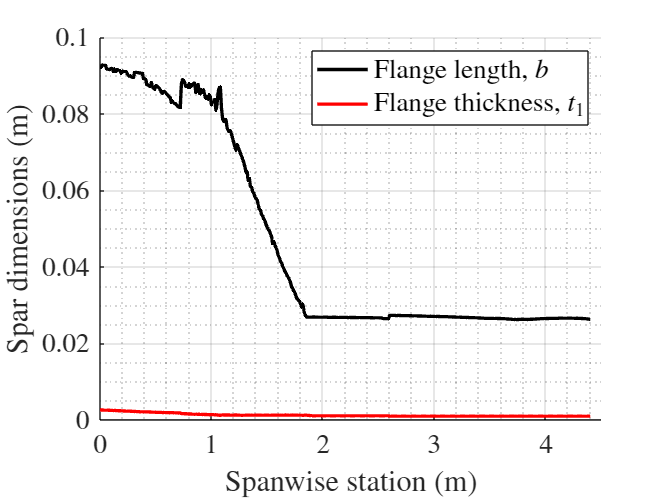



xlabel("Spanwise station (m)", "Interpreter","latex", "FontSize", 16)
ylabel("Spar dimensions (m)", "Interpreter","latex", "FontSize", 16)
plot([-1000 10000], [0 0], "-k", LineWidth=0.5)
grid on
grid minor
set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")
% axis equal

xlim([0 4.5])
legend([p1 p2], "Interpreter","latex", "FontSize", 16)
hold off